# NB-IoT base station SDR

## **Block Diagram:**

- **Transmitter Block Diagram**

- **Receiver Block Diagram**

## Transimitter:

- **Baseband Signal Generation**

- **Upsampling **

- **FIR Filter**

- **Digital Up Conversion**

## Receiver:

- **Digital Down Conversion**

- **FIR Filter**

- **Downsampling **

## 1)Block Diagrams:

- We are using the NB-IoT B1 Band whose Uplink frequency ranges between **1920 - 1980 MHz** .The **RF** at transmitter and receiver is chosen to be **1950 MHz **The bandwidth associated with the B1 band is **60 MHz.**

- **IF **is choosen to be** 900 kHz **such that:

**            IF1 = 200 kHz                                                 IF2 = 400 kHz**

**            IF3 =  600 kHz                                                IF4 = 800 kHz**

**            IF5 =  1000 kHz                                              IF6 = 1200 kHz**

**            IF7 =  1400 kHz                                              IF8 = 1600 kHz**

## Transmitter Block Diagram:

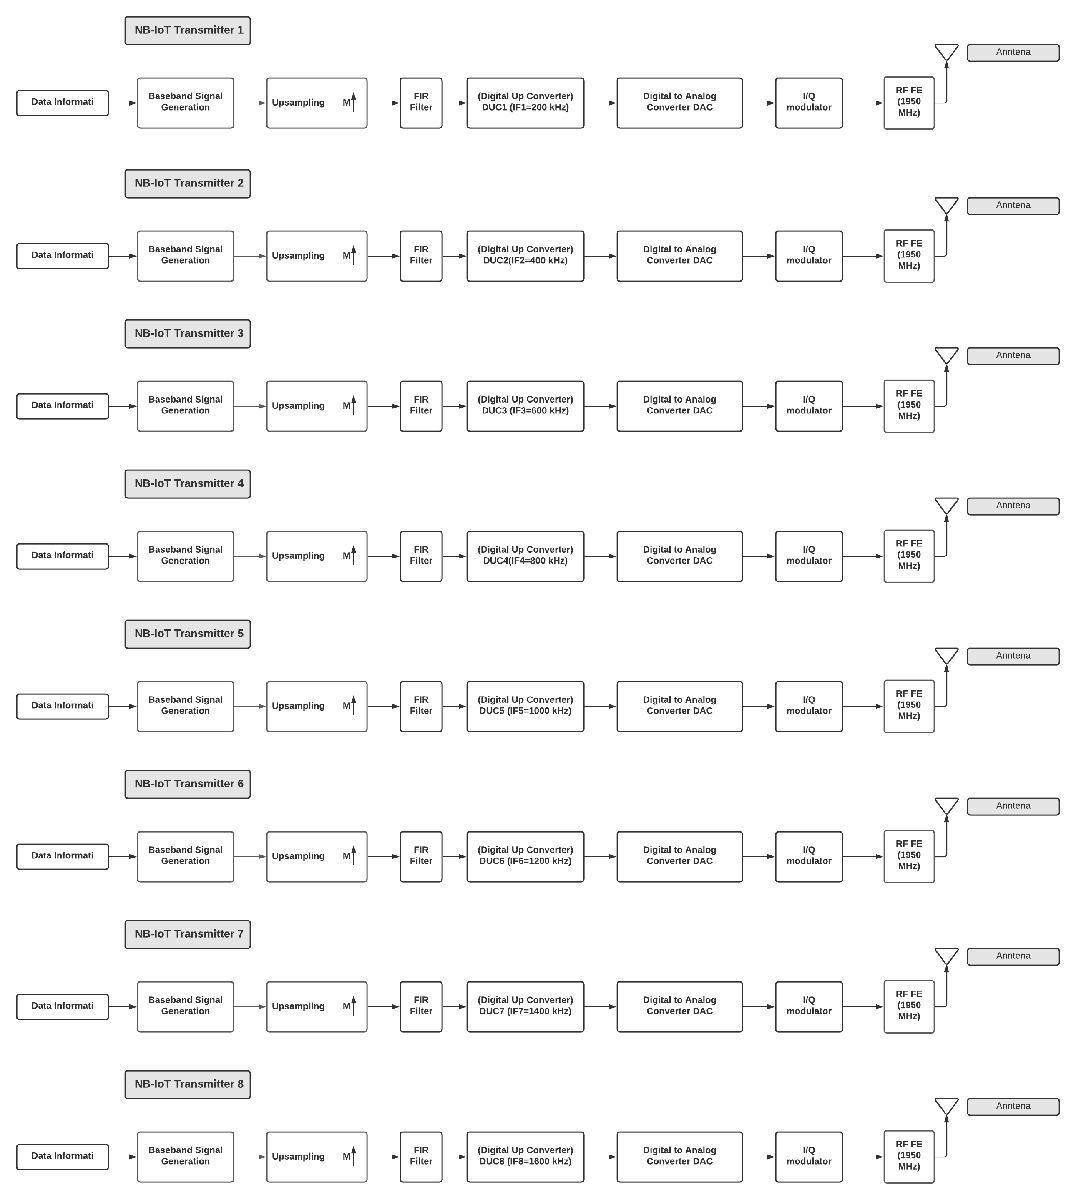

## Receiver Block Diagram:

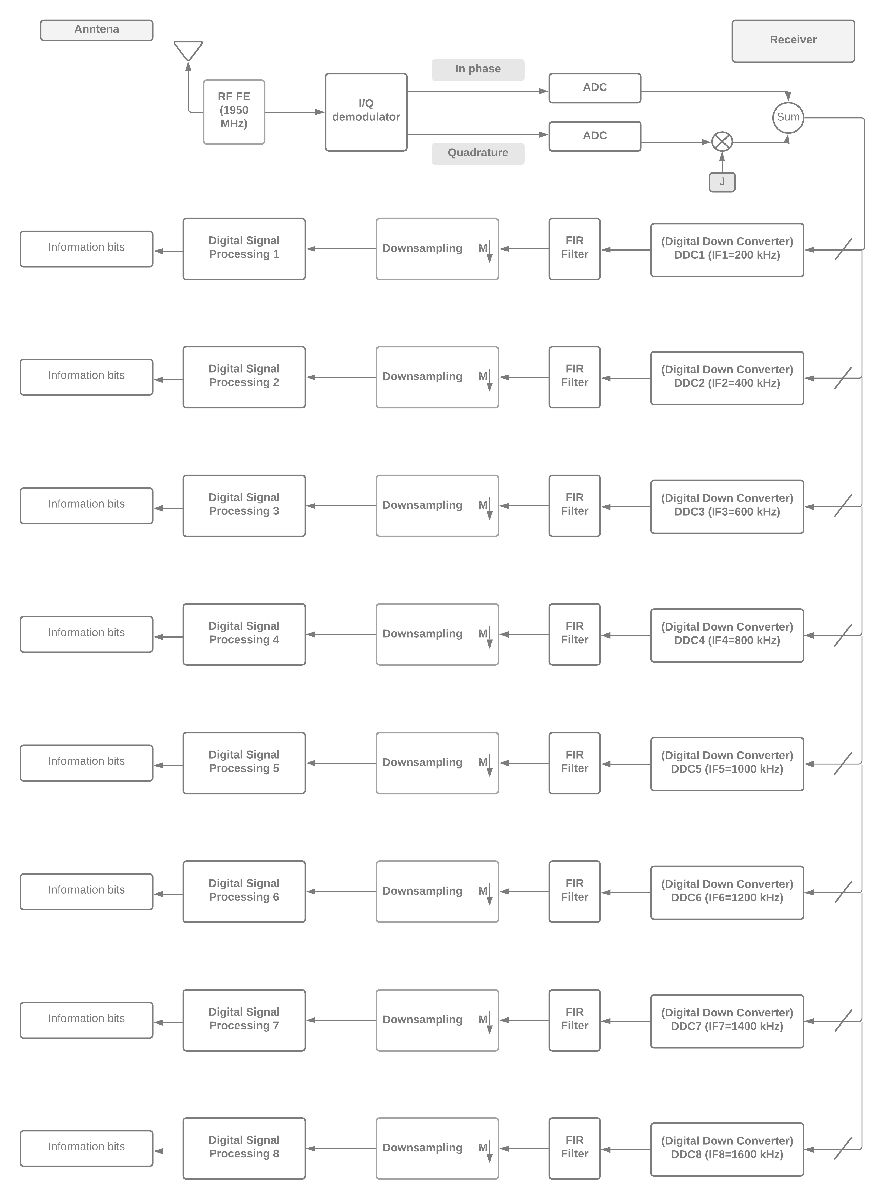

## 2) Transmitter:

## Baseband Signal Generation:

- **Uplink() functions is used to generate the baseband signal.**

- **The generated NB-IoT uplink complex baseband waveform represents the 180 kHz narrowband carrier.**

- **The Sampling Frequency of the Waveform is 1.92 MHz.**

- **Standard reference : **

- [**https://www.gsma.com/iot/wp-content/uploads/2019/07/201906-GSMA-NB-IoT-Deployment-Guide-v3.pdf**](https://www.gsma.com/iot/wp-content/uploads/2019/07/201906-GSMA-NB-IoT-Deployment-Guide-v3.pdf) 

clear;
close all;
clc;

[waveform,fs] = Uplink(); %Generated waveform and its sampling frequency


Generating 128 slots corresponding to 1 transport block(s)


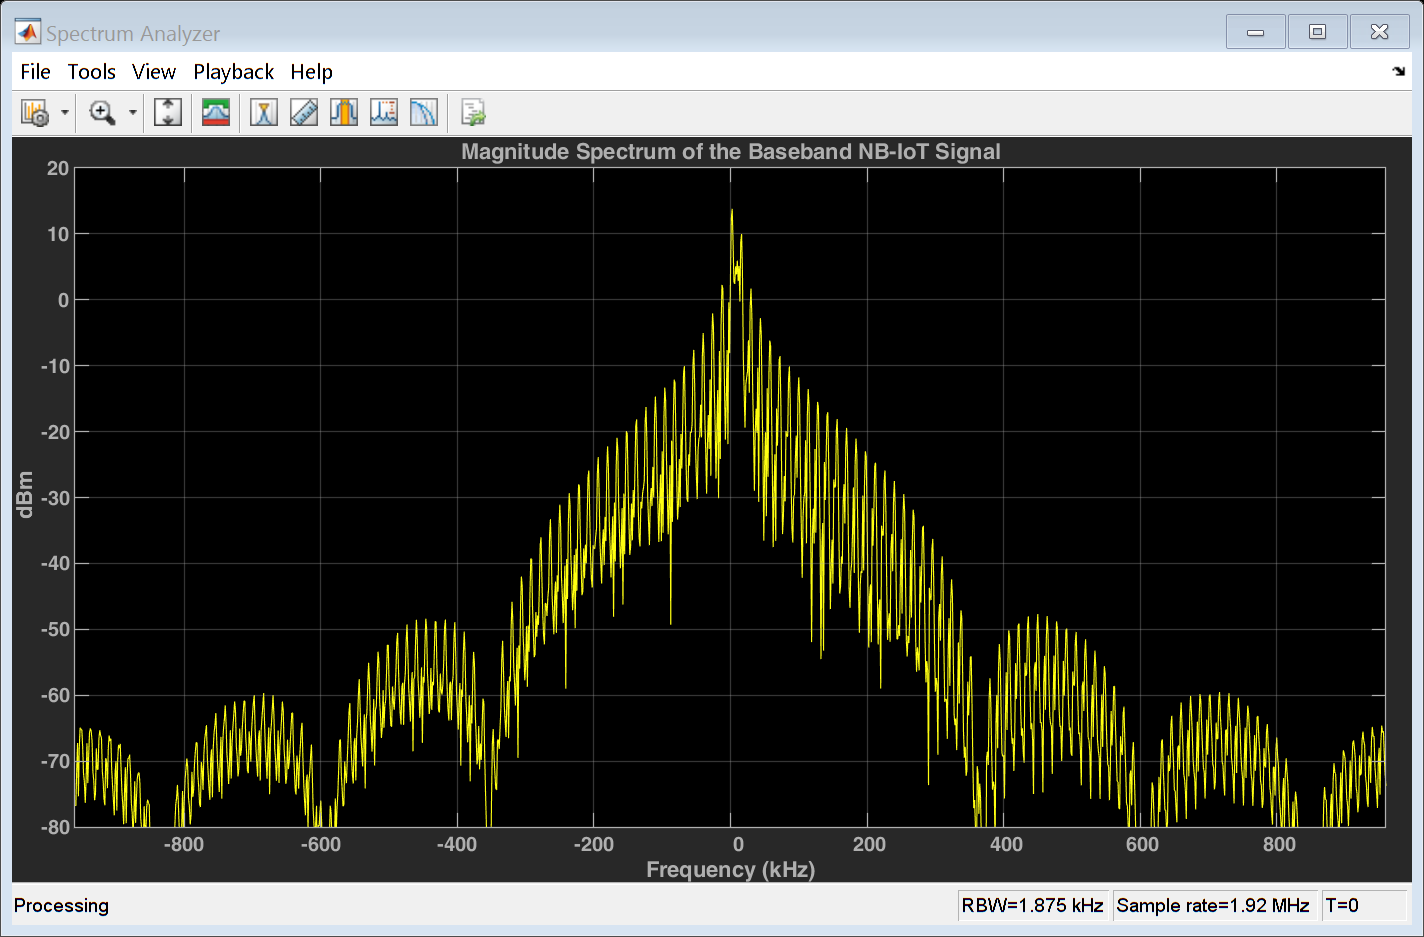

%Plot the magnitude spectrum of the baseband signal 
spectrumAnalyzer = dsp.SpectrumAnalyzer(1); %Define a Spectrum Analyzer object
spectrumAnalyzer.SampleRate = fs;  %Setting the Spectrum Analyzer's Sample Rate with the value of fs 
spectrumAnalyzer(waveform);
spectrumAnalyzer.Title = "Magnitude Spectrum of the Baseband NB-IoT Signal";

## **Upsampling:**

- **The sample rate of the generated NB-IoT uplink complex baseband waveform needs to be increased in order to allow for digital upconversion.**

- **upsample() function is used to increase the sample rate. **

- **upsample() function's inputs are: the waveform, a factor which will by the original sample rate to generate the upsampled rate.**

- **upsample() funciton's output is: the upsampled waveform with the new sample rate.**

- **Since the transmitted signal will contain 8 NB-IoT uplink complex baseband waveform.**

- **Each signal has a bandwidth of 180 kHz. (0 Hz : 180 kHz)**

- **The spacing between each two signals in frequency domain is 20 kHz (suh the space between two signals' center is 200 kHz).**

- **According to the IF frequencies mensioned above, the first signal will be centered at IF =200 kHz, while the last one will be centered at IF = 1600 kHz, as the bandwith for each signal is 180 kHz, then the required (fs/2) should be at least 1690 kHz. **

- **Based on the above calculations, and given the frequency margin of 310 kHz ,the new sample rate will be chosen such that:**

                                                                           
$$\frac{\textrm{fs}}{2}=2\;\textrm{MHz}$$


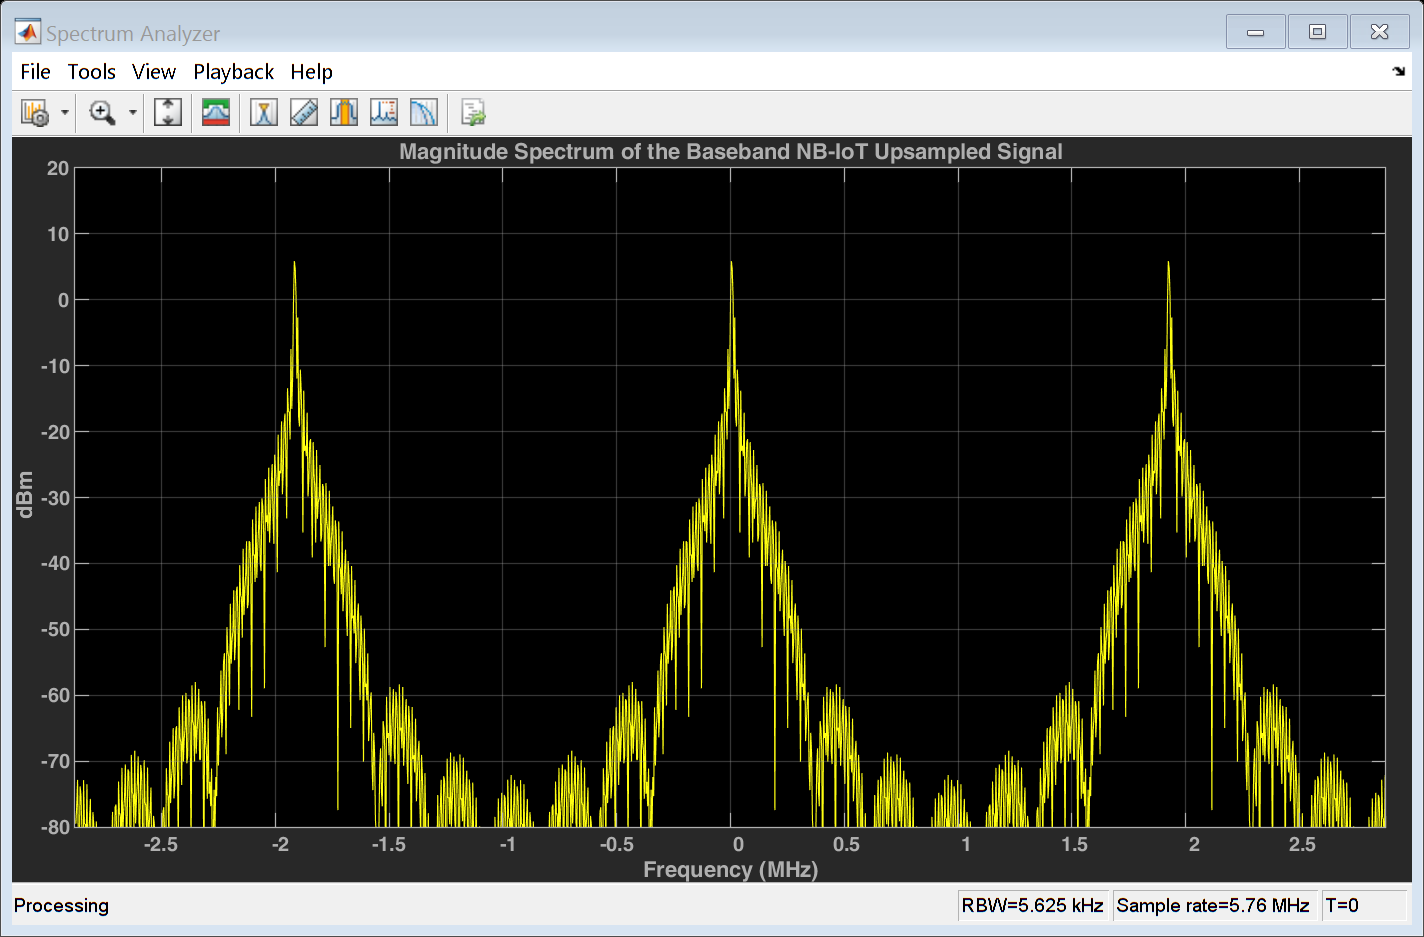

factor_up = ceil(2e6/(fs/2)); %The ratio between the new and original sample rates
waveform_upsampled = upsample(waveform, factor_up); %upsample the NB-IoT waveform
fs = fs * factor_up; %Changing the Sample Rate to the new Upsampled Rate
%Plot the magnitude spectrum of the baseband upsampled signal 
spectrumAnalyzer2 = dsp.SpectrumAnalyzer(1); %Define a Spectrum Analyzer object
spectrumAnalyzer2.SampleRate = fs;  %Setting the Spectrum Analyzer's Sample Rate with the value of fs 
spectrumAnalyzer2(waveform_upsampled);
spectrumAnalyzer2.Title = "Magnitude Spectrum of the Baseband NB-IoT Upsampled Signal";

**Comment: **

As shown above, there are replicas in the singal after the upsampling, and for this reason we apply filter to remove these replicas.

**Problem Statement: **

- **The base station receiver is receiving a main signal which consists of 8 frequency multiplexed signals each of which is transmitted by a different NB-IoT transmitter. We need to design a digital FIR filter that is required to efficiently select one NB-IoT signal out of the 8 received signals. In order to achieve that, the filter needs to have a fast roll off and high stopband attenuation since the spacing between the signals received ,in frequency domain, from the composite IF signal is 20 kHz. Thus to avoid overlapping between adjacent signals, the filter should limit the bandwidth of the signal to approximately 180 kHz at the transmitter and to be able to successfully select the 180 kHz bandwidth-signal without interference resulting from adjacent signals at the receiver. According to the several iterations in designing the filter, the main problems were choosing a filter with fast roll off that maximizes the attenuation of the stopband, while using the smallest possible number of taps. Moreover, we found that choosing a sampling frequency close to the operating frequency (4 - 5 MHz) makes the filter’s cutoff frequency almost the required one. We also iterate to find the filter which has the fastest roll off and high stopband attenuation. **

**The filters we iterate on:**

- **Equiripple filter.**

- **Least square filter**

## **FIR Filter**:

- **As shown in the Magnitude Spectrum of the Baseband NB-IoT Signal, the waveform has frequency components from -800 kHz to 800 kHz. **

- **But the important frequencies exist in the range from -90 kHz to 90 kHz.**

- **So, FIR Filter is needed to pass the important frequencies, while attenuating the unwanted frequencies.**

- **Here are the specifications and constraints of the digital FIR filter to be designed:**

**                   1) Passband ripples: **peak-to-peak passband ripple = 2 dB  

**                   2) Stopband attenuation:** -60 dB

**                   3) Transition region width: **$f_s -f_p =100\;\textrm{kHz}-90\;\textrm{kHz}=20\;\textrm{kHz}\;$

**                   4) Max Number of filter taps: **512 taps   

### **Iteration 1:**

- **We started the iterations of designing FIR Filter by using following filter specifications.**

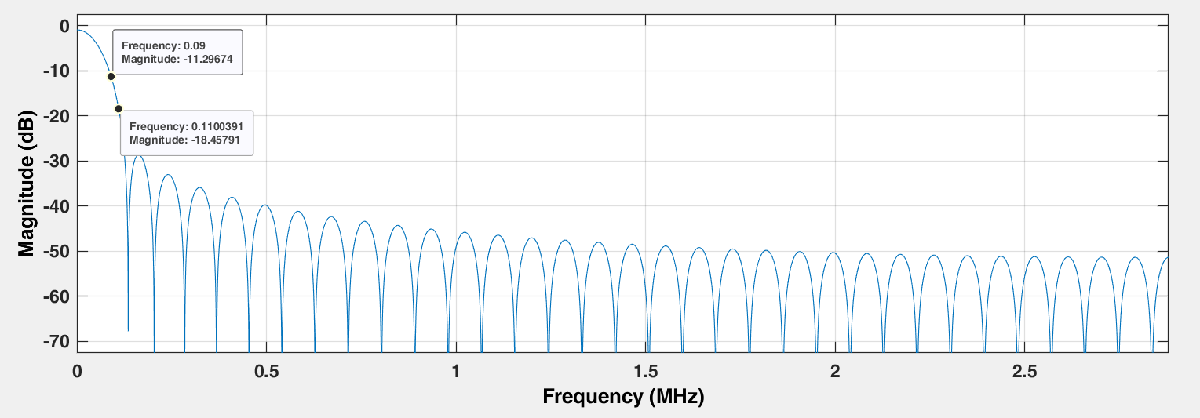

- **The above FIR filter is a Least-squares filter with**

**                 1) Number of taps (order) = 64 **

**                 2) Fs = 5.76 MHz**

**                 3) Fpass = 90 kHz**

**                 4) Fstop = 110 kHz**

- **As shown in the above figure, the designed filter doesn't meet the required specifications.**

- **Neither Passband ripples, nor Stopband attenuation met the desired specifications.**

- **So, we will show the its results and try other higher order filters in the next iterations.**

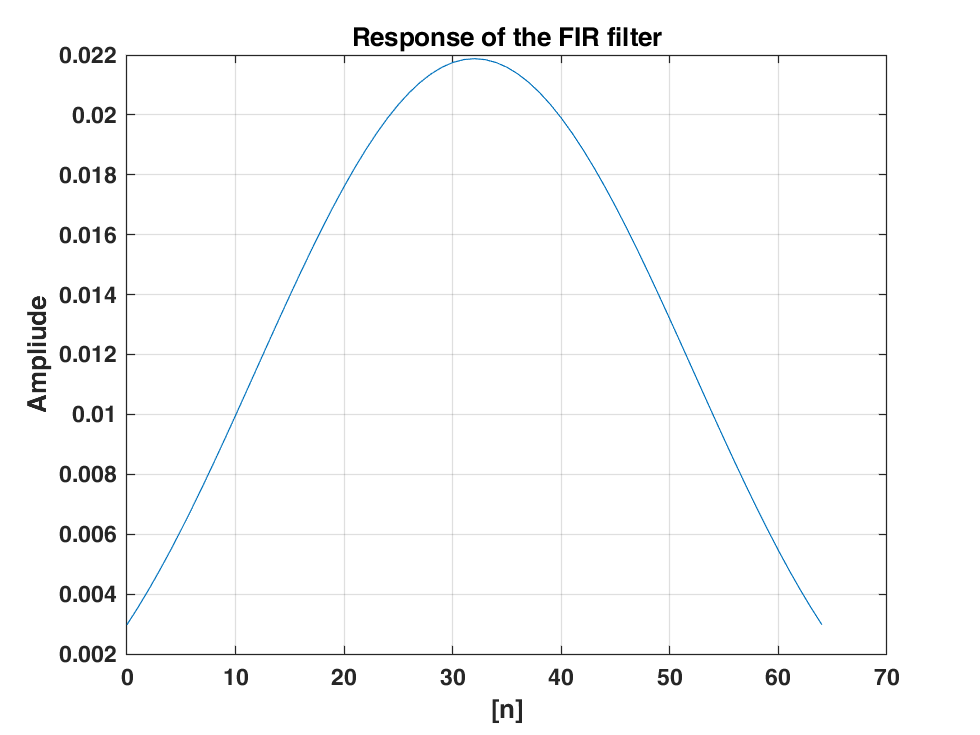

%the magnitude response of the filter
%I = imread('1_LS64_1.PNG');
%imshow(I);
%64 taps Least-squares FIR Filter
filter1 = [0.00298019354510829	0.00354811486891884	0.00415164177867865	0.00478888207041565	0.00545761195333393	0.00615528613134859	0.00687905110655252	0.00762576162472069	0.00839200014923683	0.00917409921698032	0.00996816649810932	0.0107701123516815	0.0115756796410106	0.0123804755468923	0.0131800050936440	0.0139697060825715	0.0147449851102364	0.0155012543349652	0.0162339686445918	0.0169386628715838	0.0176109886985766	0.0182467508979717	0.0188419425536661	0.0193927789211274	0.0198957295938533	0.0203475486596257	0.0207453025487471	0.0210863952984232	0.0213685909824134	0.0215900330827346	0.0217492606102842	0.0218452208134233	0.0218772783474788	0.0218452208134233	0.0217492606102842	0.0215900330827346	0.0213685909824134	0.0210863952984232	0.0207453025487471	0.0203475486596257	0.0198957295938533	0.0193927789211274	0.0188419425536661	0.0182467508979717	0.0176109886985766	0.0169386628715838	0.0162339686445918	0.0155012543349652	0.0147449851102364	0.0139697060825715	0.0131800050936440	0.0123804755468923	0.0115756796410106	0.0107701123516815	0.00996816649810932	0.00917409921698032	0.00839200014923683	0.00762576162472069	0.00687905110655252	0.00615528613134859	0.00545761195333393	0.00478888207041565	0.00415164177867865	0.00354811486891884	0.00298019354510829];
filtered_signal_1 = filter(filter1, 1, waveform_upsampled);
%Plot the Response of the FIR filter
figure();
plot((0:length(filter1) - 1), filter1);
grid on; title('Response of the FIR filter'); xlabel('[n]'); ylabel('Ampliude');

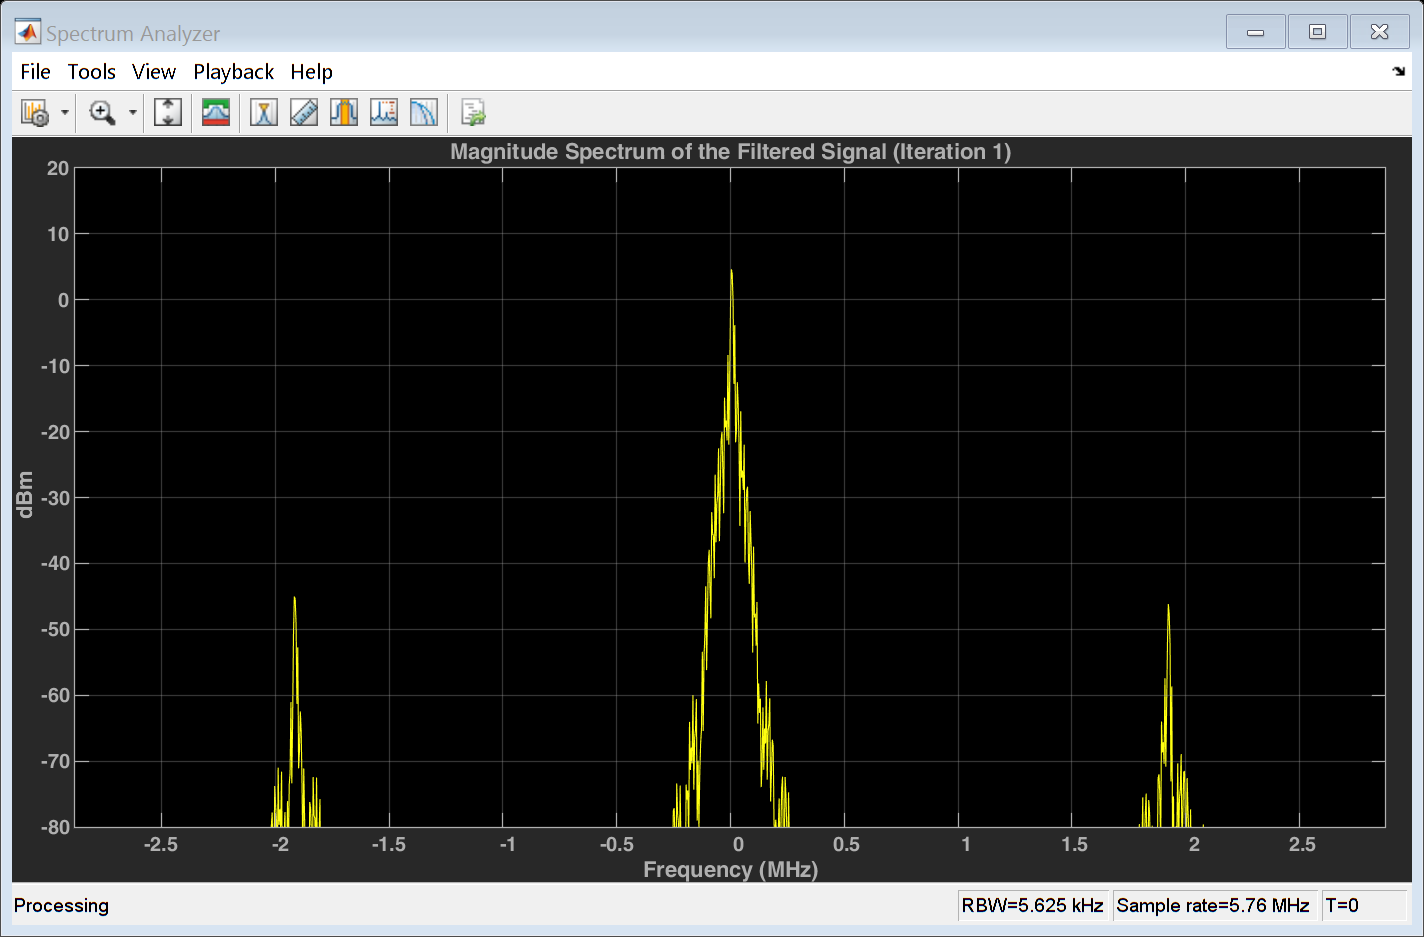


%Plot the magnitude spectrum of the baseband upsampled signal 
spectrumAnalyzer3 = dsp.SpectrumAnalyzer(1); %Define a Spectrum Analyzer object
spectrumAnalyzer3.SampleRate = fs;  %Setting the Spectrum Analyzer's Sample Rate with the value of fs
spectrumAnalyzer3(filtered_signal_1);
spectrumAnalyzer3.Title = "Magnitude Spectrum of the Filtered Signal (Iteration 1)";

### **Iteration 2:**

- **In this iteration, we tried to increase the filter order and we designed a FIR Filter with using the following filter specifications.**

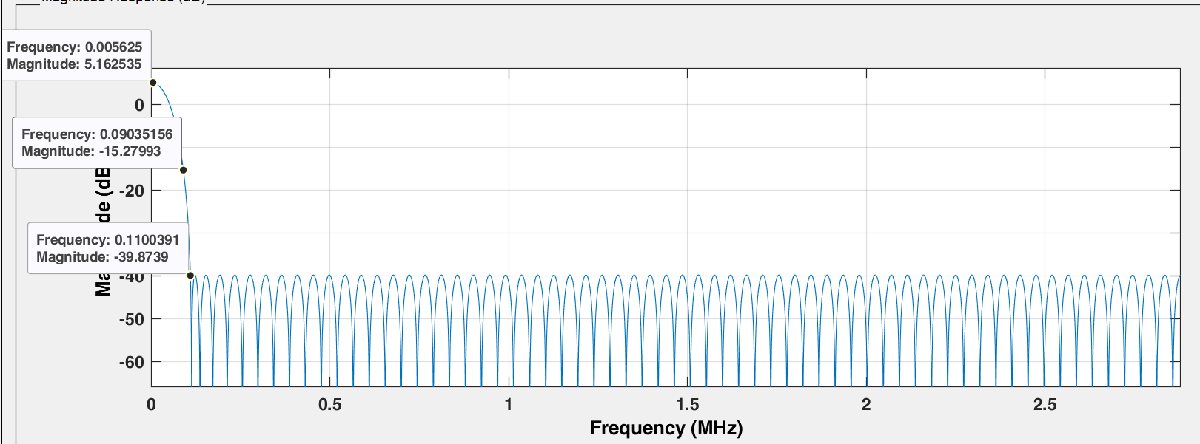

- **The above FIR filter is an Equiripple filter with**

**                 1) Number of taps (order) = 128 **

**                 2) Fs = 5.76 MHz**

**                 3) Fpass = 90 kHz**

**                 4) Fstop = 110 kHz**

- **As shown in the above figure, the designed filter is better that the 64 taps filter, but it still doesn't meet the required specifications. **

- **So, we will show the its results and try other higher order filters in the next iterations.**

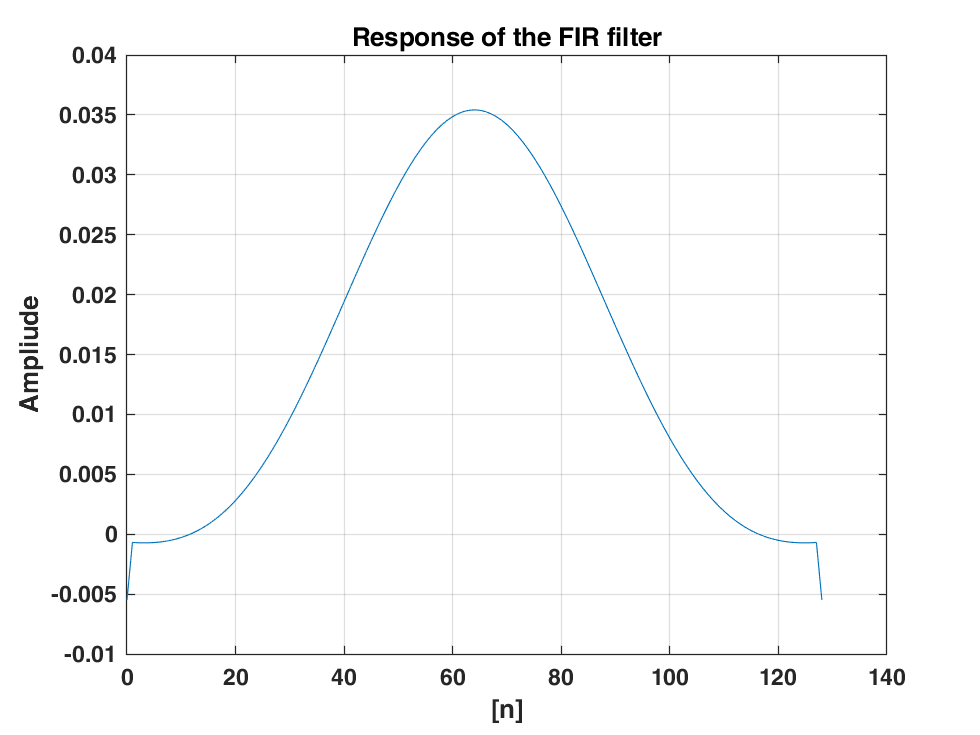

%128 taps Equiripple FIR Filter
filter2 = [-0.00548170094508931	-0.000689569998293808	-0.000713472735461343	-0.000723902679216727	-0.000719107470126321	-0.000697527609803669	-0.000657235024123514	-0.000596513288584351	-0.000513382909122462	-0.000406194167914136	-0.000273078813846359	-0.000112484440103975	7.73589401488574e-05	0.000298002329314556	0.000551167117423887	0.000838157507332248	0.00116032143646611	0.00151863156693067	0.00191423922024803	0.00234794513703522	0.00282059179913615	0.00333228943909635	0.00388338210285986	0.00447388699128530	0.00510404712756167	0.00577266133401547	0.00647946222287595	0.00722390998654680	0.00800397976698280	0.00881902302033127	0.00966684705708275	0.0105457848860377	0.0114535708402100	0.0123878813963994	0.0133460309574389	0.0143251546335249	0.0153222251418163	0.0163339667177296	0.0173569540698017	0.0183875598084071	0.0194220693123469	0.0204566027032113	0.0214872436653690	0.0225099072447629	0.0235204889686213	0.0245148819234827	0.0254890040425417	0.0264386424177773	0.0273597349591630	0.0282482731409498	0.0291004424729017	0.0299121436206533	0.0306800739788068	0.0314004766967544	0.0320700915410413	0.0326859201185808	0.0332449632036708	0.0337446706914530	0.0341826631991373	0.0345568997797736	0.0348655594273392	0.0351071724157148	0.0352806068526275	0.0353849904976164	0.0354198468703562	0.0353849904976164	0.0352806068526275	0.0351071724157148	0.0348655594273392	0.0345568997797736	0.0341826631991373	0.0337446706914530	0.0332449632036708	0.0326859201185808	0.0320700915410413	0.0314004766967544	0.0306800739788068	0.0299121436206533	0.0291004424729017	0.0282482731409498	0.0273597349591630	0.0264386424177773	0.0254890040425417	0.0245148819234827	0.0235204889686213	0.0225099072447629	0.0214872436653690	0.0204566027032113	0.0194220693123469	0.0183875598084071	0.0173569540698017	0.0163339667177296	0.0153222251418163	0.0143251546335249	0.0133460309574389	0.0123878813963994	0.0114535708402100	0.0105457848860377	0.00966684705708275	0.00881902302033127	0.00800397976698280	0.00722390998654680	0.00647946222287595	0.00577266133401547	0.00510404712756167	0.00447388699128530	0.00388338210285986	0.00333228943909635	0.00282059179913615	0.00234794513703522	0.00191423922024803	0.00151863156693067	0.00116032143646611	0.000838157507332248	0.000551167117423887	0.000298002329314556	7.73589401488574e-05	-0.000112484440103975	-0.000273078813846359	-0.000406194167914136	-0.000513382909122462	-0.000596513288584351	-0.000657235024123514	-0.000697527609803669	-0.000719107470126321	-0.000723902679216727	-0.000713472735461343	-0.000689569998293808	-0.00548170094508931];
filtered_signal_2 = filter(filter2, 1, waveform_upsampled);
%Plot the Response of the FIR filter
figure();
plot((0:length(filter2) - 1), filter2);
grid on; title('Response of the FIR filter'); xlabel('[n]'); ylabel('Ampliude');

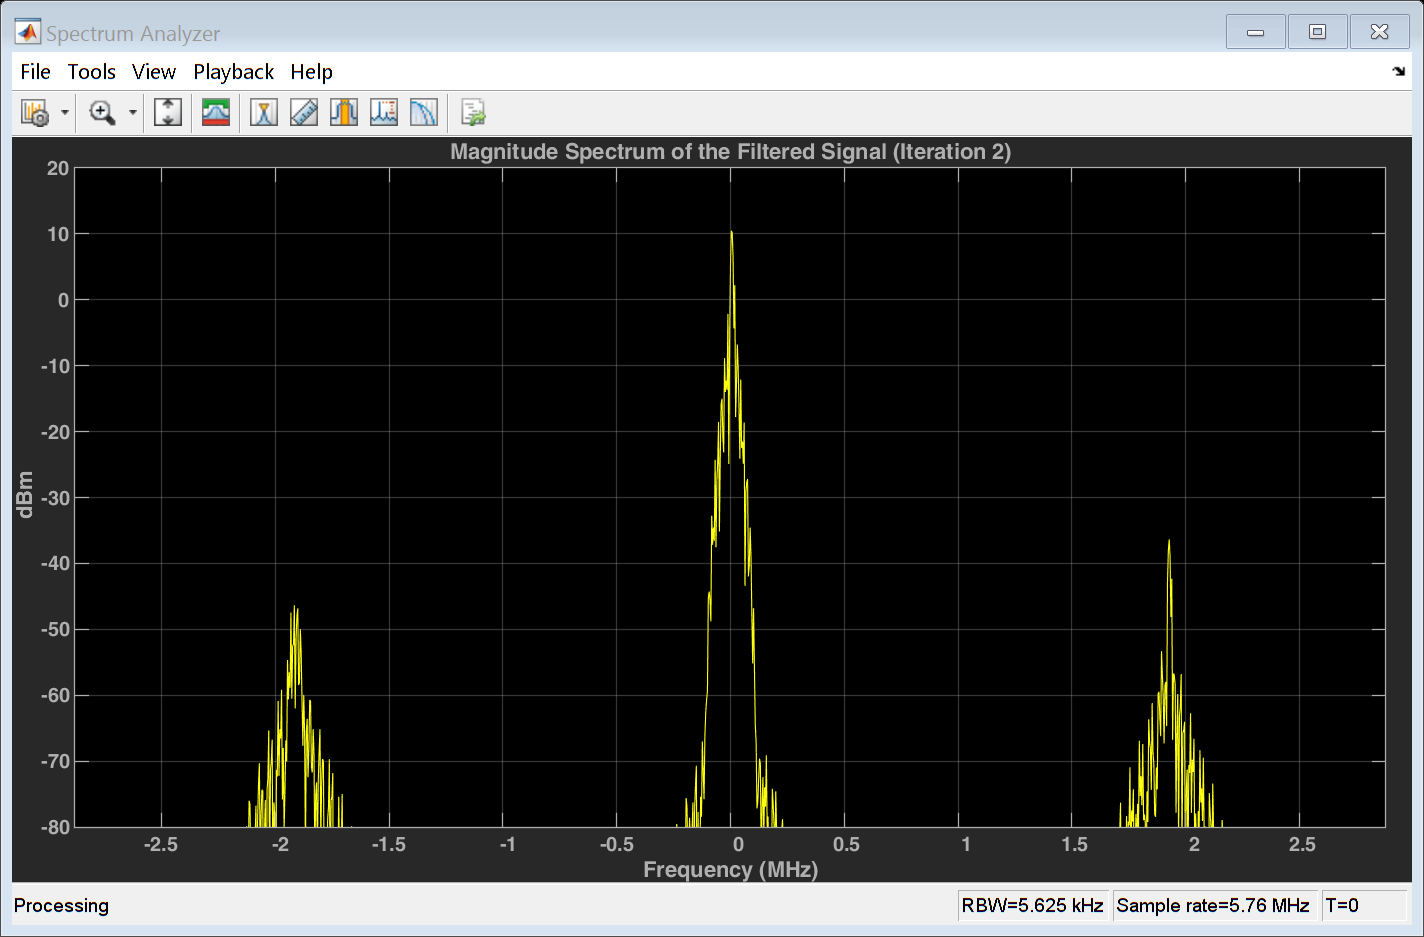


%Plot the magnitude spectrum of the baseband upsampled signal 
spectrumAnalyzer4 = dsp.SpectrumAnalyzer(1); %Define a Spectrum Analyzer object
spectrumAnalyzer4.SampleRate = fs;  %Setting the Spectrum Analyzer's Sample Rate with the value of fs
spectrumAnalyzer4(filtered_signal_2);
spectrumAnalyzer4.Title = "Magnitude Spectrum of the Filtered Signal (Iteration 2)";

### **Iteration 3:**

- **In this iteration, we tried to increase the filter order and we designed a FIR Filter with using the following filter specifications.**

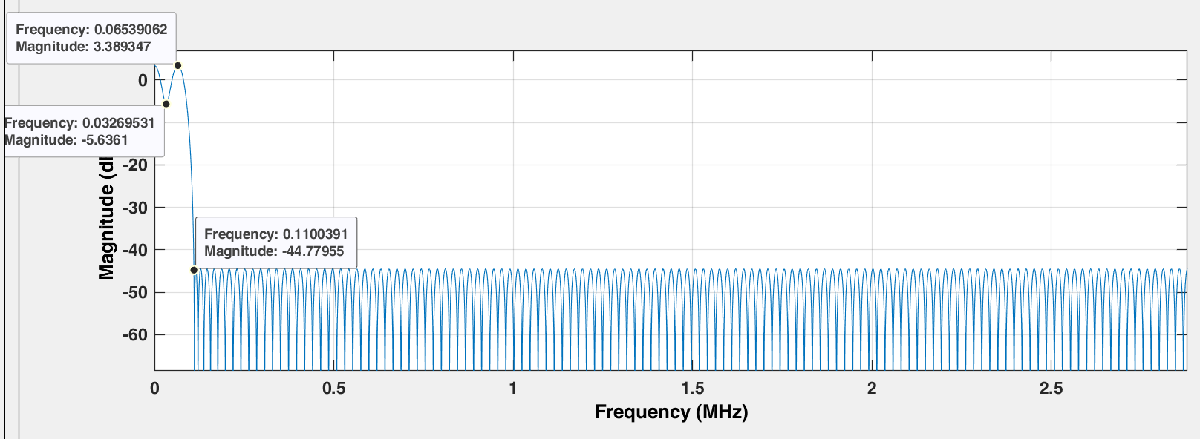

- **The above FIR filter is an Equiripple filter with**

**                 1) Number of taps (order) = 256**

**                 2) Fs = 5.76 MHz**

**                 3) Fpass = 90 kHz**

**                 4) Fstop = 110 kHz**

- **As shown in the above figure, the designed filter is better that the 128 taps filter, but it still doesn't meet the required specifications as the Passband ripples are more than 2 dB peak to peak**

- **So, we will show the its results and try other higher order filters in the next iterations.**

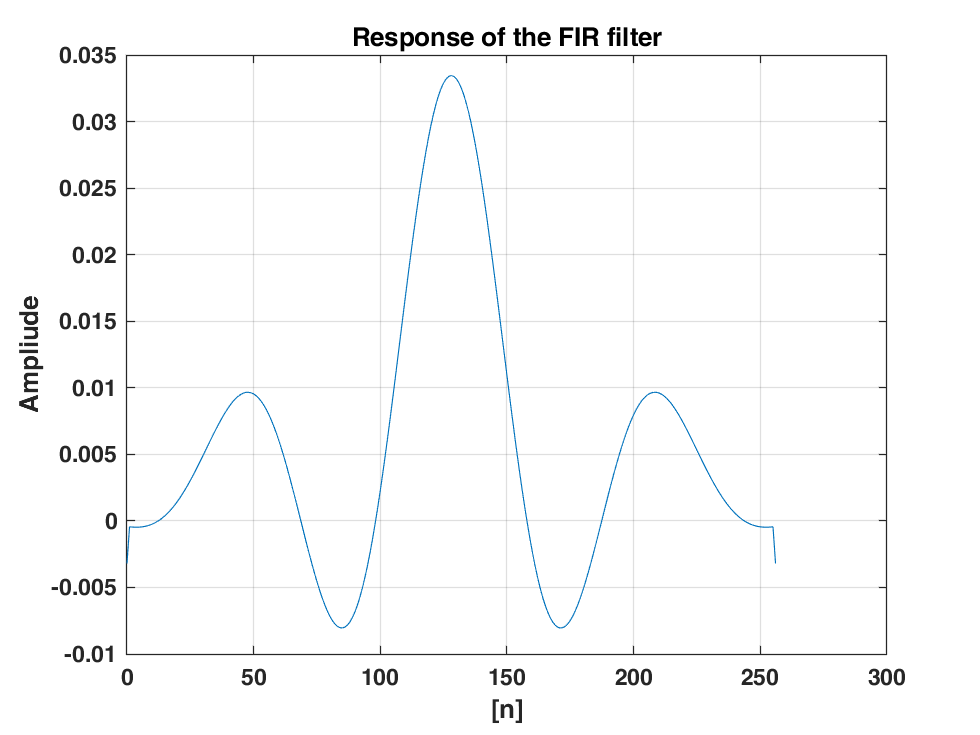

%256 taps Equiripple FIR Filter
filter3 = [-0.00319962219952323	-0.000443285704140751	-0.000462252405877226	-0.000473243429566926	-0.000475179601612692	-0.000466997234911181	-0.000447622465491930	-0.000416008402310154	-0.000371103843129539	-0.000311921105744737	-0.000237497722018477	-0.000146951205548792	-3.94676150928034e-05	8.56476045593684e-05	0.000229011269998357	0.000391096336118792	0.000572264183163034	0.000772717107213135	0.000992525603435333	0.00123155679948361	0.00148952292050742	0.00176593853079182	0.00206015391492239	0.00237129296546117	0.00269830672476443	0.00303992139306171	0.00339468294097963	0.00376091669144257	0.00413679364602047	0.00452027000478288	0.00490913521929967	0.00530097983090296	0.00569328141311650	0.00608336003091732	0.00646843804218111	0.00684559012555630	0.00721183070304139	0.00756409579787643	0.00789933328410743	0.00821443002832191	0.00850629230629216	0.00877184771401653	0.00900816588957162	0.00921235801331851	0.00938166076692091	0.00951345173114909	0.00960538053005010	0.00965521490127863	0.00966096494936975	0.00962095862235846	0.00953382278953705	0.00939837605954299	0.00921395040994826	0.00898008962950456	0.00869678204026933	0.00836437722569207	0.00798363322508842	0.00755572258471261	0.00708218543860435	0.00656503765269677	0.00600667057131081	0.00540988056531837	0.00477787962207181	0.00411427276622669	0.00342301607338048	0.00270841878637067	0.00197514846660049	0.00122816216348896	0.000472684947911238	-0.000285818010042231	-0.00104164314027271	-0.00178893899867446	-0.00252172011729929	-0.00323392831216684	-0.00391943298953191	-0.00457212829802433	-0.00518594105330085	-0.00575492337123174	-0.00627324070204305	-0.00673526856837935	-0.00713559166185310	-0.00746912469171344	-0.00773108196787951	-0.00791707682828193	-0.00802310003059889	-0.00804565465831494	-0.00798169443689348	-0.00782873655532365	-0.00758480472772989	-0.00724856684225440	-0.00681922553369774	-0.00629666681799458	-0.00568135301835227	-0.00497447419717397	-0.00417776467360721	-0.00329371407310991	-0.00232535064484188	-0.00127645851139273	-0.000151262365004648	0.00104518849444967	0.00230760339735646	0.00362969671927714	0.00500533572457314	0.00642713303933614	0.00788790740462110	0.00938005692478492	0.0108950552169299	0.0124248541382925	0.0139608936552678	0.0154944086906517	0.0170164486649940	0.0185183210005447	0.0199912251799605	0.0214264568214132	0.0228153313510062	0.0241495352766626	0.0254209847474456	0.0266220126706898	0.0277452249793768	0.0287837257620546	0.0297310455535167	0.0305813585934357	0.0313293592296993	0.0319704184568648	0.0325004829683922	0.0329162544662908	0.0332150853016798	0.0333951375480554	0.0334552662953727	0.0333951375480554	0.0332150853016798	0.0329162544662908	0.0325004829683922	0.0319704184568648	0.0313293592296993	0.0305813585934357	0.0297310455535167	0.0287837257620546	0.0277452249793768	0.0266220126706898	0.0254209847474456	0.0241495352766626	0.0228153313510062	0.0214264568214132	0.0199912251799605	0.0185183210005447	0.0170164486649940	0.0154944086906517	0.0139608936552678	0.0124248541382925	0.0108950552169299	0.00938005692478492	0.00788790740462110	0.00642713303933614	0.00500533572457314	0.00362969671927714	0.00230760339735646	0.00104518849444967	-0.000151262365004648	-0.00127645851139273	-0.00232535064484188	-0.00329371407310991	-0.00417776467360721	-0.00497447419717397	-0.00568135301835227	-0.00629666681799458	-0.00681922553369774	-0.00724856684225440	-0.00758480472772989	-0.00782873655532365	-0.00798169443689348	-0.00804565465831494	-0.00802310003059889	-0.00791707682828193	-0.00773108196787951	-0.00746912469171344	-0.00713559166185310	-0.00673526856837935	-0.00627324070204305	-0.00575492337123174	-0.00518594105330085	-0.00457212829802433	-0.00391943298953191	-0.00323392831216684	-0.00252172011729929	-0.00178893899867446	-0.00104164314027271	-0.000285818010042231	0.000472684947911238	0.00122816216348896	0.00197514846660049	0.00270841878637067	0.00342301607338048	0.00411427276622669	0.00477787962207181	0.00540988056531837	0.00600667057131081	0.00656503765269677	0.00708218543860435	0.00755572258471261	0.00798363322508842	0.00836437722569207	0.00869678204026933	0.00898008962950456	0.00921395040994826	0.00939837605954299	0.00953382278953705	0.00962095862235846	0.00966096494936975	0.00965521490127863	0.00960538053005010	0.00951345173114909	0.00938166076692091	0.00921235801331851	0.00900816588957162	0.00877184771401653	0.00850629230629216	0.00821443002832191	0.00789933328410743	0.00756409579787643	0.00721183070304139	0.00684559012555630	0.00646843804218111	0.00608336003091732	0.00569328141311650	0.00530097983090296	0.00490913521929967	0.00452027000478288	0.00413679364602047	0.00376091669144257	0.00339468294097963	0.00303992139306171	0.00269830672476443	0.00237129296546117	0.00206015391492239	0.00176593853079182	0.00148952292050742	0.00123155679948361	0.000992525603435333	0.000772717107213135	0.000572264183163034	0.000391096336118792	0.000229011269998357	8.56476045593684e-05	-3.94676150928034e-05	-0.000146951205548792	-0.000237497722018477	-0.000311921105744737	-0.000371103843129539	-0.000416008402310154	-0.000447622465491930	-0.000466997234911181	-0.000475179601612692	-0.000473243429566926	-0.000462252405877226	-0.000443285704140751	-0.00319962219952323];
filtered_signal_3 = filter(filter3, 1, waveform_upsampled);
%Plot the Response of the FIR filter
figure();
plot((0:length(filter3) - 1), filter3);
grid on; title('Response of the FIR filter'); xlabel('[n]'); ylabel('Ampliude');

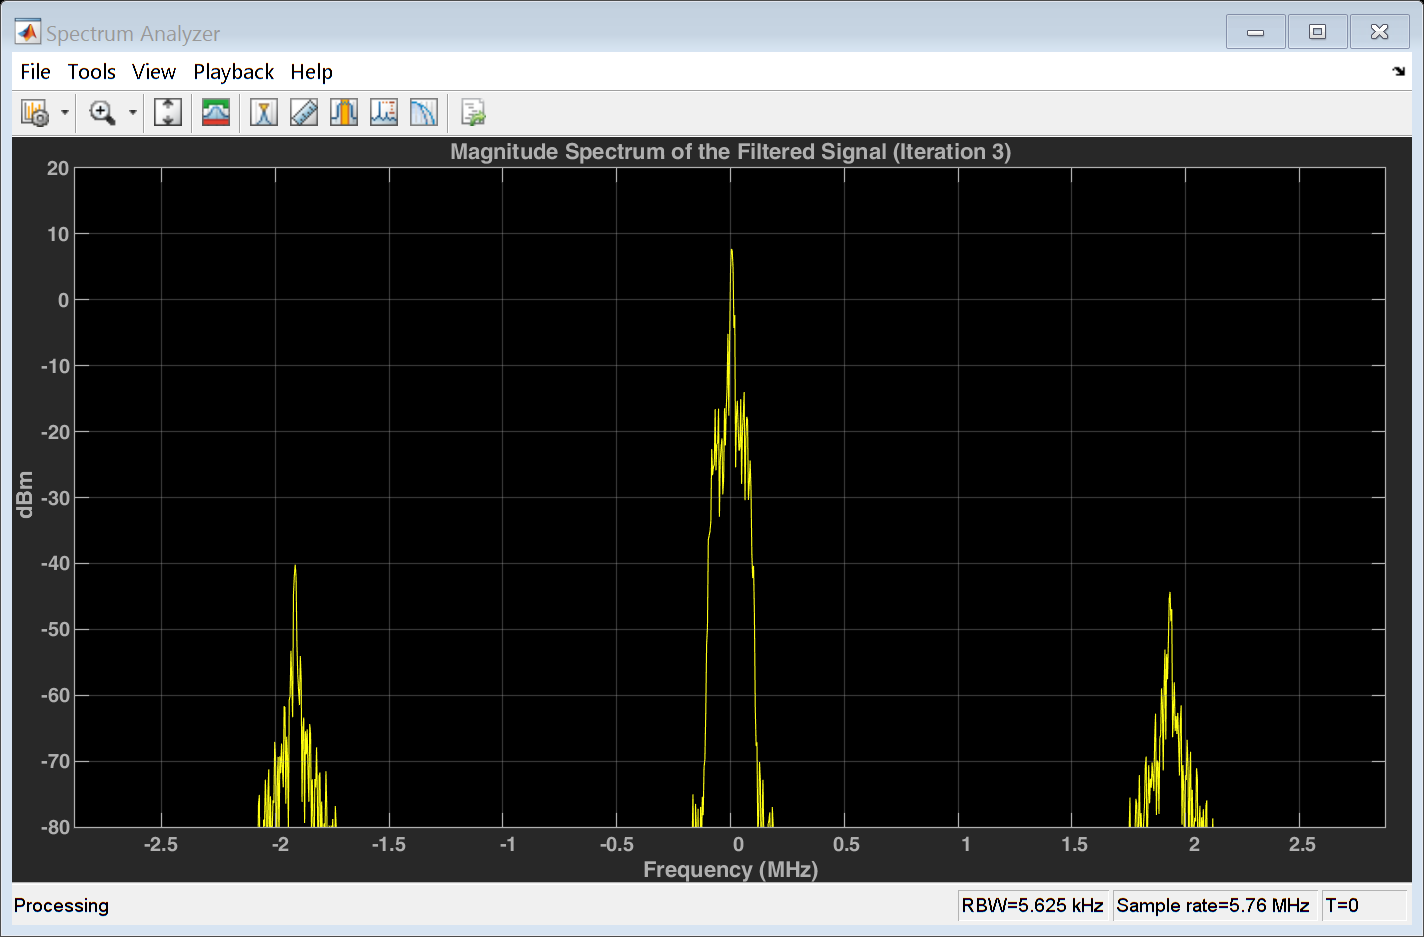


%Plot the magnitude spectrum of the baseband upsampled signal 
spectrumAnalyzer5 = dsp.SpectrumAnalyzer(1); %Define a Spectrum Analyzer object
spectrumAnalyzer5.SampleRate = fs;  %Setting the Spectrum Analyzer's Sample Rate with the value of fs
spectrumAnalyzer5(filtered_signal_3);
spectrumAnalyzer5.Title = "Magnitude Spectrum of the Filtered Signal (Iteration 3)";

### **Iteration 4:**

- **In this iteration, we tried to use another 256 taps filter and we designed a FIR Filter with using the following filter specifications.**

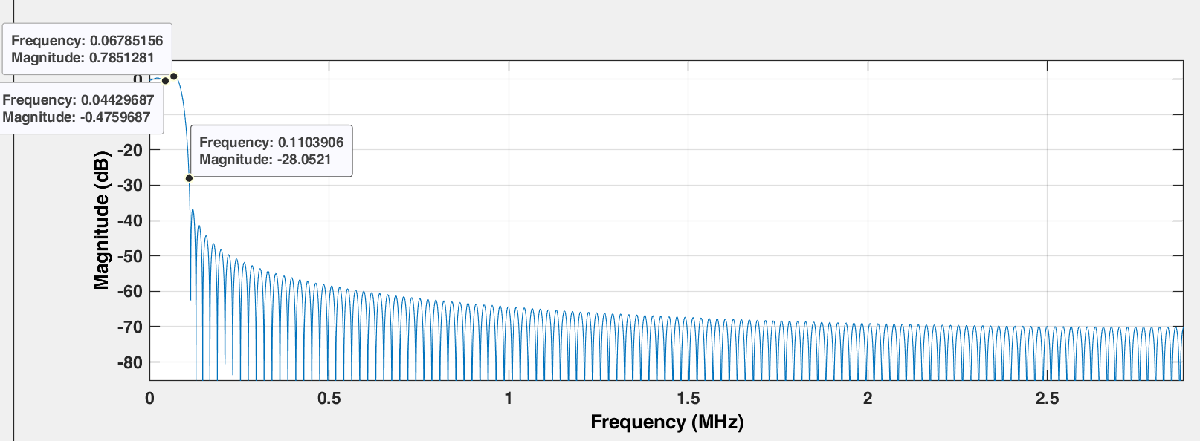

- **The above FIR filter is a Least-squares filter with**

**                 1) Number of taps (order) = 256**

**                 2) Fs = 5.76 MHz**

**                 3) Fpass = 90 kHz**

**                 4) Fstop = 110 kHz**

- **As shown in the above figure, the designed filter is better that the 256 taps Equiripple filter and it can be used and perfom well, but it still doesn't meet the best required specifications as the Stopband attenuation starts at -28 dB.**

- **So, we will show the its results and try other higher order filters in the next iterations.**

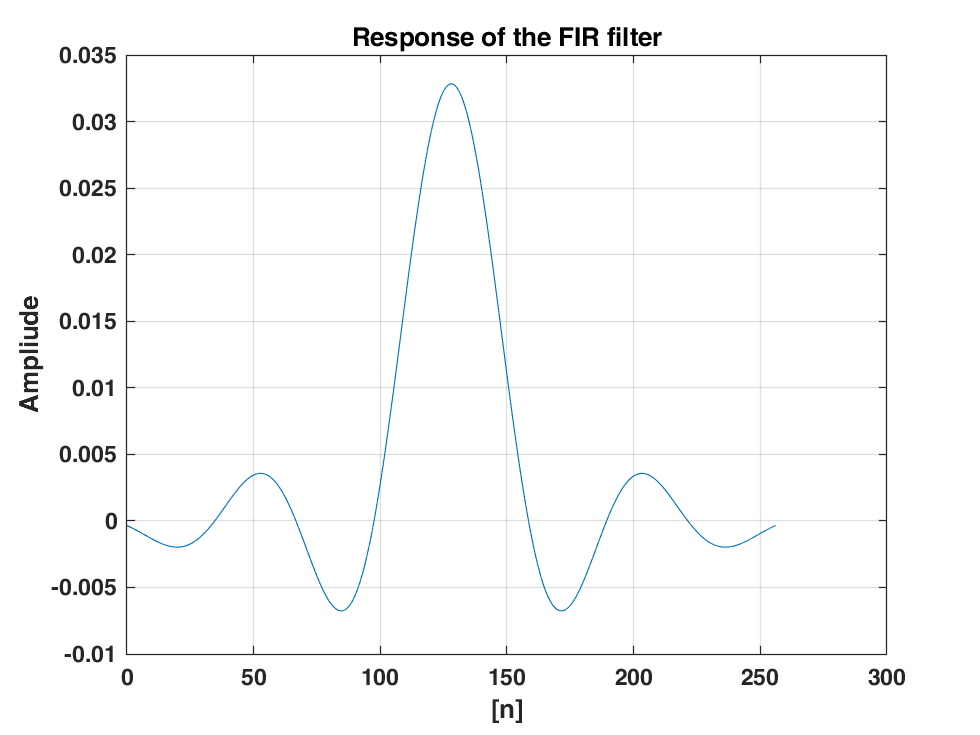

%256 taps Least-squares FIR Filter
filter4 = [-0.000353251714019549	-0.000440195366818573	-0.000532658926319457	-0.000629971560066153	-0.000731355553306510	-0.000835930052114370	-0.000942716301467221	-0.00105064437822884	-0.00115856140023694	-0.00126524117352298	-0.00136939522032085	-0.00146968511118586	-0.00156473600548745	-0.00165315128599925	-0.00173352815553510	-0.00180447404680780	-0.00186462368115684	-0.00191265659772659	-0.00194731496229450	-0.00196742145444900	-0.00197189702338237	-0.00195977829635853	-0.00193023442007908	-0.00188258311381920	-0.00181630571442731	-0.00173106099713878	-0.00162669756267551	-0.00150326459028904	-0.00136102076822385	-0.00120044122746474	-0.00102222232149258	-0.000827284113977855	-0.000616770457734179	-0.000392046571645037	-0.000154694047451814	9.34967549933146e-05	0.000350536937415136	0.000614251902170304	0.000882296755434283	0.00115217419926151	0.00142125480720655	0.00168679954845147	0.00194598439629749	0.00219592682879302	0.00243371400252625	0.00265643235554374	0.00286119837228833	0.00304519022268814	0.00320567996936067	0.00334006602158646	0.00344590550249408	0.00352094618699032	0.00356315766254221	0.00357076136311141	0.00354225912845922	0.00347645994674543	0.00337250454785940	0.00322988752822718	0.00304847670487328	0.00282852941717518	0.00257070551888722	0.00227607683044025	0.00194613285201839	0.00158278257120911	0.00118835223481684	0.000765578992391697	0.000317600358789926	-0.000152060515737131	-0.000639513737243867	-0.00114052564813888	-0.00165054577924530	-0.00216473761496101	-0.00267801297080400	-0.00318506974205185	-0.00368043274328382	-0.00415849732184585	-0.00461357539400457	-0.00503994352123676	-0.00543189261609116	-0.00578377884270494	-0.00609007525667018	-0.00634542371279850	-0.00654468655765931	-0.00668299761675478	-0.00675581198398651	-0.00675895412375537	-0.00668866380366122	-0.00654163938832155	-0.00631507804224816	-0.00600671241189385	-0.00561484338374274	-0.00513836854645362	-0.00457680602031229	-0.00393031335629805	-0.00319970124956824	-0.00238644185772288	-0.00149267156240011	-0.000521188063113747	0.000524558255709114	0.00164047869030956	0.00282186626774059	0.00406342137852602	0.00535928283622404	0.00670306415569158	0.00808789479075952	0.00950646602297488	0.0109510811465543	0.0124137095512082	0.0138860442644959	0.0153595624792860	0.0168255885601063	0.0182753589950287	0.0197000887375369	0.0210910383658290	0.0224395814754077	0.0237372717147532	0.0249759088734532	0.0261476034373997	0.0272448390365457	0.0282605322271448	0.0291880890722455	0.0300214580112758	0.0307551785415865	0.0313844252715176	0.0319050469455637	0.0323136000871484	0.0326073769529303	0.0327844275439940	0.0328435754732140	0.0327844275439940	0.0326073769529303	0.0323136000871484	0.0319050469455637	0.0313844252715176	0.0307551785415865	0.0300214580112758	0.0291880890722455	0.0282605322271448	0.0272448390365457	0.0261476034373997	0.0249759088734532	0.0237372717147532	0.0224395814754077	0.0210910383658290	0.0197000887375369	0.0182753589950287	0.0168255885601063	0.0153595624792860	0.0138860442644959	0.0124137095512082	0.0109510811465543	0.00950646602297488	0.00808789479075952	0.00670306415569158	0.00535928283622404	0.00406342137852602	0.00282186626774059	0.00164047869030956	0.000524558255709114	-0.000521188063113747	-0.00149267156240011	-0.00238644185772288	-0.00319970124956824	-0.00393031335629805	-0.00457680602031229	-0.00513836854645362	-0.00561484338374274	-0.00600671241189385	-0.00631507804224816	-0.00654163938832155	-0.00668866380366122	-0.00675895412375537	-0.00675581198398651	-0.00668299761675478	-0.00654468655765931	-0.00634542371279850	-0.00609007525667018	-0.00578377884270494	-0.00543189261609116	-0.00503994352123676	-0.00461357539400457	-0.00415849732184585	-0.00368043274328382	-0.00318506974205185	-0.00267801297080400	-0.00216473761496101	-0.00165054577924530	-0.00114052564813888	-0.000639513737243867	-0.000152060515737131	0.000317600358789926	0.000765578992391697	0.00118835223481684	0.00158278257120911	0.00194613285201839	0.00227607683044025	0.00257070551888722	0.00282852941717518	0.00304847670487328	0.00322988752822718	0.00337250454785940	0.00347645994674543	0.00354225912845922	0.00357076136311141	0.00356315766254221	0.00352094618699032	0.00344590550249408	0.00334006602158646	0.00320567996936067	0.00304519022268814	0.00286119837228833	0.00265643235554374	0.00243371400252625	0.00219592682879302	0.00194598439629749	0.00168679954845147	0.00142125480720655	0.00115217419926151	0.000882296755434283	0.000614251902170304	0.000350536937415136	9.34967549933146e-05	-0.000154694047451814	-0.000392046571645037	-0.000616770457734179	-0.000827284113977855	-0.00102222232149258	-0.00120044122746474	-0.00136102076822385	-0.00150326459028904	-0.00162669756267551	-0.00173106099713878	-0.00181630571442731	-0.00188258311381920	-0.00193023442007908	-0.00195977829635853	-0.00197189702338237	-0.00196742145444900	-0.00194731496229450	-0.00191265659772659	-0.00186462368115684	-0.00180447404680780	-0.00173352815553510	-0.00165315128599925	-0.00156473600548745	-0.00146968511118586	-0.00136939522032085	-0.00126524117352298	-0.00115856140023694	-0.00105064437822884	-0.000942716301467221	-0.000835930052114370	-0.000731355553306510	-0.000629971560066153	-0.000532658926319457	-0.000440195366818573	-0.000353251714019549];
filtered_signal_4 = filter(filter4, 1, waveform_upsampled);
%Plot the Response of the FIR filter
figure();
plot((0:length(filter4) - 1), filter4);
grid on; title('Response of the FIR filter'); xlabel('[n]'); ylabel('Ampliude');

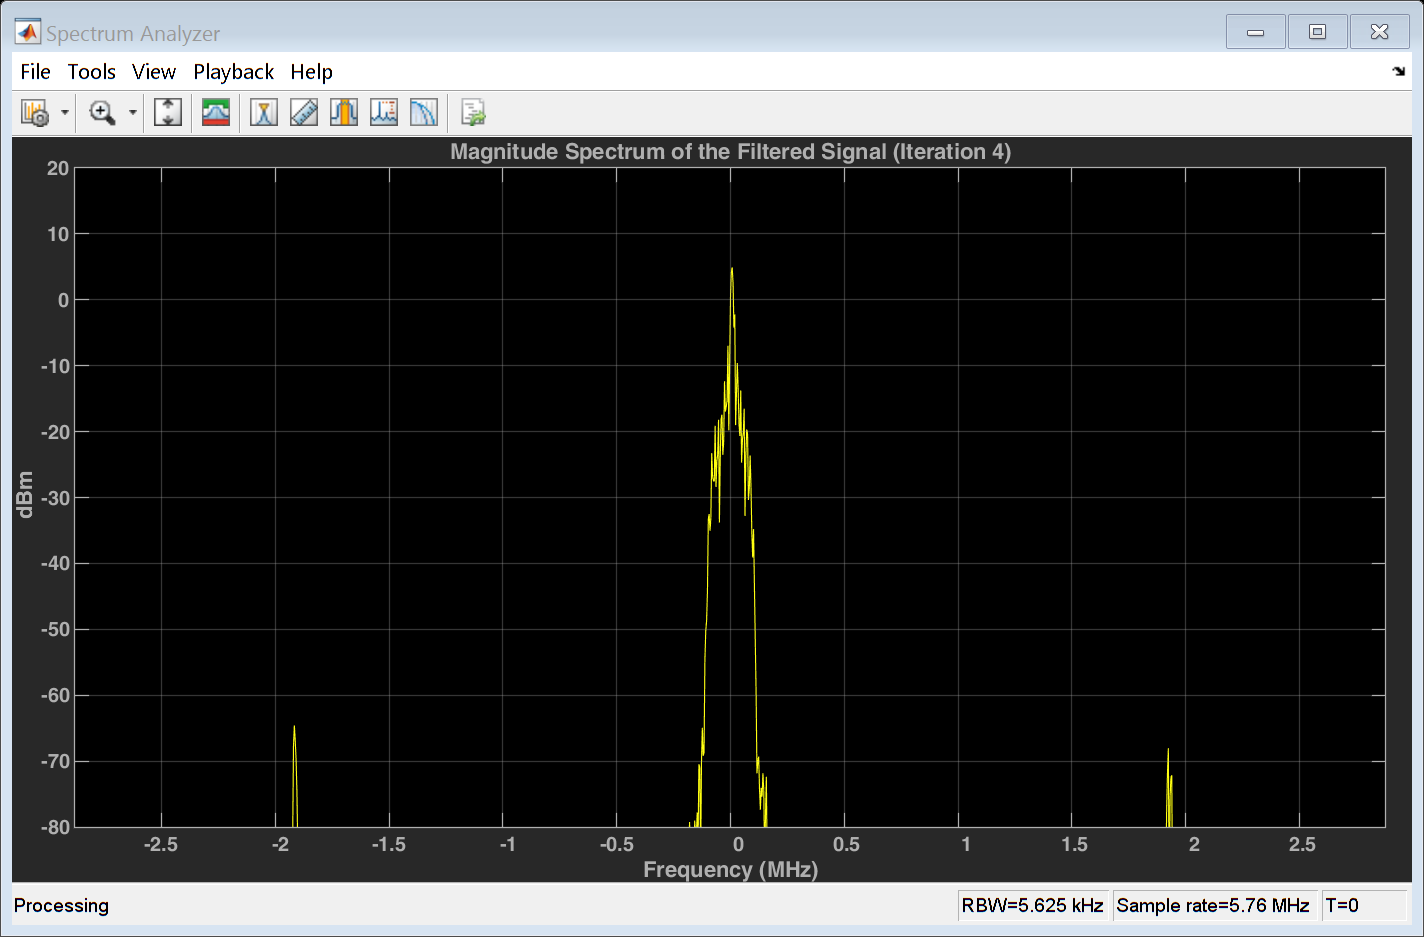


%Plot the magnitude spectrum of the baseband upsampled signal 
spectrumAnalyzer6 = dsp.SpectrumAnalyzer(1); %Define a Spectrum Analyzer object
spectrumAnalyzer6.SampleRate = fs;  %Setting the Spectrum Analyzer's Sample Rate with the value of fs
spectrumAnalyzer6(filtered_signal_4);
spectrumAnalyzer6.Title = "Magnitude Spectrum of the Filtered Signal (Iteration 4)";

### **Iteration 5:**

- **In this iteration, we tried to increase the filter order and we designed a FIR Filter with using the following filter specifications.**

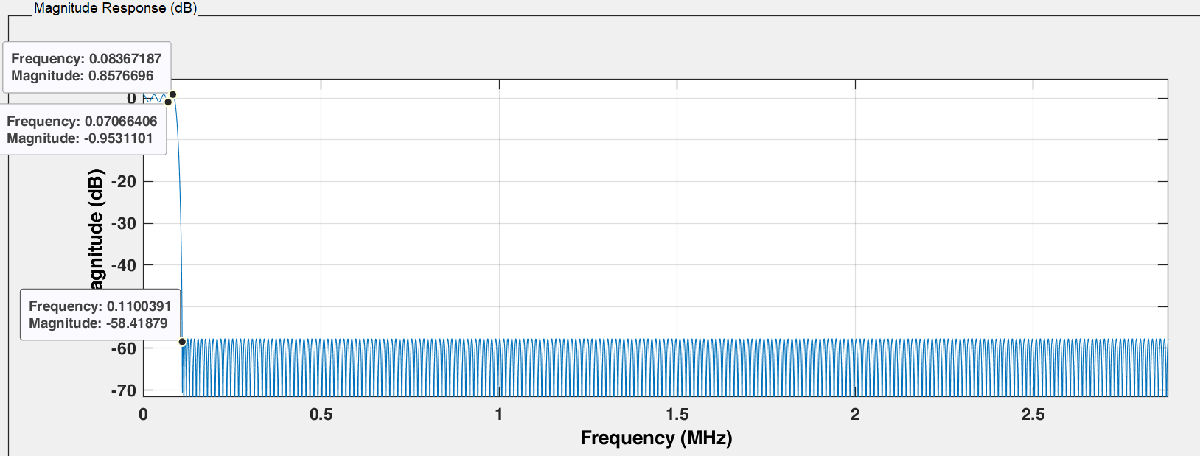

- **The above FIR filter is a Equiripple filter with**

**                 1) Number of taps (order) = 512**

**                 2) Fs = 5.76 MHz**

**                 3) Fpass = 90 kHz**

**                 4) Fstop = 110 kHz**

- **As shown in the above figure, the designed filter meets the required specifications.**

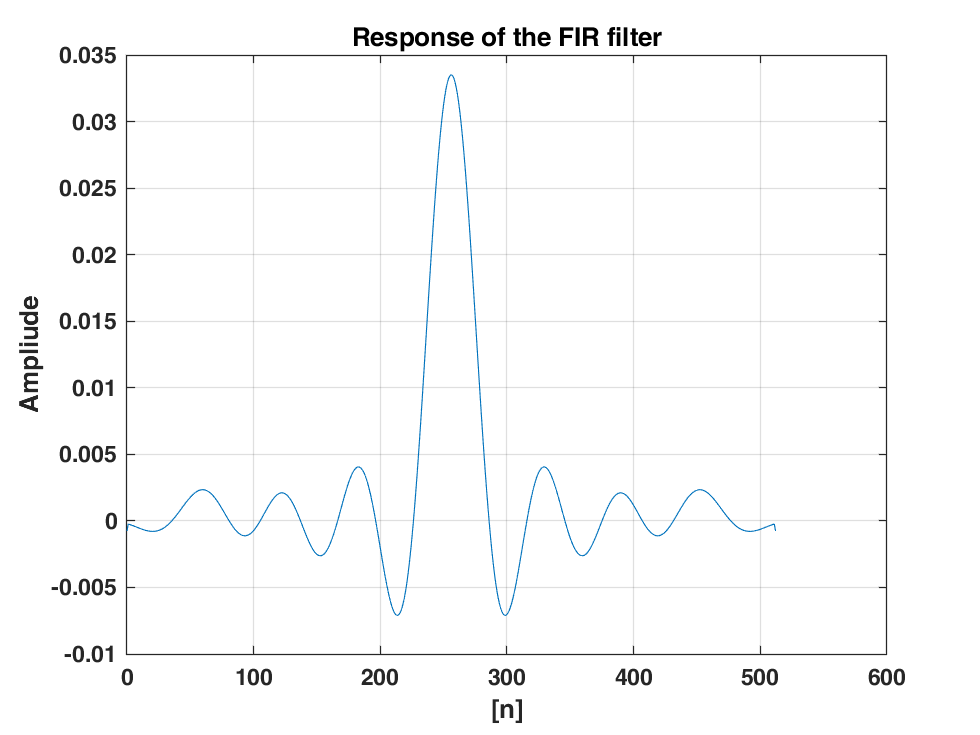

%512 taps Equiripple FIR Filter
filter5 = [-0.000761372242736025	-0.000231314906294299	-0.000264302198345288	-0.000298781741807327	-0.000334528414521710	-0.000371285011594368	-0.000408760451264735	-0.000446636862168642	-0.000484564986490264	-0.000522169335251379	-0.000559047344434120	-0.000594777183601058	-0.000628916242546382	-0.000661007718010545	-0.000690580777583806	-0.000717156557529931	-0.000740256757491219	-0.000759403169575766	-0.000774125707475574	-0.000783966130406653	-0.000788484364970979	-0.000787264052065214	-0.000779918819344019	-0.000766093679956487	-0.000745473875818859	-0.000717791012216039	-0.000682824981026441	-0.000640409421454723	-0.000590438466040685	-0.000532868704622466	-0.000467722175727866	-0.000395088697150748	-0.000315130595387197	-0.000228082641086562	-0.000134253274271142	-3.40229239608062e-05	7.21534615302512e-05	0.000183748547127280	0.000300163992969930	0.000420736248031861	0.000544738041714534	0.000671382394324076	0.000799829592169846	0.000929194495331228	0.00105854832182755	0.00118692950551343	0.00131335217888398	0.00143681280420851	0.00155629631612316	0.00167079255532718	0.00177930189923728	0.00188084532255422	0.00197447361739810	0.00205928237161333	0.00213441608270633	0.00219907825007783	0.00225254269110081	0.00229416400176590	0.00232338016690904	0.00233972699927261	0.00234284365931748	0.00233247765433837	0.00230848920452936	0.00227086339465519	0.00221969769541627	0.00215522071917127	0.00207778180673592	0.00198785724111591	0.00188604316429962	0.00177306485253441	0.00164975698601816	0.00151706632190990	0.00137605319801442	0.00122785258565732	0.00107371414104768	0.000914937272961420	0.000752907286056829	0.000589060400301776	0.000424864067091330	0.000261829576883814	0.000101467315356571	-5.47110850441067e-05	-0.000205211074083370	-0.000348570083016698	-0.000483378883112164	-0.000608279682639955	-0.000721999097688715	-0.000823357447687651	-0.000911276691540797	-0.000984801036784741	-0.00104311125469461	-0.00108552510727633	-0.00111150969084146	-0.00112069326746136	-0.00111287241296889	-0.00108801266142828	-0.00104626092158168	-0.000987943438068061	-0.000913562876056491	-0.000823790818445779	-0.000719475376731070	-0.000601629669555084	-0.000471426795979996	-0.000330190002227488	-0.000179386157247404	-2.06022314352619e-05	0.000144465692119471	0.000314029830409986	0.000486218164328834	0.000659097942677520	0.000830692548759337	0.000999011328677690	0.00116206272615501	0.00131788331875916	0.00146454885740178	0.00160020020682016	0.00172305517978488	0.00183144540521918	0.00192383292139974	0.00199883359236556	0.00205521494723526	0.00209192307600029	0.00210809520834286	0.00210309165472769	0.00207649278531864	0.00202810829294808	0.00195796326438492	0.00186633184581396	0.00175373479465456	0.00162095037909399	0.00146897481782546	0.00129903261117110	0.00111256661803097	0.000911265874237603	0.000697005736372573	0.000471830645223831	0.000237933078385063	-2.30445630379189e-06	-0.000246384717838715	-0.000491735693695274	-0.000735737813187322	-0.000975648304506824	-0.00120875288776706	-0.00143237797362989	-0.00164386664941910	-0.00184055400570697	-0.00202006969545482	-0.00217995497357785	-0.00231805008062401	-0.00243235643238247	-0.00252102530310051	-0.00258254635648751	-0.00261556418676785	-0.00261909028862136	-0.00259236307031636	-0.00253498749988409	-0.00244684621652995	-0.00232819422501022	-0.00217958842750815	-0.00200195652129112	-0.00179653789527212	-0.00156492821029713	-0.00130902715057426	-0.00103106476277104	-0.000733545939737515	-0.000419274264702096	-9.12892016042763e-05	0.000247126189953892	0.000592505649189358	0.000941199267973644	0.00128944099283874	0.00163335216321198	0.00196901039361167	0.00229246066557647	0.00259978322988419	0.00288710990943220	0.00315069202805842	0.00338691691084934	0.00359237339012497	0.00376387012600226	0.00389849739088963	0.00399364085142728	0.00404704056628742	0.00405680327718961	0.00402145161642389	0.00393992948448979	0.00381164990465929	0.00363649052065348	0.00341482648712686	0.00314752452762645	0.00283596910274993	0.00248204149344078	0.00208813639053785	0.00165713670702649	0.00119241582678436	0.000697799634254878	0.000177562896666764	-0.000363615655472108	-0.000920669019652763	-0.00148819665465530	-0.00206048524473105	-0.00263157501086017	-0.00319528871852401	-0.00374529880372284	-0.00427516430518244	-0.00477840395480887	-0.00524853249696639	-0.00567914055816436	-0.00606393728451365	-0.00639682032985028	-0.00667192340406017	-0.00688368842420730	-0.00702689888251495	-0.00709675961420452	-0.00708892255894756	-0.00699956397267135	-0.00682538787205162	-0.00656372319663187	-0.00621247933242885	-0.00577027945694216	-0.00523637514536024	-0.00461076185641917	-0.00389414073325661	-0.00308792249026246	-0.00219427680335144	-0.00121607134673297	-0.000156890196050417	0.000978966832540199	0.00218654203609808	0.00346023215388986	0.00479381211176656	0.00618048918667485	0.00761295807250586	0.00908341870718159	0.0105836567327843	0.0121050992422666	0.0136388785847751	0.0151758794182465	0.0167068296478923	0.0182223619895756	0.0197130861714669	0.0211696514242708	0.0225828390899893	0.0239436204908429	0.0252432288155085	0.0264732223937007	0.0276255700415972	0.0286927022686088	0.0296675761468584	0.0305437172151942	0.0313152899382203	0.0319771386160631	0.0325248345361115	0.0329546937550760	0.0332638220150601	0.0334501332389622	0.0335123771029461	0.0334501332389622	0.0332638220150601	0.0329546937550760	0.0325248345361115	0.0319771386160631	0.0313152899382203	0.0305437172151942	0.0296675761468584	0.0286927022686088	0.0276255700415972	0.0264732223937007	0.0252432288155085	0.0239436204908429	0.0225828390899893	0.0211696514242708	0.0197130861714669	0.0182223619895756	0.0167068296478923	0.0151758794182465	0.0136388785847751	0.0121050992422666	0.0105836567327843	0.00908341870718159	0.00761295807250586	0.00618048918667485	0.00479381211176656	0.00346023215388986	0.00218654203609808	0.000978966832540199	-0.000156890196050417	-0.00121607134673297	-0.00219427680335144	-0.00308792249026246	-0.00389414073325661	-0.00461076185641917	-0.00523637514536024	-0.00577027945694216	-0.00621247933242885	-0.00656372319663187	-0.00682538787205162	-0.00699956397267135	-0.00708892255894756	-0.00709675961420452	-0.00702689888251495	-0.00688368842420730	-0.00667192340406017	-0.00639682032985028	-0.00606393728451365	-0.00567914055816436	-0.00524853249696639	-0.00477840395480887	-0.00427516430518244	-0.00374529880372284	-0.00319528871852401	-0.00263157501086017	-0.00206048524473105	-0.00148819665465530	-0.000920669019652763	-0.000363615655472108	0.000177562896666764	0.000697799634254878	0.00119241582678436	0.00165713670702649	0.00208813639053785	0.00248204149344078	0.00283596910274993	0.00314752452762645	0.00341482648712686	0.00363649052065348	0.00381164990465929	0.00393992948448979	0.00402145161642389	0.00405680327718961	0.00404704056628742	0.00399364085142728	0.00389849739088963	0.00376387012600226	0.00359237339012497	0.00338691691084934	0.00315069202805842	0.00288710990943220	0.00259978322988419	0.00229246066557647	0.00196901039361167	0.00163335216321198	0.00128944099283874	0.000941199267973644	0.000592505649189358	0.000247126189953892	-9.12892016042763e-05	-0.000419274264702096	-0.000733545939737515	-0.00103106476277104	-0.00130902715057426	-0.00156492821029713	-0.00179653789527212	-0.00200195652129112	-0.00217958842750815	-0.00232819422501022	-0.00244684621652995	-0.00253498749988409	-0.00259236307031636	-0.00261909028862136	-0.00261556418676785	-0.00258254635648751	-0.00252102530310051	-0.00243235643238247	-0.00231805008062401	-0.00217995497357785	-0.00202006969545482	-0.00184055400570697	-0.00164386664941910	-0.00143237797362989	-0.00120875288776706	-0.000975648304506824	-0.000735737813187322	-0.000491735693695274	-0.000246384717838715	-2.30445630379189e-06	0.000237933078385063	0.000471830645223831	0.000697005736372573	0.000911265874237603	0.00111256661803097	0.00129903261117110	0.00146897481782546	0.00162095037909399	0.00175373479465456	0.00186633184581396	0.00195796326438492	0.00202810829294808	0.00207649278531864	0.00210309165472769	0.00210809520834286	0.00209192307600029	0.00205521494723526	0.00199883359236556	0.00192383292139974	0.00183144540521918	0.00172305517978488	0.00160020020682016	0.00146454885740178	0.00131788331875916	0.00116206272615501	0.000999011328677690	0.000830692548759337	0.000659097942677520	0.000486218164328834	0.000314029830409986	0.000144465692119471	-2.06022314352619e-05	-0.000179386157247404	-0.000330190002227488	-0.000471426795979996	-0.000601629669555084	-0.000719475376731070	-0.000823790818445779	-0.000913562876056491	-0.000987943438068061	-0.00104626092158168	-0.00108801266142828	-0.00111287241296889	-0.00112069326746136	-0.00111150969084146	-0.00108552510727633	-0.00104311125469461	-0.000984801036784741	-0.000911276691540797	-0.000823357447687651	-0.000721999097688715	-0.000608279682639955	-0.000483378883112164	-0.000348570083016698	-0.000205211074083370	-5.47110850441067e-05	0.000101467315356571	0.000261829576883814	0.000424864067091330	0.000589060400301776	0.000752907286056829	0.000914937272961420	0.00107371414104768	0.00122785258565732	0.00137605319801442	0.00151706632190990	0.00164975698601816	0.00177306485253441	0.00188604316429962	0.00198785724111591	0.00207778180673592	0.00215522071917127	0.00221969769541627	0.00227086339465519	0.00230848920452936	0.00233247765433837	0.00234284365931748	0.00233972699927261	0.00232338016690904	0.00229416400176590	0.00225254269110081	0.00219907825007783	0.00213441608270633	0.00205928237161333	0.00197447361739810	0.00188084532255422	0.00177930189923728	0.00167079255532718	0.00155629631612316	0.00143681280420851	0.00131335217888398	0.00118692950551343	0.00105854832182755	0.000929194495331228	0.000799829592169846	0.000671382394324076	0.000544738041714534	0.000420736248031861	0.000300163992969930	0.000183748547127280	7.21534615302512e-05	-3.40229239608062e-05	-0.000134253274271142	-0.000228082641086562	-0.000315130595387197	-0.000395088697150748	-0.000467722175727866	-0.000532868704622466	-0.000590438466040685	-0.000640409421454723	-0.000682824981026441	-0.000717791012216039	-0.000745473875818859	-0.000766093679956487	-0.000779918819344019	-0.000787264052065214	-0.000788484364970979	-0.000783966130406653	-0.000774125707475574	-0.000759403169575766	-0.000740256757491219	-0.000717156557529931	-0.000690580777583806	-0.000661007718010545	-0.000628916242546382	-0.000594777183601058	-0.000559047344434120	-0.000522169335251379	-0.000484564986490264	-0.000446636862168642	-0.000408760451264735	-0.000371285011594368	-0.000334528414521710	-0.000298781741807327	-0.000264302198345288	-0.000231314906294299	-0.000761372242736025];
filtered_signal_5 = filter(filter5, 1, waveform_upsampled);
%Plot the Response of the FIR filter
figure();
plot((0:length(filter5) - 1), filter5);
grid on; title('Response of the FIR filter'); xlabel('[n]'); ylabel('Ampliude');

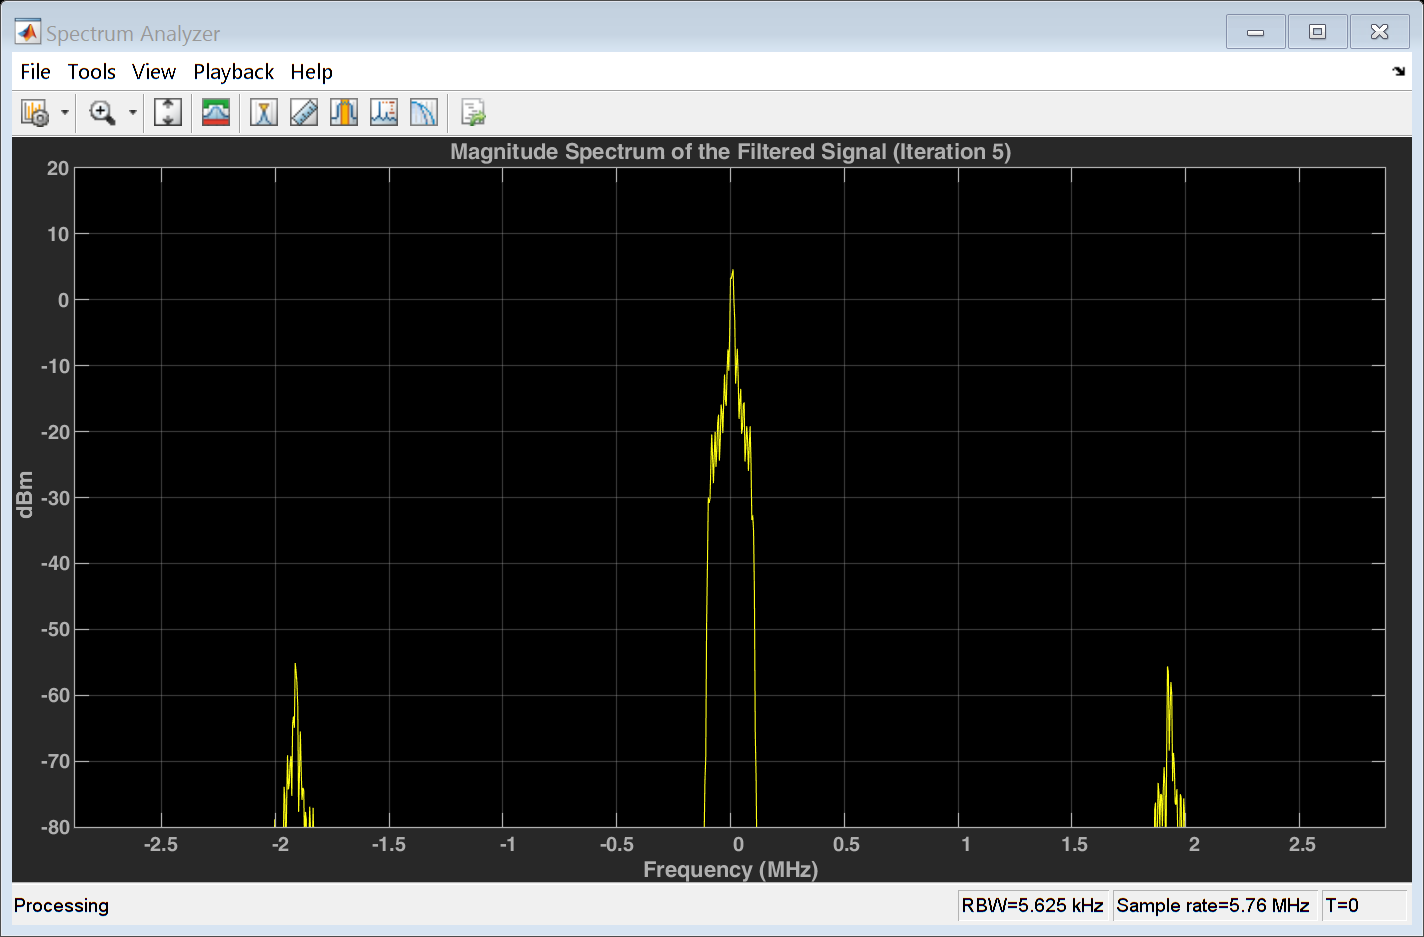


%Plot the magnitude spectrum of the baseband upsampled signal 
spectrumAnalyzer7 = dsp.SpectrumAnalyzer(1); %Define a Spectrum Analyzer object
spectrumAnalyzer7.SampleRate = fs;  %Setting the Spectrum Analyzer's Sample Rate with the value of fs
spectrumAnalyzer7(filtered_signal_5);
spectrumAnalyzer7.Title = "Magnitude Spectrum of the Filtered Signal (Iteration 5)";

### **Iteration 6:**

- **In this iteration, we tried to use another 512 taps filter and we designed a FIR Filter with using the following filter specifications.**

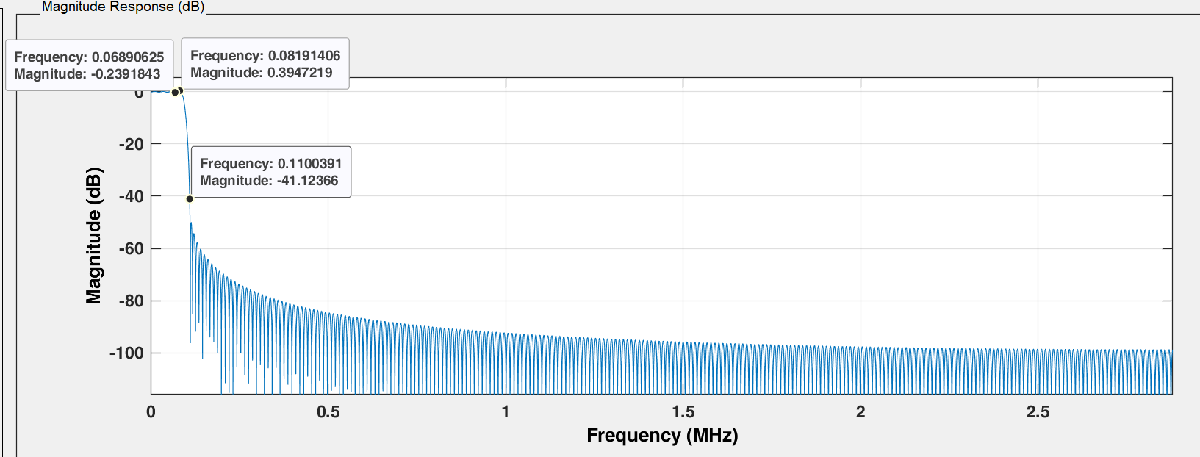

- **The above FIR filter is a Least-squares filter with**

**                 1) Number of taps (order) = 512**

**                 2) Fs = 5.76 MHz**

**                 3) Fpass = 90 kHz**

**                 4) Fstop = 110 kHz**

- **As shown in the above figure, the designed filter meets the required specifications, but the Equiripple FIR filter shows better results in the stopband attenuation as the stopband attenuation starts at -41 dB in this design.**

- **On the other hand, Least-squares FIR Filter shows better results in the Passband ripples as it is less than 2 dB peak to peak.**

%512 taps Least-squares FIR Filter
filter6 = [-1.61042952031860e-05	-2.60402854156543e-05	-3.75474449929105e-05	-5.06569360175225e-05	-6.53806809872547e-05	-8.17098215717806e-05	-9.96133708396398e-05	-0.000119037087843171	-0.000139902601762493	-0.000162106810677653	-0.000185521577472420	-0.000209993742391891	-0.000235345468403285	-0.000261374931775472	-0.000287857366234324	-0.000314546464709948	-0.000341176138115597	-0.000367462625838882	-0.000393106947740156	-0.000417797682501061	-0.000441214052211172	-0.000463029288188176	-0.000482914248263823	-0.000500541251201741	-0.000515588089611352	-0.000527742178750851	-0.000536704795035598	-0.000542195354947658	-0.000543955682434841	-0.000541754210846154	-0.000535390064022157	-0.000524696960383962	-0.000509546883777222	-0.000489853465453290	-0.000465575022926250	-0.000436717203540611	-0.000403335183419433	-0.000365535376026743	-0.000323476608851465	-0.000277370731673558	-0.000227482625467508	-0.000174129587185464	-0.000117680072384502	-5.85517848537525e-05	2.79089001702765e-06	6.58401034867585e-05	0.000130048400565597	0.000194833194950987	0.000259581832489643	0.000323657205639309	0.000386403873359219	0.000447154633092100	0.000505237484118834	0.000559982914672914	0.000610731438896762	0.000656841304102145	0.000697696283953785	0.000732713469212773	0.000761350964631090	0.000783115398547152	0.000797569150751594	0.000804337204317747	0.000803113528355478	0.000793666901070370	0.000775846086099069	0.000749584279838556	0.000714902753370030	0.000671913619560788	0.000620821663958964	0.000561925187111355	0.000495615815854738	0.000422377251864166	0.000342782937183055	0.000257492628493379	0.000167247884383449	7.28664826998855e-05	-2.47642019139723e-05	-0.000124694817138553	-0.000225922592667850	-0.000327400771718721	-0.000428048833382498	-0.000526763413204596	-0.000622429818485455	-0.000713934024798569	-0.000800175031261699	-0.000880077444310563	-0.000952604153234696	-0.00101676895565518	-0.00107164898755218	-0.00111639681047018	-0.00115025200820678	-0.00117255214667669	-0.00118274295376492	-0.00118038758085349	-0.00116517481431374	-0.00113692611357072	-0.00109560136231616	-0.00104130323099893	-0.000974280061765370	-0.000894927201442441	-0.000803786723824036	-0.000701545499285178	-0.000589031587444539	-0.000467208947041961	-0.000337170476200529	-0.000200129415596908	-5.74091665548514e-05	8.95684045161524e-05	0.000239296084817789	0.000390195747915805	0.000540633973672849	0.000688938711675816	0.000833416828867139	0.000972372367897114	0.00110412533013190	0.00122703078646267	0.00133949811023221	0.00144001011987491	0.00152714191438155	0.00159957918255714	0.00165613576731870	0.00169577026903469	0.00171760147716761	0.00172092242724438	0.00170521289041871	0.00167015011554640	0.00161561765868374	0.00154171215212506	0.00144874788437689	0.00133725908365271	0.00120799982037152	0.00106194146853604	0.000900267691513497	0.000724366944385745	0.000535822512398529	0.000336400132834681	0.000128033275560675	-8.71938147571242e-05	-0.000307065184514229	-0.000529254188404567	-0.000751346275993965	-0.000970863341680284	-0.00118528940989546	-0.00139209740721141	-0.00158877675508598	-0.00177286150157396	-0.00194195869765483	-0.00209377671409249	-0.00222615318811098	-0.00233708228578358	-0.00242474096599581	-0.00248751393522607	-0.00252401698922586	-0.00253311844797089	-0.00251395840395441	-0.00246596552092549	-0.00238887114041993	-0.00228272047673632	-0.00214788070718189	-0.00198504579322824	-0.00179523789941464	-0.00157980531012876	-0.00134041677946166	-0.00107905228583453	-0.000797990200662704	-0.000499790918576698	-0.000187277035262011	0.000136489802597021	0.000468235212892406	0.000804501359864503	0.00114167896716128	0.00147604179344955	0.00180378327017124	0.00212105497189483	0.00242400656345365	0.00270882684501735	0.00297178549671197	0.00320927510865585	0.00341785307054509	0.00359428288739685	0.00373557448489277	0.00383902306906663	0.00390224611091048	0.00392321803684928	0.00390030222091981	0.00383227989380726	0.00371837560751104	0.00355827892215565	0.00335216201310971	0.00310069293186048	0.00280504429270457	0.00246689719890903	0.00208844026618882	0.00167236364771925	0.00122184801301124	0.000740548482354756	0.000232573568692813	-0.000297540770776854	-0.000844861820776092	-0.00140409532995143	-0.00196962501858221	-0.00253555607545524	-0.00309576230323099	-0.00364393653023614	-0.00417364386843177	-0.00467837736275373	-0.00515161554649655	-0.00558688139127489	-0.00597780211866289	-0.00631816932415590	-0.00660199885284481	-0.00682358986031482	-0.00697758249189772	-0.00705901361858630	-0.00706337007866916	-0.00698663889041806	-0.00682535392285286	-0.00657663853856063	-0.00623824375454129	-0.00580858150382209	-0.00528675262180916	-0.00467256922665798	-0.00396657121193430	-0.00317003662204986	-0.00228498573590485	-0.00131417874133004	-0.000261106941750319	0.000870022503580315	0.00207430824397735	0.00334618268419296	0.00467944603188751	0.00606730620540489	0.00750242430496139	0.00897696529618393	0.0104826535037213	0.0120108324649258	0.0135525286498469	0.0150985185144507	0.0166393983194836	0.0181656561181001	0.0196677452915918	0.0211361589945346	0.0225615048586320	0.0239345792986007	0.0252464407637217	0.0264884812851706	0.0276524956819164	0.0287307478067305	0.0297160332385157	0.0306017378575242	0.0313818917758076	0.0320512181360930	0.0326051763378223	0.0330399992988932	0.0333527244152295	0.0335412179371572	0.0336041925411416	0.0335412179371572	0.0333527244152295	0.0330399992988932	0.0326051763378223	0.0320512181360930	0.0313818917758076	0.0306017378575242	0.0297160332385157	0.0287307478067305	0.0276524956819164	0.0264884812851706	0.0252464407637217	0.0239345792986007	0.0225615048586320	0.0211361589945346	0.0196677452915918	0.0181656561181001	0.0166393983194836	0.0150985185144507	0.0135525286498469	0.0120108324649258	0.0104826535037213	0.00897696529618393	0.00750242430496139	0.00606730620540489	0.00467944603188751	0.00334618268419296	0.00207430824397735	0.000870022503580315	-0.000261106941750319	-0.00131417874133004	-0.00228498573590485	-0.00317003662204986	-0.00396657121193430	-0.00467256922665798	-0.00528675262180916	-0.00580858150382209	-0.00623824375454129	-0.00657663853856063	-0.00682535392285286	-0.00698663889041806	-0.00706337007866916	-0.00705901361858630	-0.00697758249189772	-0.00682358986031482	-0.00660199885284481	-0.00631816932415590	-0.00597780211866289	-0.00558688139127489	-0.00515161554649655	-0.00467837736275373	-0.00417364386843177	-0.00364393653023614	-0.00309576230323099	-0.00253555607545524	-0.00196962501858221	-0.00140409532995143	-0.000844861820776092	-0.000297540770776854	0.000232573568692813	0.000740548482354756	0.00122184801301124	0.00167236364771925	0.00208844026618882	0.00246689719890903	0.00280504429270457	0.00310069293186048	0.00335216201310971	0.00355827892215565	0.00371837560751104	0.00383227989380726	0.00390030222091981	0.00392321803684928	0.00390224611091048	0.00383902306906663	0.00373557448489277	0.00359428288739685	0.00341785307054509	0.00320927510865585	0.00297178549671197	0.00270882684501735	0.00242400656345365	0.00212105497189483	0.00180378327017124	0.00147604179344955	0.00114167896716128	0.000804501359864503	0.000468235212892406	0.000136489802597021	-0.000187277035262011	-0.000499790918576698	-0.000797990200662704	-0.00107905228583453	-0.00134041677946166	-0.00157980531012876	-0.00179523789941464	-0.00198504579322824	-0.00214788070718189	-0.00228272047673632	-0.00238887114041993	-0.00246596552092549	-0.00251395840395441	-0.00253311844797089	-0.00252401698922586	-0.00248751393522607	-0.00242474096599581	-0.00233708228578358	-0.00222615318811098	-0.00209377671409249	-0.00194195869765483	-0.00177286150157396	-0.00158877675508598	-0.00139209740721141	-0.00118528940989546	-0.000970863341680284	-0.000751346275993965	-0.000529254188404567	-0.000307065184514229	-8.71938147571242e-05	0.000128033275560675	0.000336400132834681	0.000535822512398529	0.000724366944385745	0.000900267691513497	0.00106194146853604	0.00120799982037152	0.00133725908365271	0.00144874788437689	0.00154171215212506	0.00161561765868374	0.00167015011554640	0.00170521289041871	0.00172092242724438	0.00171760147716761	0.00169577026903469	0.00165613576731870	0.00159957918255714	0.00152714191438155	0.00144001011987491	0.00133949811023221	0.00122703078646267	0.00110412533013190	0.000972372367897114	0.000833416828867139	0.000688938711675816	0.000540633973672849	0.000390195747915805	0.000239296084817789	8.95684045161524e-05	-5.74091665548514e-05	-0.000200129415596908	-0.000337170476200529	-0.000467208947041961	-0.000589031587444539	-0.000701545499285178	-0.000803786723824036	-0.000894927201442441	-0.000974280061765370	-0.00104130323099893	-0.00109560136231616	-0.00113692611357072	-0.00116517481431374	-0.00118038758085349	-0.00118274295376492	-0.00117255214667669	-0.00115025200820678	-0.00111639681047018	-0.00107164898755218	-0.00101676895565518	-0.000952604153234696	-0.000880077444310563	-0.000800175031261699	-0.000713934024798569	-0.000622429818485455	-0.000526763413204596	-0.000428048833382498	-0.000327400771718721	-0.000225922592667850	-0.000124694817138553	-2.47642019139723e-05	7.28664826998855e-05	0.000167247884383449	0.000257492628493379	0.000342782937183055	0.000422377251864166	0.000495615815854738	0.000561925187111355	0.000620821663958964	0.000671913619560788	0.000714902753370030	0.000749584279838556	0.000775846086099069	0.000793666901070370	0.000803113528355478	0.000804337204317747	0.000797569150751594	0.000783115398547152	0.000761350964631090	0.000732713469212773	0.000697696283953785	0.000656841304102145	0.000610731438896762	0.000559982914672914	0.000505237484118834	0.000447154633092100	0.000386403873359219	0.000323657205639309	0.000259581832489643	0.000194833194950987	0.000130048400565597	6.58401034867585e-05	2.79089001702765e-06	-5.85517848537525e-05	-0.000117680072384502	-0.000174129587185464	-0.000227482625467508	-0.000277370731673558	-0.000323476608851465	-0.000365535376026743	-0.000403335183419433	-0.000436717203540611	-0.000465575022926250	-0.000489853465453290	-0.000509546883777222	-0.000524696960383962	-0.000535390064022157	-0.000541754210846154	-0.000543955682434841	-0.000542195354947658	-0.000536704795035598	-0.000527742178750851	-0.000515588089611352	-0.000500541251201741	-0.000482914248263823	-0.000463029288188176	-0.000441214052211172	-0.000417797682501061	-0.000393106947740156	-0.000367462625838882	-0.000341176138115597	-0.000314546464709948	-0.000287857366234324	-0.000261374931775472	-0.000235345468403285	-0.000209993742391891	-0.000185521577472420	-0.000162106810677653	-0.000139902601762493	-0.000119037087843171	-9.96133708396398e-05	-8.17098215717806e-05	-6.53806809872547e-05	-5.06569360175225e-05	-3.75474449929105e-05	-2.60402854156543e-05	-1.61042952031860e-05];
filtered_signal_6 = filter(filter6, 1, waveform_upsampled)

filtered_signal_6 =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0001 + 0.0000i
   0.0001 + 0.0000i


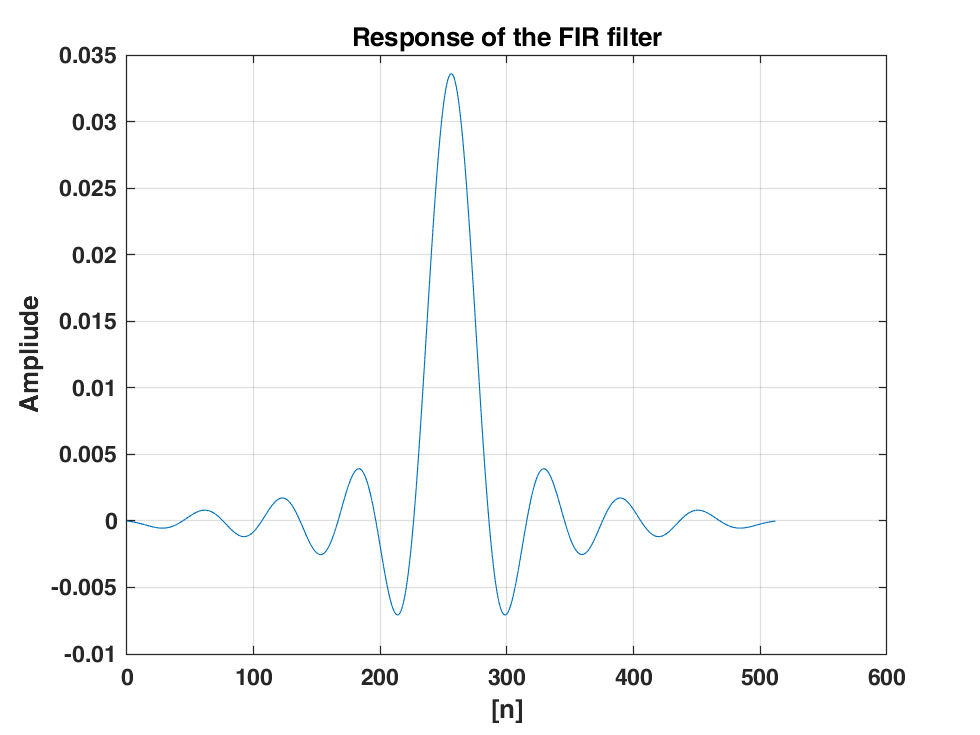

%Plot the Response of the FIR filter
figure();
plot((0:length(filter6) - 1), filter6);
grid on; title('Response of the FIR filter'); xlabel('[n]'); ylabel('Ampliude');

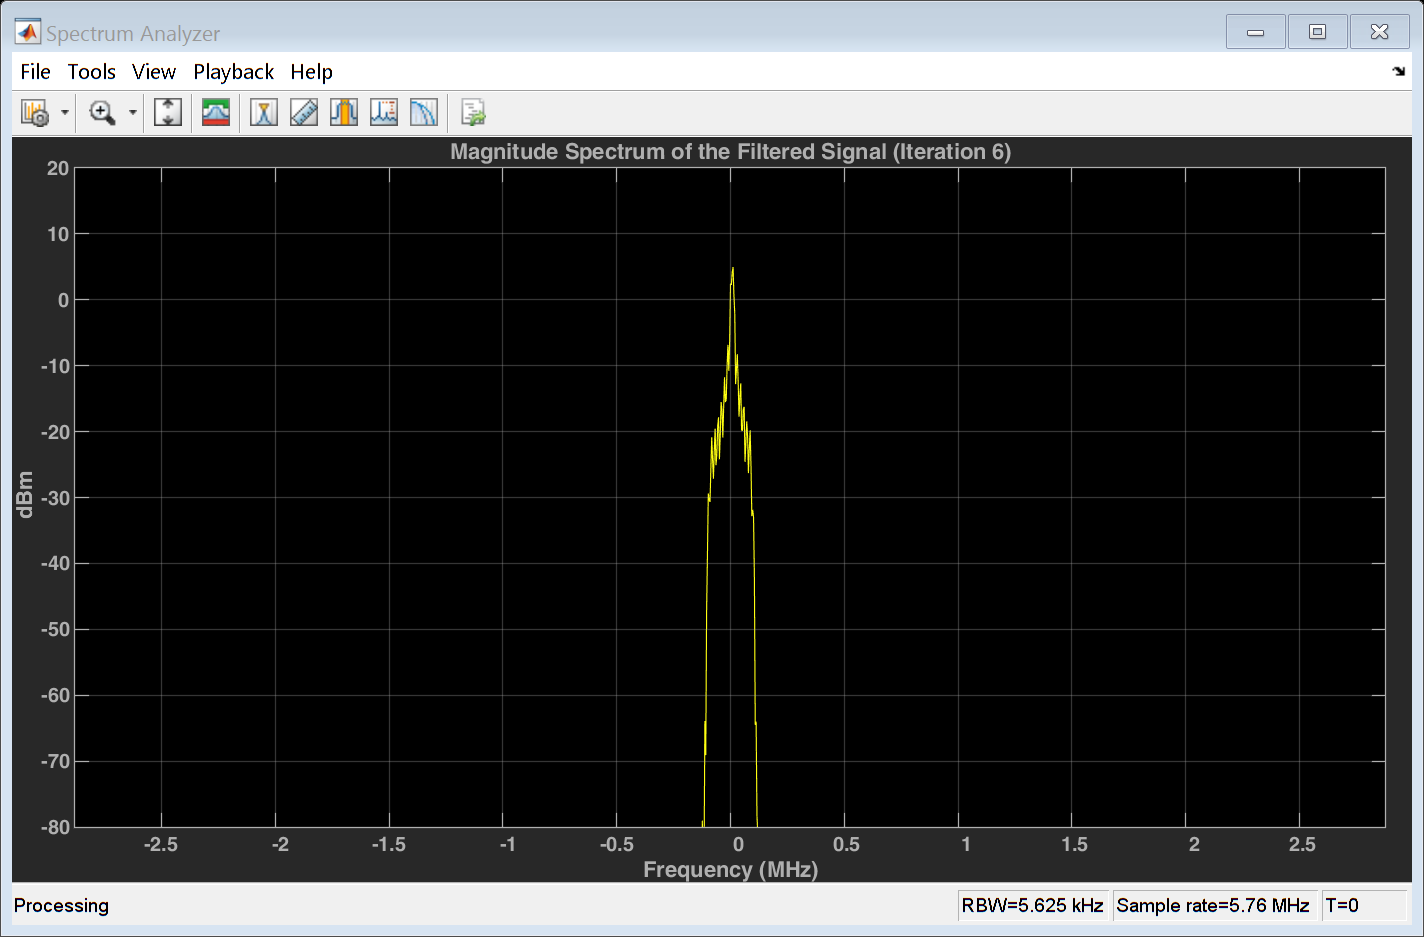


%Plot the magnitude spectrum of the baseband upsampled signal 
spectrumAnalyzer8 = dsp.SpectrumAnalyzer(1); %Define a Spectrum Analyzer object
spectrumAnalyzer8.SampleRate = fs;  %Setting the Spectrum Analyzer's Sample Rate with the value of fs
spectrumAnalyzer8(filtered_signal_6);
spectrumAnalyzer8.Title = "Magnitude Spectrum of the Filtered Signal (Iteration 6)";

## Digital UP Conversion:

- **NB-IoT waveform for the 8 NB-IoT devices is constructed.**

- **Each NB-IoT signal should map to a suitable IF frequency at the base station receiver.**

- **IF is choosen to as follows:**

**            IF1 = 200 kHz                                                 IF2 = 400 kHz**

**            IF3 =  600 kHz                                                IF4 = 800 kHz**

**            IF5 =  1000 kHz                                              IF6 = 1200 kHz**

**            IF7 =  1400 kHz                                              IF8 = 1600 kHz**

- **We repeated this step for the 6 filtered signals that were obtained from the 6 iterations in FIR Filter Stage.**

- **Each filtered signal will be up converted to its Intermediate Frequency IF using the following Equation:**


$$\textrm{Up}\;\textrm{Converted}\;\textrm{Signal}=\textrm{Filtered}\;\textrm{Signal}*{\mathit{\mathbf{e}}}^{-\mathit{\mathbf{j}}*2\pi *\textrm{IF}*\mathit{\mathbf{n}}*{\mathit{\mathbf{t}}}_{\mathit{\mathbf{s}}} }$$


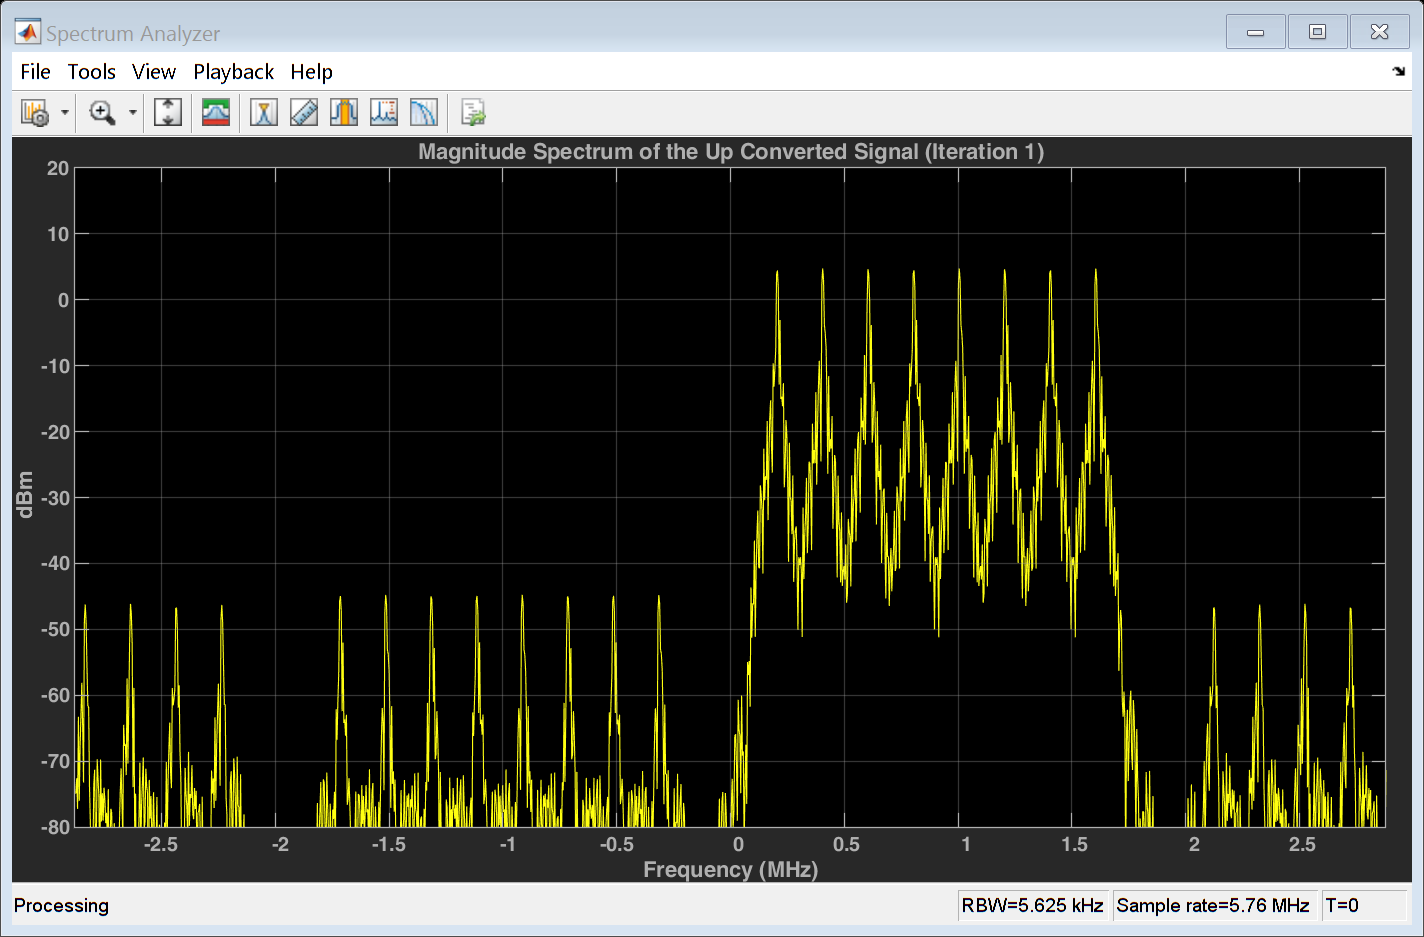

%Iteration 1
IF =(200:200:1600)*10^3;  %IF for the 8 NB-IoT devices
ts =1/fs;    %Sampling time
n=0:length(filtered_signal_1)-1;
Up_Converted_1=[];  %Vector to hole an up converted signal
sum_upconv_1=(zeros(1,length(n)))'; %Variable to hole the 8 up converted signals
%Up Conversion
for i=1:1:length(IF)
    Upconv = exp(-1i*2*pi*IF(i)*n*ts);
    upconverted= Upconv'.*filtered_signal_1;
    Up_Converted_1 =[Up_Converted_1 upconverted];
    sum_upconv_1 = sum_upconv_1 + upconverted;
end

%Plot the magnitude spectrum of the baseband upsampled signal 
spectrumAnalyzer9 = dsp.SpectrumAnalyzer(1); %Define a Spectrum Analyzer object
spectrumAnalyzer9.SampleRate = fs;  %Setting the Spectrum Analyzer's Sample Rate with the value of fs
spectrumAnalyzer9(sum_upconv_1);
spectrumAnalyzer9.Title = "Magnitude Spectrum of the Up Converted Signal (Iteration 1)";

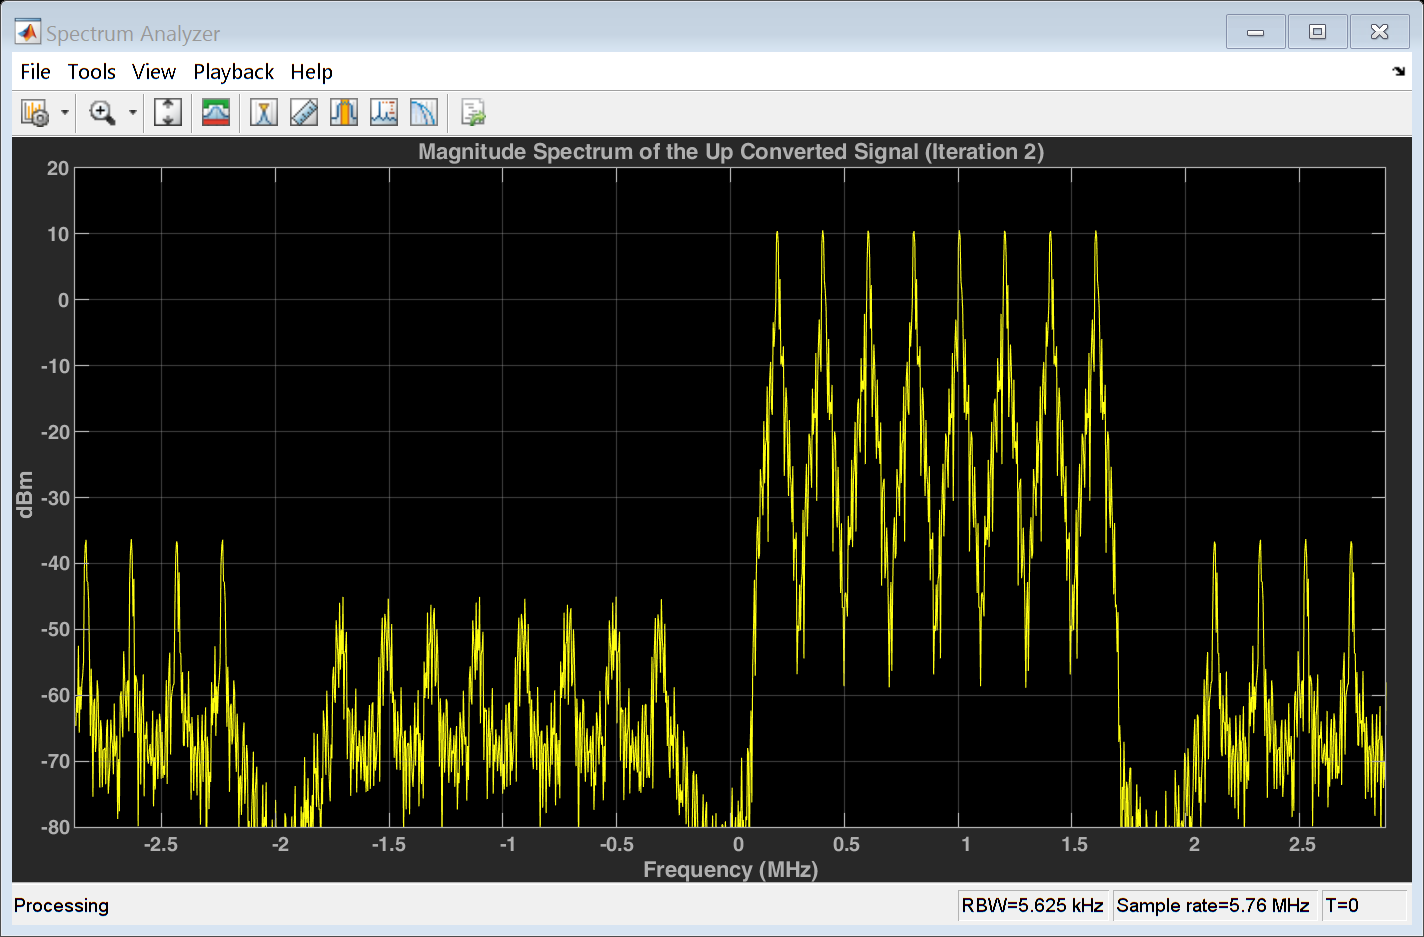


%Iteration 2
n=0:length(filtered_signal_2)-1 ; 
Up_Converted_2=[];  %Vector to hole an up converted signal
sum_upconv_2=(zeros(1,length(n)))'; %Variable to hole the 8 up converted signals
%Up Conversion
for i=1:1:length(IF)
    Upconv = exp(-1i*2*pi*IF(i)*n*ts);
    upconverted= Upconv'.*filtered_signal_2;
    Up_Converted_2 =[Up_Converted_2 upconverted];
    sum_upconv_2 = sum_upconv_2 + upconverted;
end

%Plot the magnitude spectrum of the baseband upsampled signal 
spectrumAnalyzer10 = dsp.SpectrumAnalyzer(1); %Define a Spectrum Analyzer object
spectrumAnalyzer10.SampleRate = fs;  %Setting the Spectrum Analyzer's Sample Rate with the value of fs
spectrumAnalyzer10(sum_upconv_2);
spectrumAnalyzer10.Title = "Magnitude Spectrum of the Up Converted Signal (Iteration 2)";

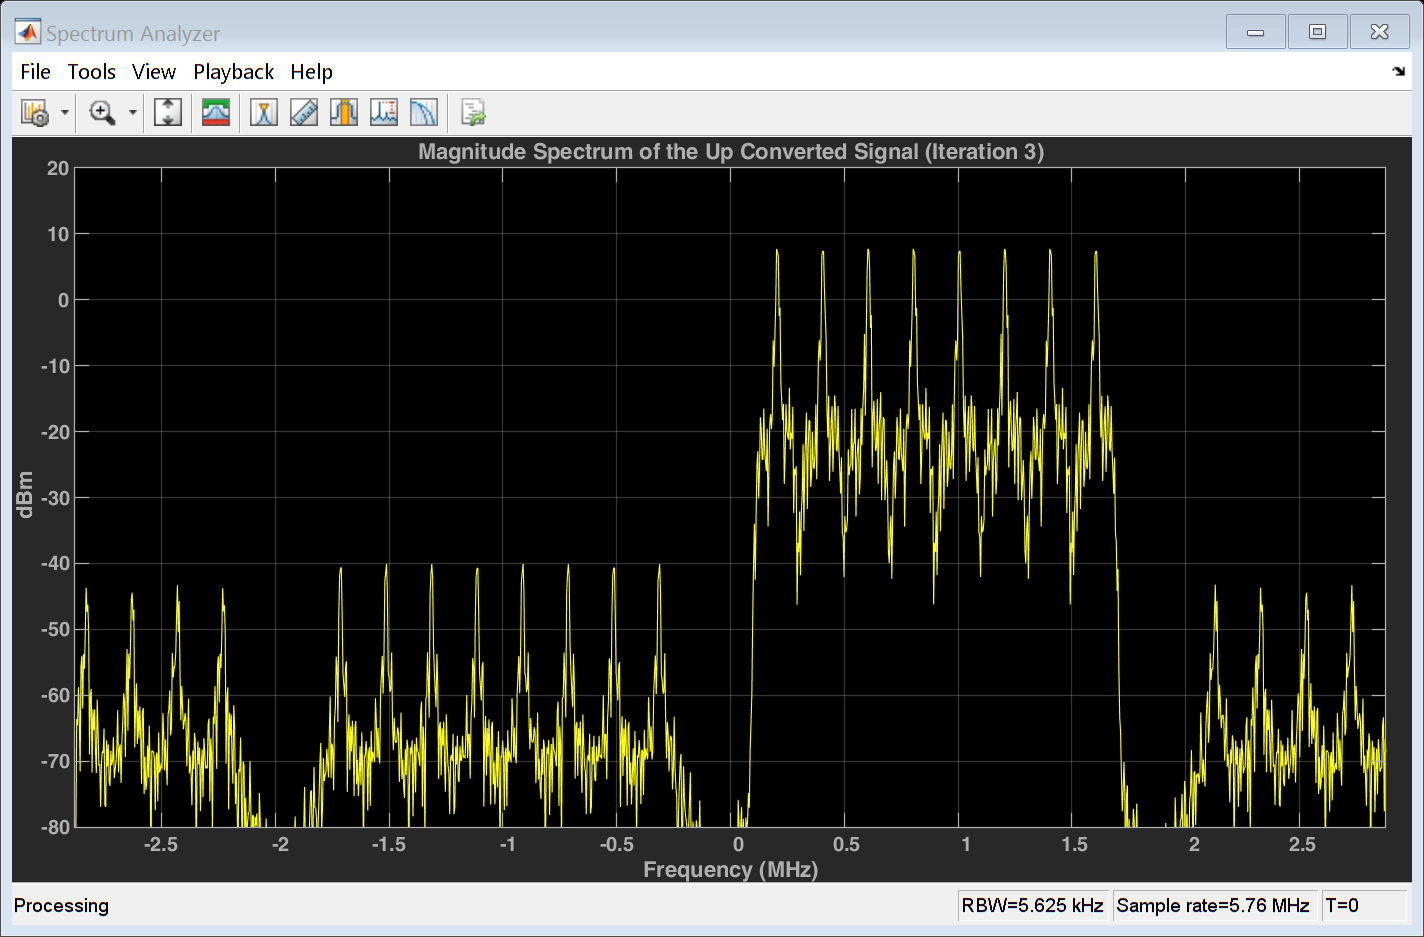


%Iteration 3
n=0:length(filtered_signal_3)-1  ;
Up_Converted_3=[];  %Vector to hole an up converted signal
sum_upconv_3=(zeros(1,length(n)))'; %Variable to hole the 8 up converted signals
%Up Conversion
for i=1:1:length(IF)
    Upconv = exp(-1i*2*pi*IF(i)*n*ts);
    upconverted= Upconv'.*filtered_signal_3;
    Up_Converted_3 =[Up_Converted_3 upconverted];
    sum_upconv_3 = sum_upconv_3 + upconverted;
end

%Plot the magnitude spectrum of the baseband upsampled signal 
spectrumAnalyzer11 = dsp.SpectrumAnalyzer(1); %Define a Spectrum Analyzer object
spectrumAnalyzer11.SampleRate = fs;  %Setting the Spectrum Analyzer's Sample Rate with the value of fs
spectrumAnalyzer11(sum_upconv_3);
spectrumAnalyzer11.Title = "Magnitude Spectrum of the Up Converted Signal (Iteration 3)";

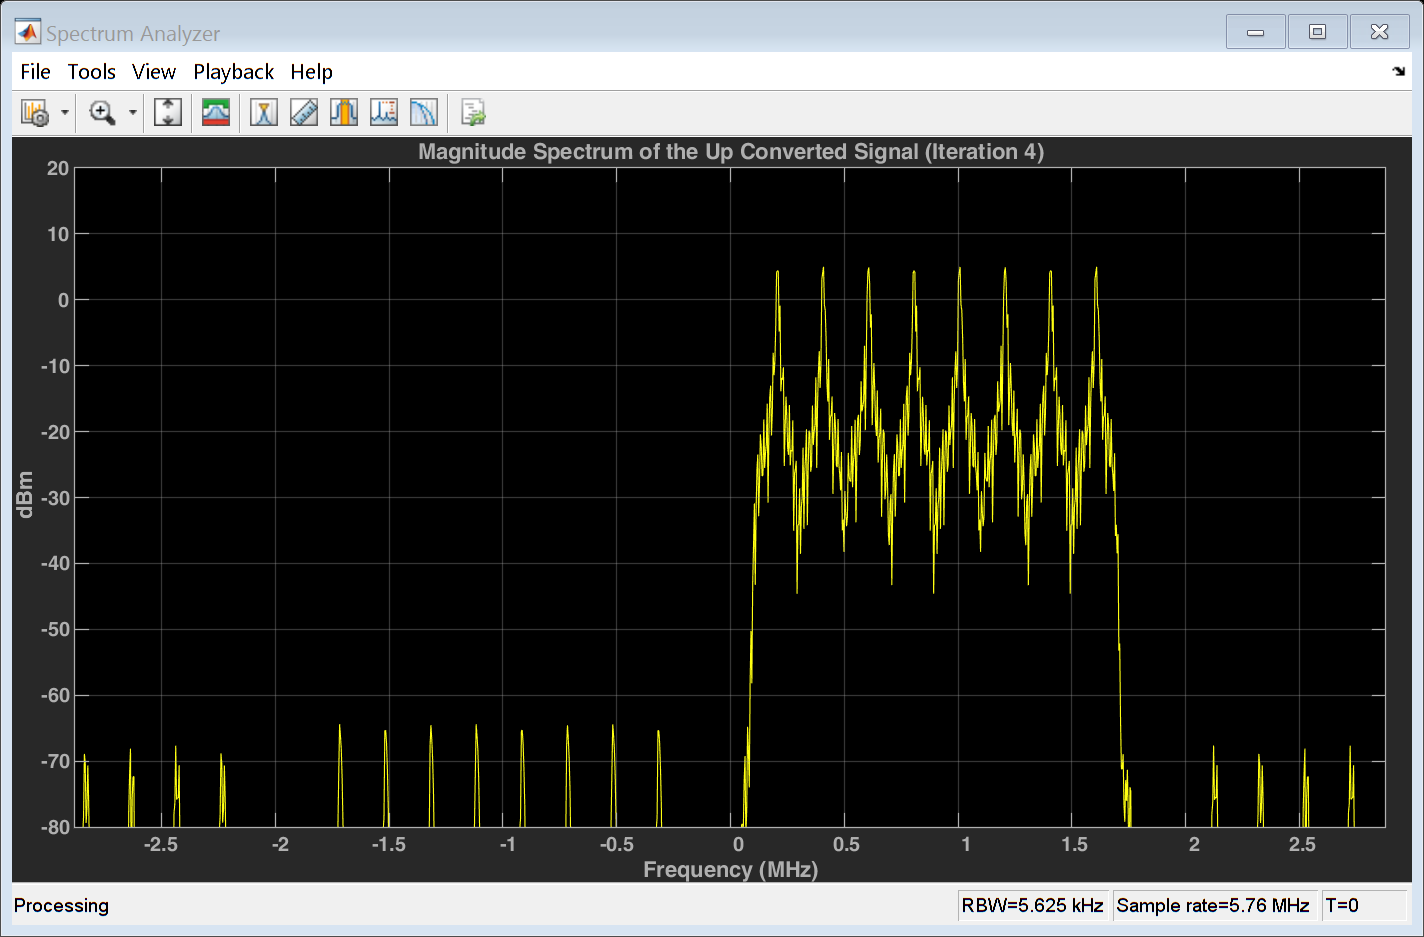


%Iteration 4
n=0:length(filtered_signal_4)-1  ;
Up_Converted_4=[];  %Vector to hole an up converted signal
sum_upconv_4=(zeros(1,length(n)))'; %Variable to hole the 8 up converted signals
%Up Conversion
for i=1:1:length(IF)
    Upconv = exp(-1i*2*pi*IF(i)*n*ts);
    upconverted= Upconv'.*filtered_signal_4;
    Up_Converted_4 =[Up_Converted_4 upconverted];
    sum_upconv_4 = sum_upconv_4 + upconverted;
end

%Plot the magnitude spectrum of the baseband upsampled signal 
spectrumAnalyzer12 = dsp.SpectrumAnalyzer(1); %Define a Spectrum Analyzer object
spectrumAnalyzer12.SampleRate = fs;  %Setting the Spectrum Analyzer's Sample Rate with the value of fs
spectrumAnalyzer12(sum_upconv_4);
spectrumAnalyzer12.Title = "Magnitude Spectrum of the Up Converted Signal (Iteration 4)";

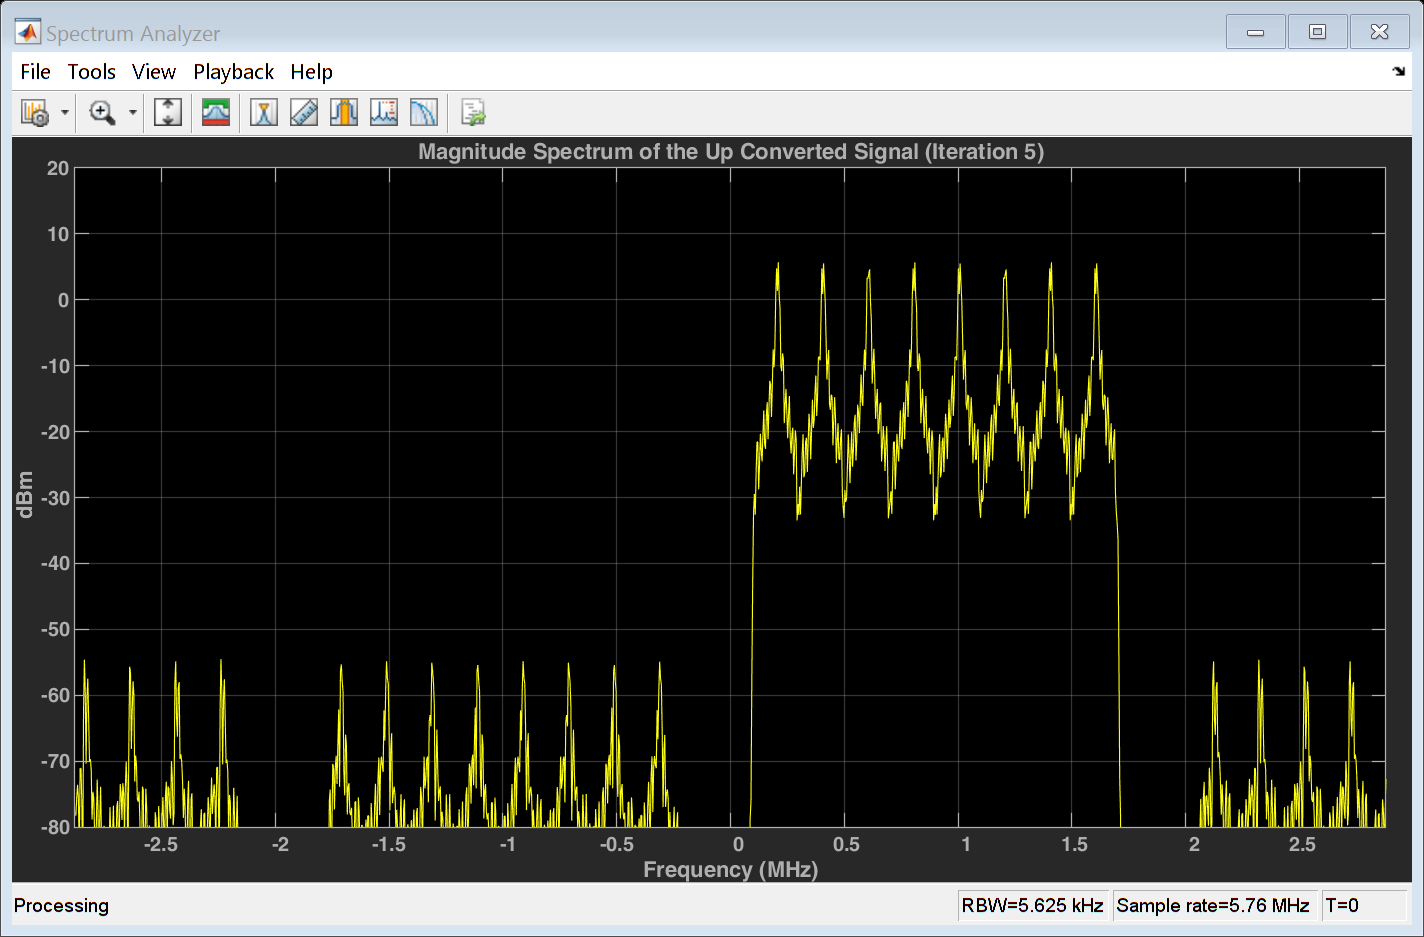


%Iteration 5
n=0:length(filtered_signal_5)-1 ; 
Up_Converted_5=[];  %Vector to hole an up converted signal
sum_upconv_5=(zeros(1,length(n)))'; %Variable to hole the 8 up converted signals
%Up Conversion
for i=1:1:length(IF)
    Upconv = exp(-1i*2*pi*IF(i)*n*ts);
    upconverted= Upconv'.*filtered_signal_5;
    Up_Converted_5 =[Up_Converted_5 upconverted];
    sum_upconv_5 = sum_upconv_5 + upconverted;
end

%Plot the magnitude spectrum of the baseband upsampled signal 
spectrumAnalyzer13 = dsp.SpectrumAnalyzer(1); %Define a Spectrum Analyzer object
spectrumAnalyzer13.SampleRate = fs;  %Setting the Spectrum Analyzer's Sample Rate with the value of fs
spectrumAnalyzer13(sum_upconv_5);
spectrumAnalyzer13.Title = "Magnitude Spectrum of the Up Converted Signal (Iteration 5)";

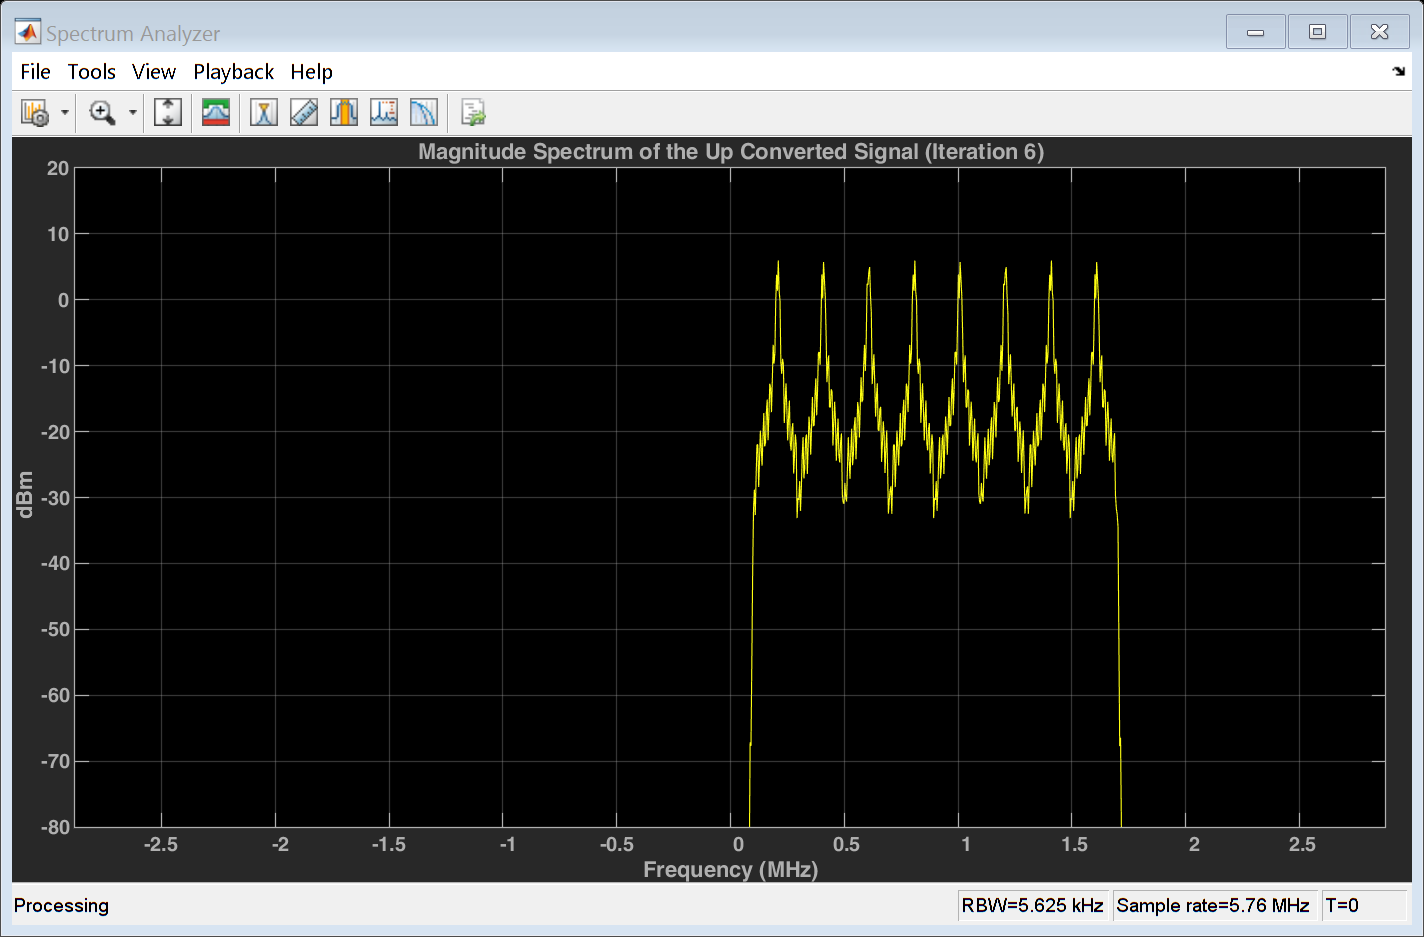


%Iteration 6
n=0:length(filtered_signal_6)-1  ;
Up_Converted_6=[];  %Vector to hole an up converted signal
sum_upconv_6=(zeros(1,length(n)))'; %Variable to hole the 8 up converted signals
%Up Conversion
for i=1:1:length(IF)
    Upconv = exp(-1i*2*pi*IF(i)*n*ts);
    upconverted= Upconv'.*filtered_signal_6;
    Up_Converted_6 =[Up_Converted_6 upconverted];
    sum_upconv_6 = sum_upconv_6 + upconverted;
end

%Plot the magnitude spectrum of the baseband upsampled signal 
spectrumAnalyzer14 = dsp.SpectrumAnalyzer(1); %Define a Spectrum Analyzer object
spectrumAnalyzer14.SampleRate = fs;  %Setting the Spectrum Analyzer's Sample Rate with the value of fs
spectrumAnalyzer14(sum_upconv_6);
spectrumAnalyzer14.Title = "Magnitude Spectrum of the Up Converted Signal (Iteration 6)";

## 3) Reciever

- [**Digital Down conversion**](#M_5ABB78A5)

- [**FIR Filter**](#M_4502E302)

- [**Downsampling**](#M_966D300D)

## Digital Down conversion:

- **The Receiver role is to construct each signal from the received waveform of the 8 NB-IoT devices.**

- **Digital Down Conversion is needed to center each of the 8 signals at 0 Hz.**

- **DDC is a necessary step before using the FIR Filter since the filter passes only the range of frequencies from -90 kHz to 90 kHz.**

- **The values IF is for each of the 8 signals is needed in this step:**

**            IF1 = 200 kHz                                                 IF2 = 400 kHz**

**            IF3 =  600 kHz                                                IF4 = 800 kHz**

**            IF5 =  1000 kHz                                              IF6 = 1200 kHz**

**            IF7 =  1400 kHz                                              IF8 = 1600 kHz**

- **We repeated this step for the 6 received signals that were obtained from the 6 iterations in Transmitter Stage.**

- **Each Received signal will be down converted using the following Equation:**


$$\textrm{Down}\;\textrm{Converted}\;\textrm{Signal}=\textrm{Received}\;\textrm{Signal}*{\mathit{\mathbf{e}}}^{+\mathit{\mathbf{j}}*2\pi *\textrm{IF}*\mathit{\mathbf{n}}*{\mathit{\mathbf{t}}}_{\mathit{\mathbf{s}}} }$$


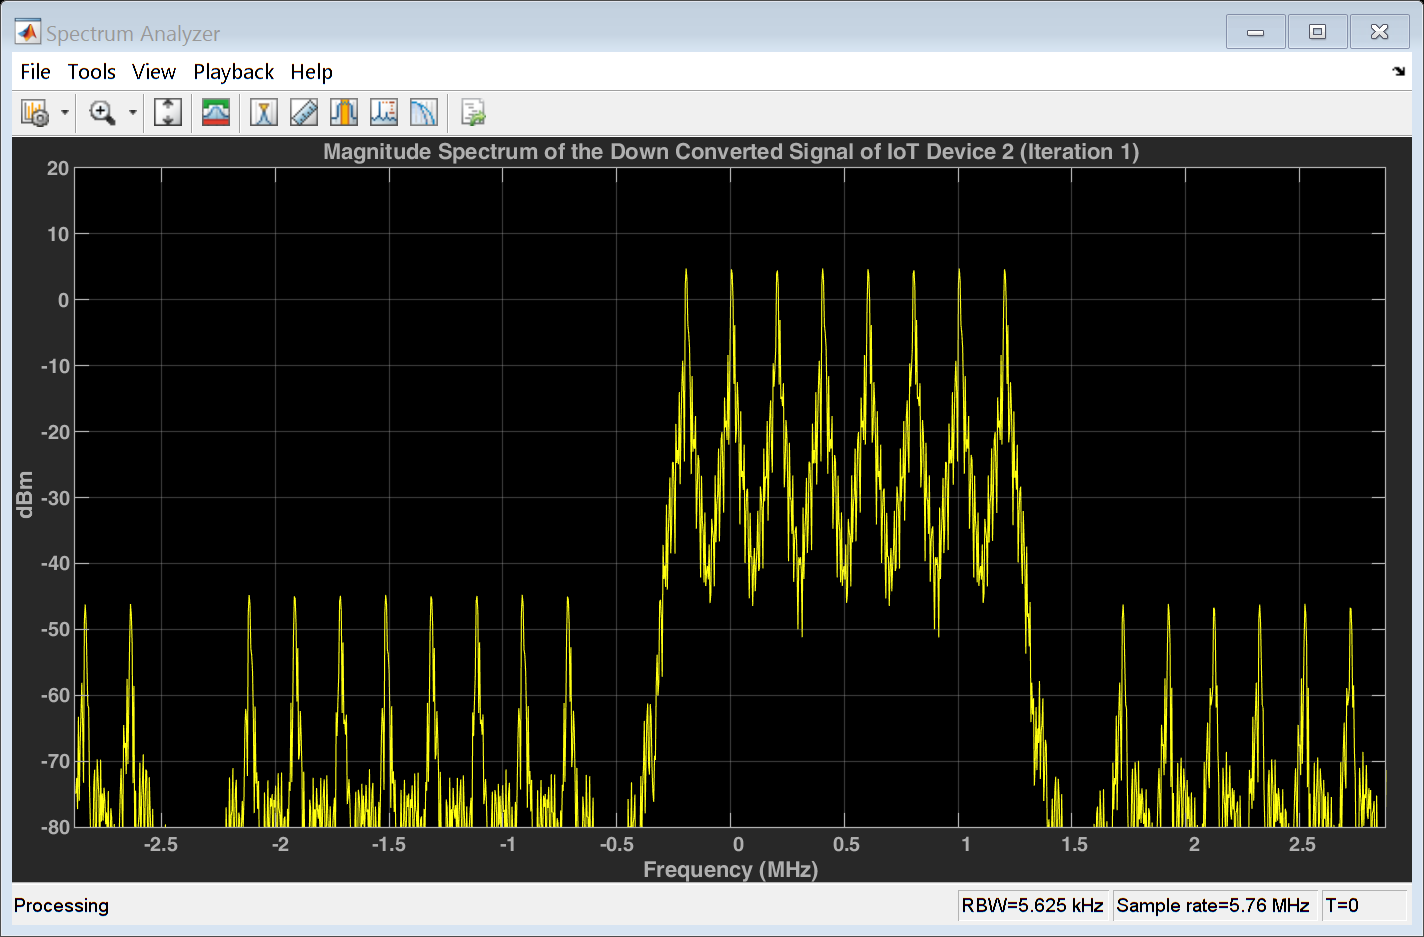

FD = (-200:-200:-1600 )*10^3; %IF for the 8 NB-IoT devices scaled with -ve sign to be used in the above equation
ts =1/fs;    %Sampling time

%Iteration 1
n = 0:length(sum_upconv_1)-1;
Down_Converted_1 = [];   %Vector to hole a down converted signal

%Down Conversion
for i=1:1:length(FD)
    Downconv = exp(-1i*2*pi*FD(i)*n*ts);
    downconverted = Downconv'.* sum_upconv_1 ;
    Down_Converted_1 = [Down_Converted_1 downconverted];
end

%Plot the magnitude spectrum of the Down Converted signal 
spectrumAnalyzer15 = dsp.SpectrumAnalyzer(1);
spectrumAnalyzer15.SampleRate = fs;
spectrumAnalyzer15(Down_Converted_1(:,2));
spectrumAnalyzer15.Title = "Magnitude Spectrum of the Down Converted Signal of IoT Device 2 (Iteration 1)";

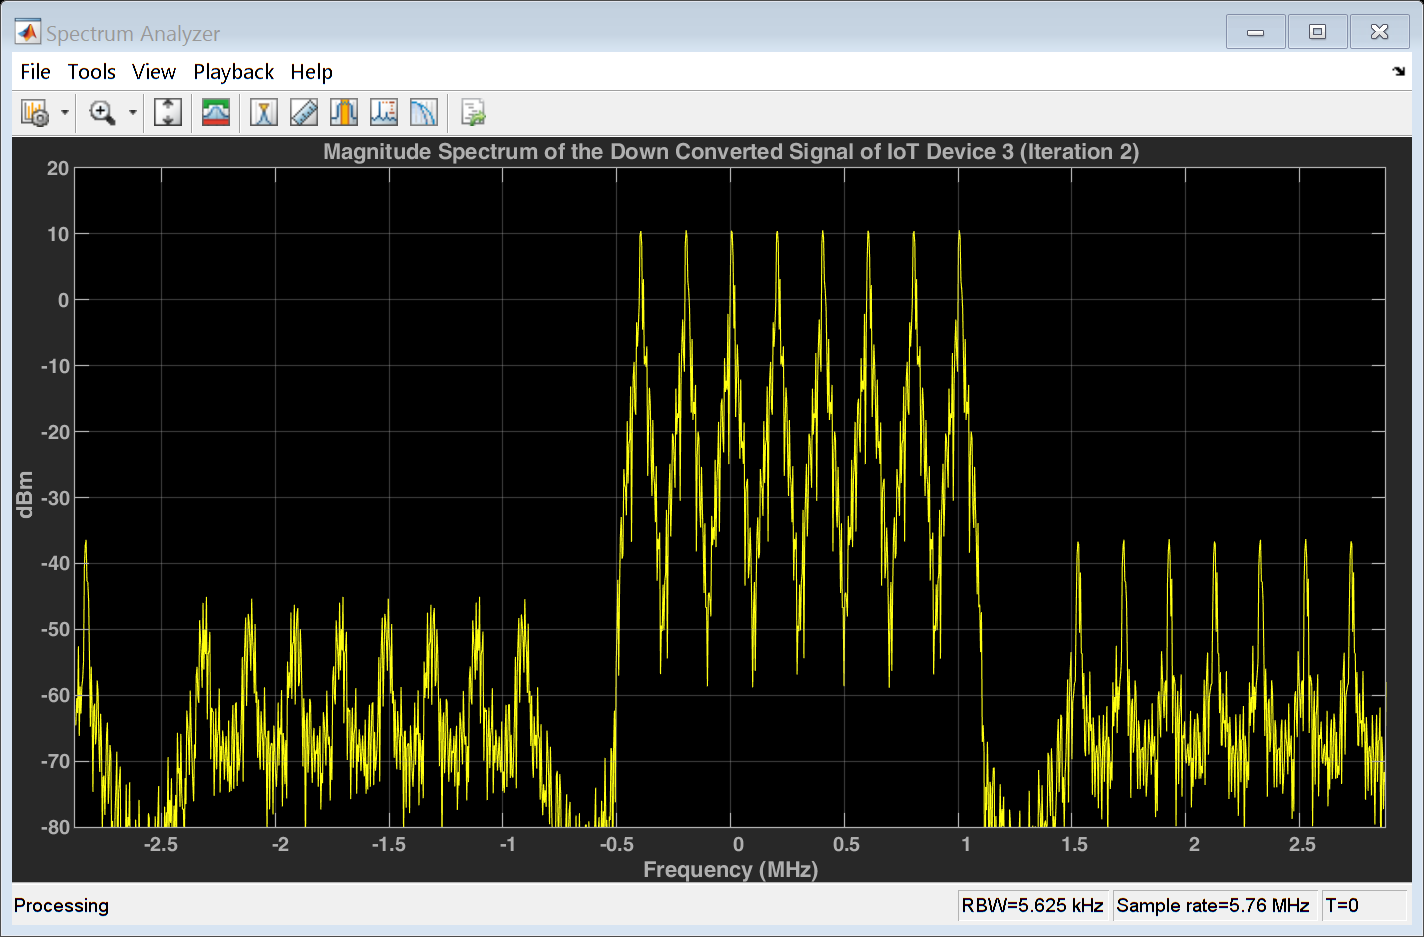

%Iteration 2
n = 0:length(sum_upconv_2)-1;
Down_Converted_2 = [];   %Vector to hole a down converted signal

%Down Conversion
for i=1:1:length(FD)
    Downconv = exp(-1i*2*pi*FD(i)*n*ts);
    downconverted = Downconv'.* sum_upconv_2 ;
    Down_Converted_2 = [Down_Converted_2 downconverted];
end

%Plot the magnitude spectrum of the Down Converted signal 
spectrumAnalyzer16 = dsp.SpectrumAnalyzer(1);
spectrumAnalyzer16.SampleRate = fs;
spectrumAnalyzer16(Down_Converted_2(:,3));
spectrumAnalyzer16.Title = "Magnitude Spectrum of the Down Converted Signal of IoT Device 3 (Iteration 2)";

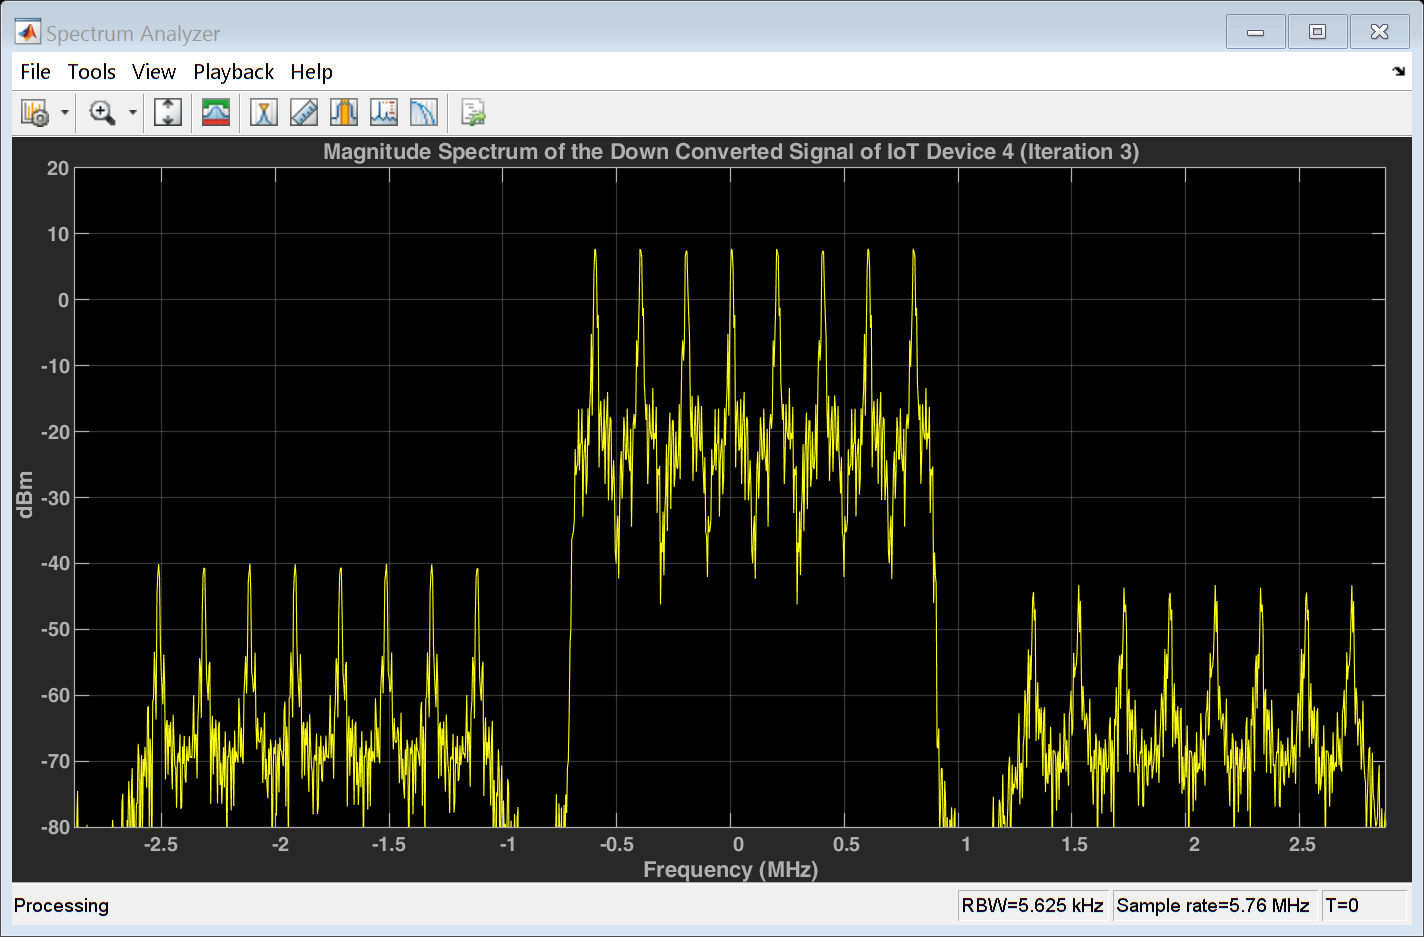

%Iteration 3
n = 0:length(sum_upconv_3)-1;
Down_Converted_3 = [];   %Vector to hole a down converted signal

%Down Conversion
for i=1:1:length(FD)
    Downconv = exp(-1i*2*pi*FD(i)*n*ts);
    downconverted = Downconv'.* sum_upconv_3 ;
    Down_Converted_3 = [Down_Converted_3 downconverted];
end

%Plot the magnitude spectrum of the Down Converted signal 
spectrumAnalyzer16 = dsp.SpectrumAnalyzer(1);
spectrumAnalyzer16.SampleRate = fs;
spectrumAnalyzer16(Down_Converted_3(:,4));
spectrumAnalyzer16.Title = "Magnitude Spectrum of the Down Converted Signal of IoT Device 4 (Iteration 3)";

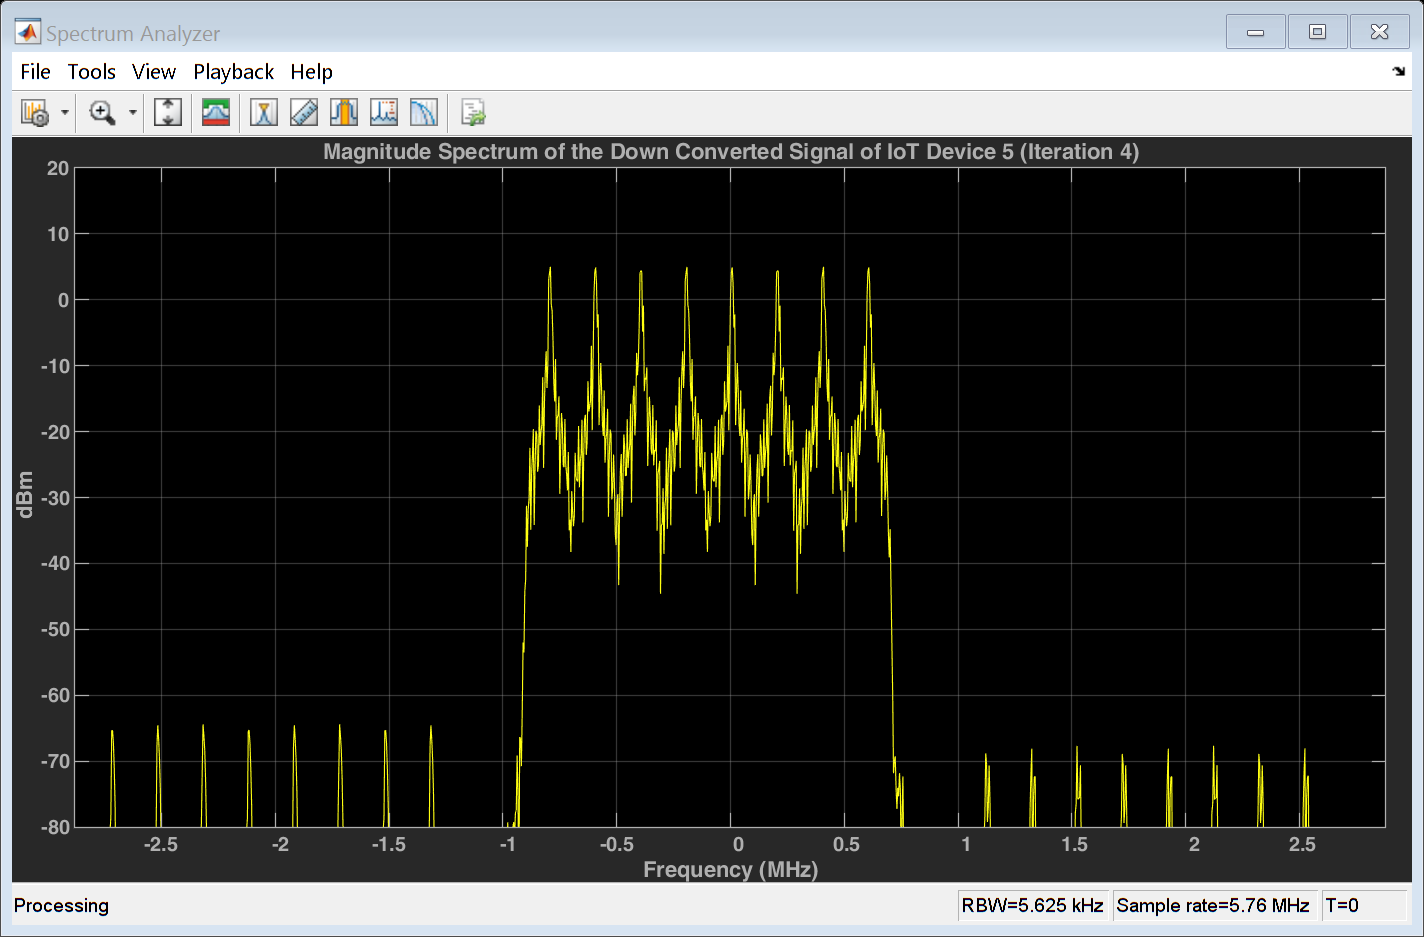

%Iteration 4
n = 0:length(sum_upconv_4)-1;
Down_Converted_4 = [];   %Vector to hole a down converted signal

%Down Conversion
for i=1:1:length(FD)
    Downconv = exp(-1i*2*pi*FD(i)*n*ts);
    downconverted = Downconv'.* sum_upconv_4 ;
    Down_Converted_4 = [Down_Converted_4 downconverted];
end

%Plot the magnitude spectrum of the Down Converted signal 
spectrumAnalyzer16 = dsp.SpectrumAnalyzer(1);
spectrumAnalyzer16.SampleRate = fs;
spectrumAnalyzer16(Down_Converted_4(:,5));
spectrumAnalyzer16.Title = "Magnitude Spectrum of the Down Converted Signal of IoT Device 5 (Iteration 4)";

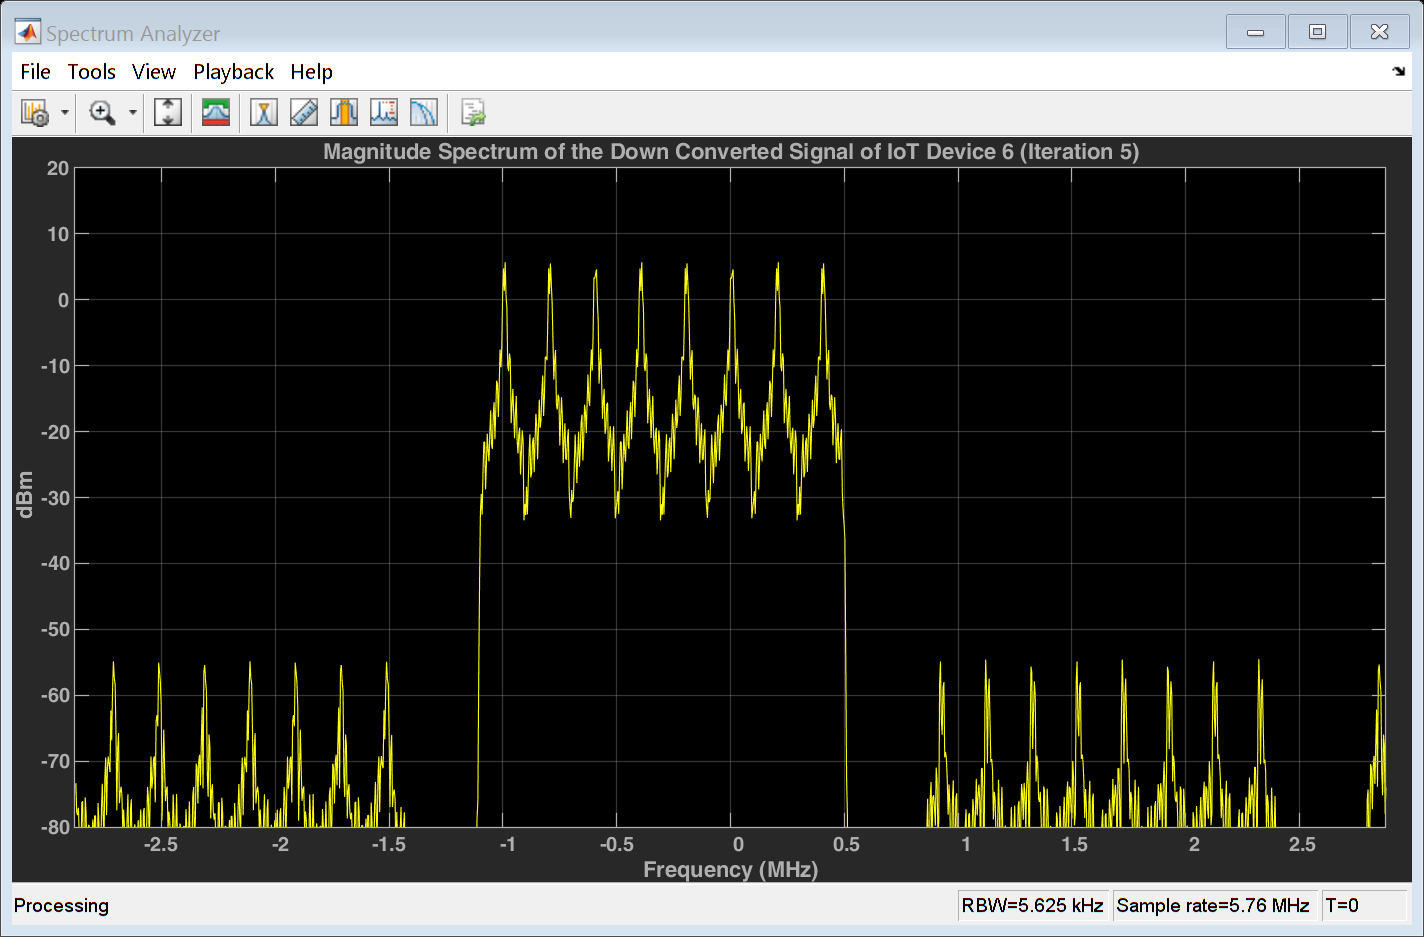

%Iteration 5
n = 0:length(sum_upconv_5)-1;
Down_Converted_5 = [];   %Vector to hole a down converted signal

%Down Conversion
for i=1:1:length(FD)
    Downconv = exp(-1i*2*pi*FD(i)*n*ts);
    downconverted = Downconv'.* sum_upconv_5 ;
    Down_Converted_5 = [Down_Converted_5 downconverted];
end

%Plot the magnitude spectrum of the Down Converted signal 
spectrumAnalyzer16 = dsp.SpectrumAnalyzer(1);
spectrumAnalyzer16.SampleRate = fs;
spectrumAnalyzer16(Down_Converted_5(:,6));
spectrumAnalyzer16.Title = "Magnitude Spectrum of the Down Converted Signal of IoT Device 6 (Iteration 5)";

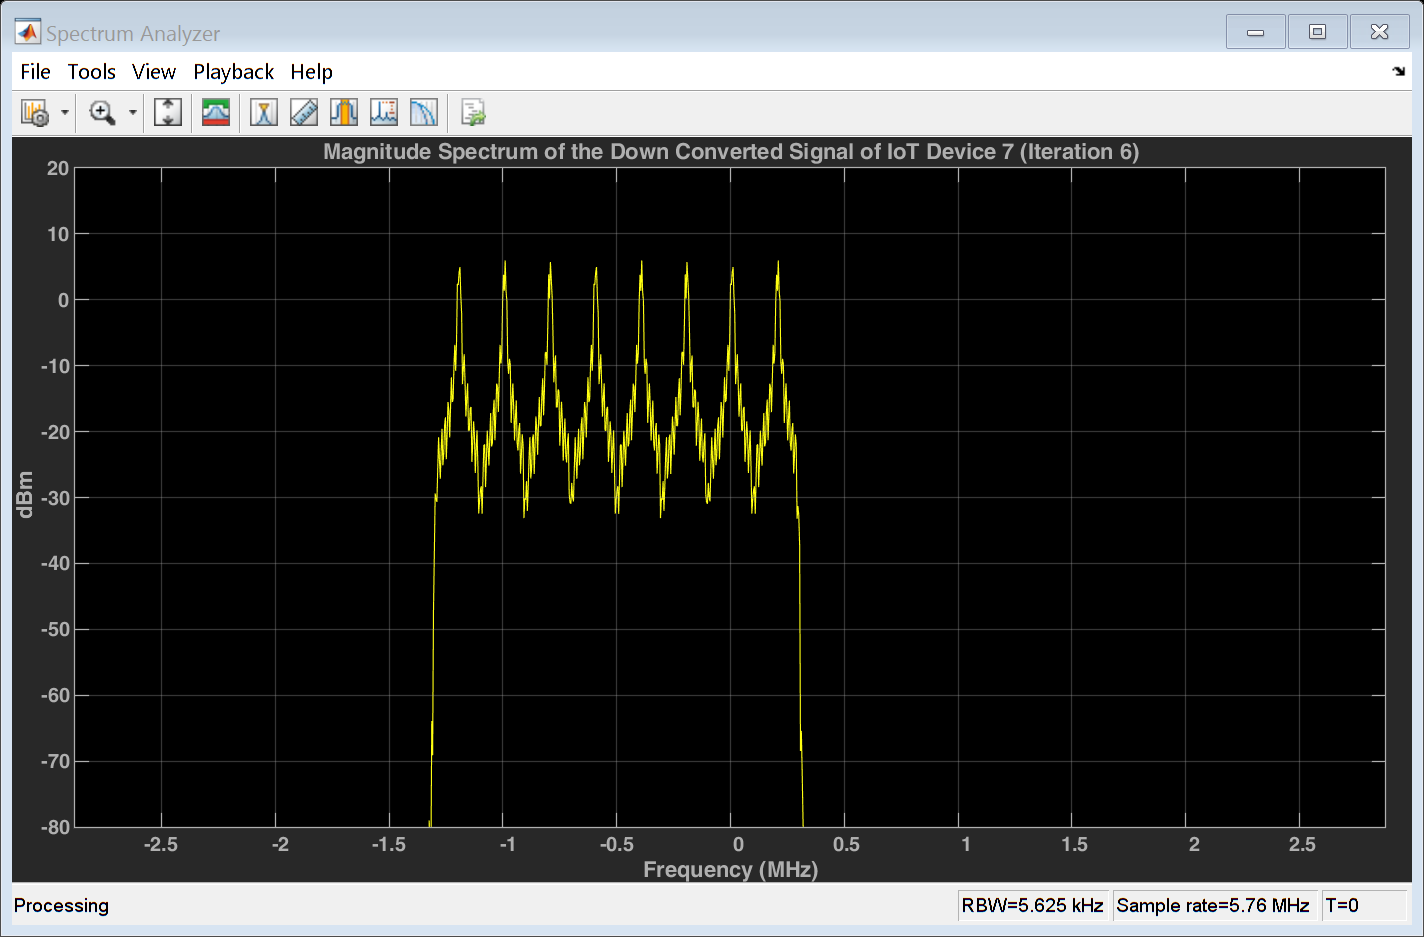

%Iteration 6
n = 0:length(sum_upconv_6)-1;
Down_Converted_6 = [];   %Vector to hole a down converted signal

%Down Conversion
for i=1:1:length(FD)
    Downconv = exp(-1i*2*pi*FD(i)*n*ts);
    downconverted = Downconv'.* sum_upconv_6 ;
    Down_Converted_6 = [Down_Converted_6 downconverted];
end

%Plot the magnitude spectrum of the Down Converted signal 
spectrumAnalyzer16 = dsp.SpectrumAnalyzer(1);
spectrumAnalyzer16.SampleRate = fs;
spectrumAnalyzer16(Down_Converted_6(:,7));
spectrumAnalyzer16.Title = "Magnitude Spectrum of the Down Converted Signal of IoT Device 7 (Iteration 6)";

## FIR Filter:

- **The Digital Down Converted Signals need to be passed through a FIR Filter to pass the desired frequencies and attenuates the stopband frequencies.**

- **Important frequencies exist in the range from -90 kHz to 90 kHz.**

- **This step will be repeated 6 times for each iteration and using the 6 designed filters. **

%Iteration 1
Rec_filtered_1 = filter(filter1, 1, Down_Converted_1(:,5))

Rec_filtered_1 =   -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0001 - 0.0000i
  -0.0001 - 0.0000i
  -0.0001 - 0.0000i
  -0.0001 - 0.0000i
  -0.0001 - 0.0000i
  -0.0001 - 0.0001i
  -0.0001 - 0.0001i
  -0.0001 - 0.0001i


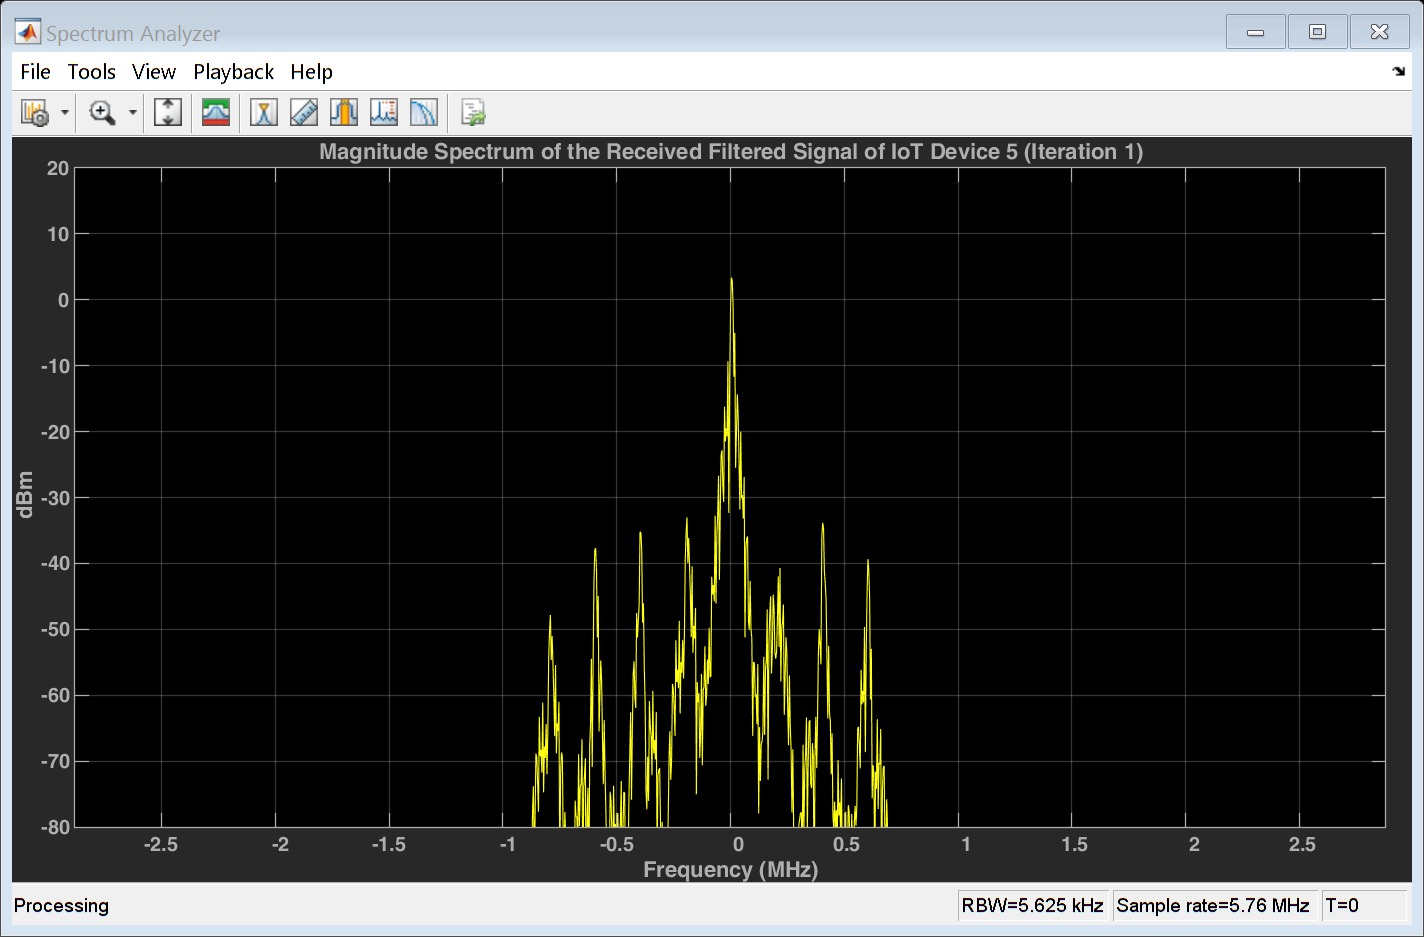


%Plot the magnitude spectrum of the Filtered Received signal 
spectrumAnalyzer17 = dsp.SpectrumAnalyzer(1);
spectrumAnalyzer17.SampleRate = fs;
spectrumAnalyzer17(Rec_filtered_1);
spectrumAnalyzer17.Title = "Magnitude Spectrum of the Received Filtered Signal of IoT Device 5 (Iteration 1)";

%Iteration 2
Rec_filtered_2 = filter(filter2, 1, Down_Converted_2(:,5))

Rec_filtered_2 =   -0.0001 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
   0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 + 0.0000i


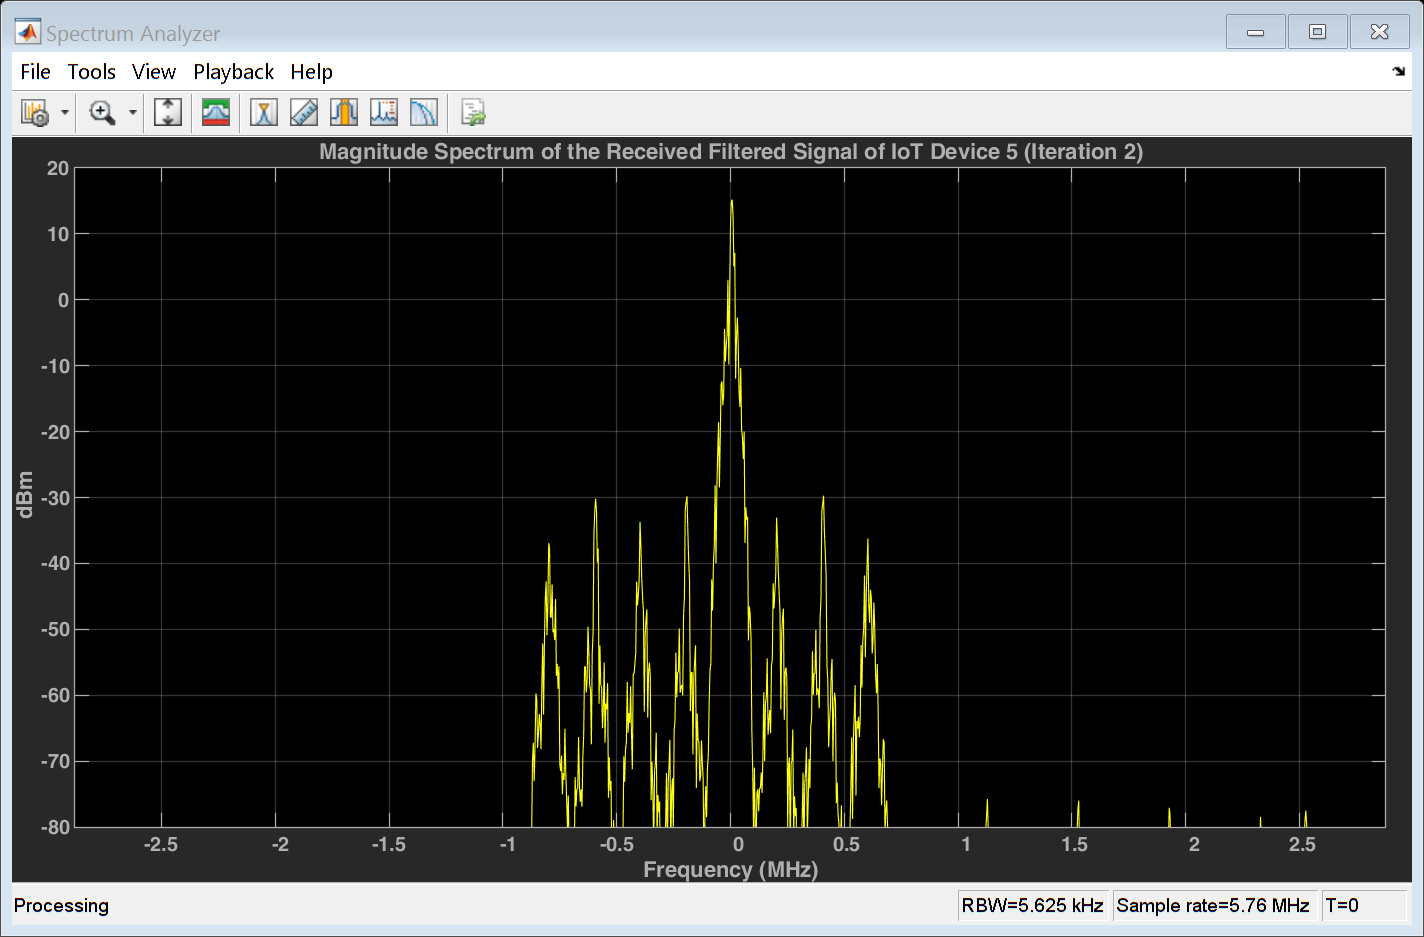


%Plot the magnitude spectrum of the Filtered Received signal 
spectrumAnalyzer18 = dsp.SpectrumAnalyzer(1);
spectrumAnalyzer18.SampleRate = fs;
spectrumAnalyzer18(Rec_filtered_2);
spectrumAnalyzer18.Title = "Magnitude Spectrum of the Received Filtered Signal of IoT Device 5 (Iteration 2)";

%Iteration 3
Rec_filtered_3 = filter(filter3, 1, Down_Converted_3(:,5))

Rec_filtered_3 =   -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
   0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 + 0.0000i


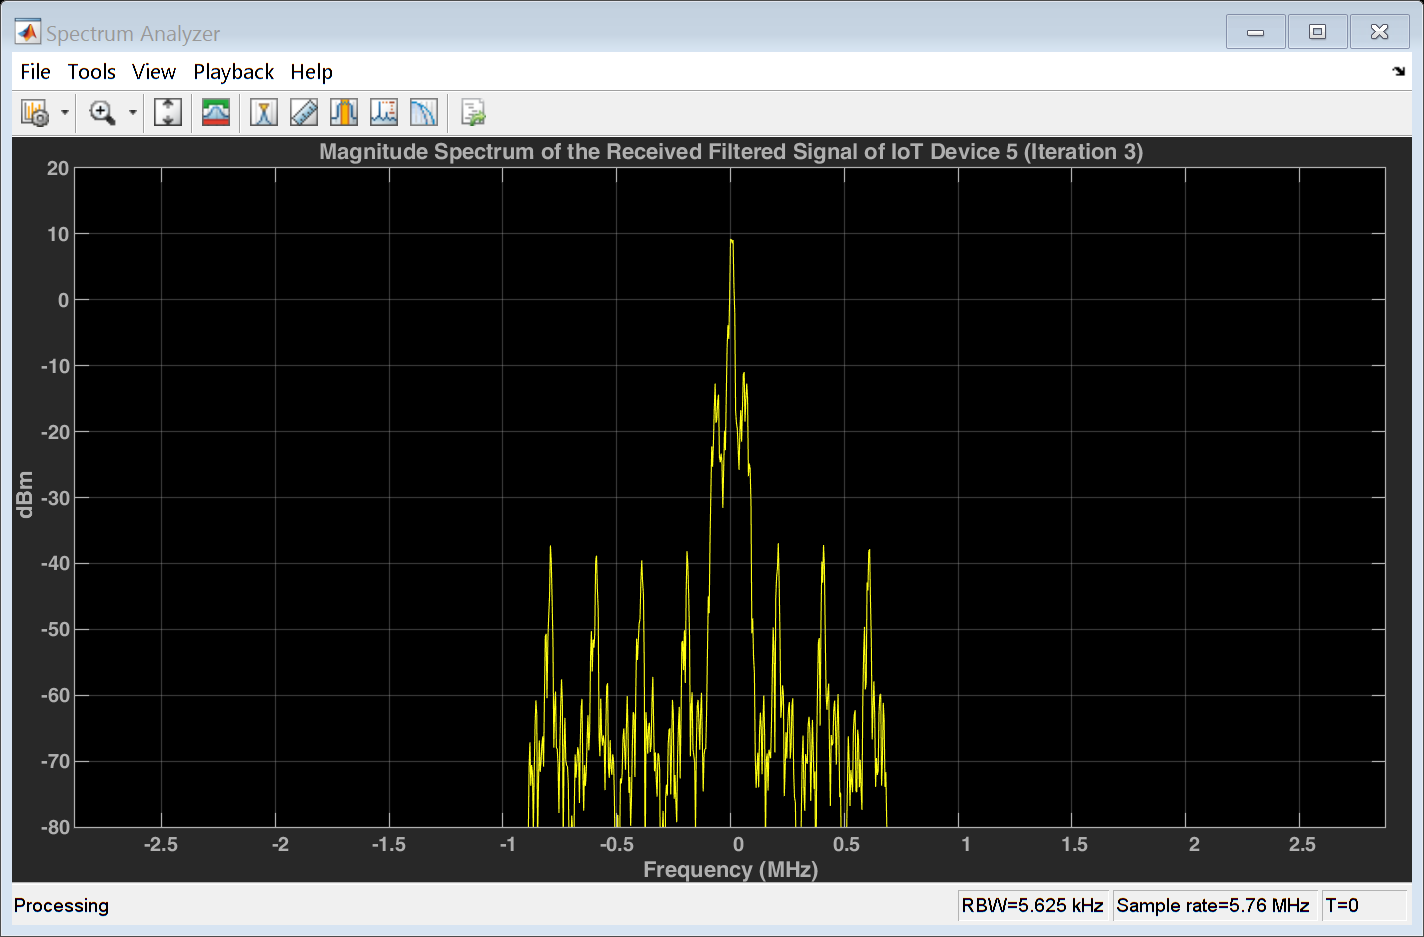


%Plot the magnitude spectrum of the Filtered Received signal 
spectrumAnalyzer19 = dsp.SpectrumAnalyzer(1);
spectrumAnalyzer19.SampleRate = fs;
spectrumAnalyzer19(Rec_filtered_3);
spectrumAnalyzer19.Title = "Magnitude Spectrum of the Received Filtered Signal of IoT Device 5 (Iteration 3)";

%Iteration 4
Rec_filtered_4 = filter(filter4, 1, Down_Converted_4(:,5))

Rec_filtered_4 =   -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i


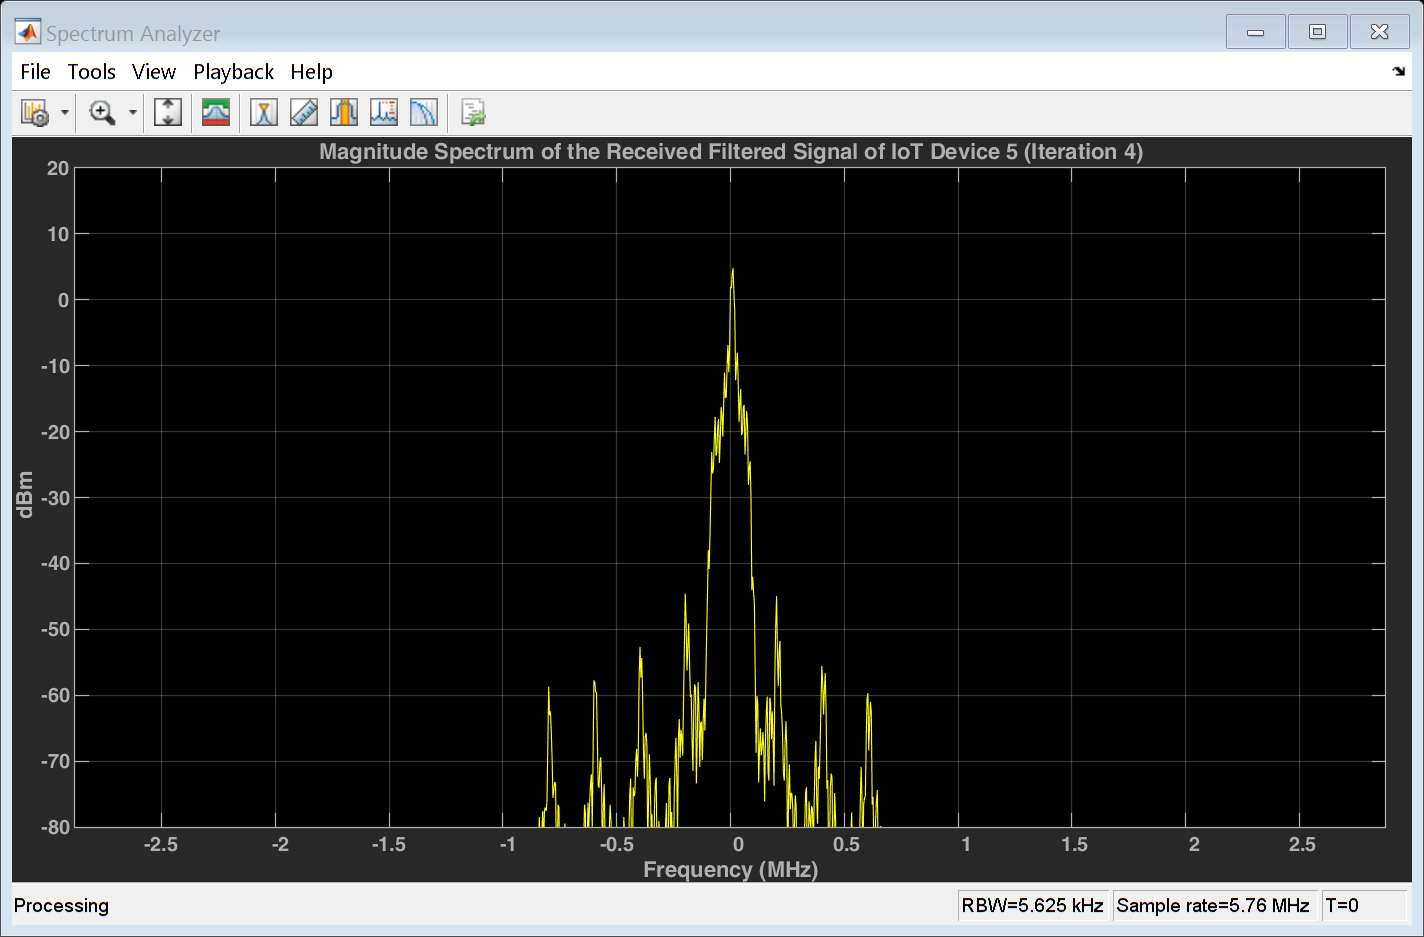


%Plot the magnitude spectrum of the Filtered Received signal 
spectrumAnalyzer19 = dsp.SpectrumAnalyzer(1);
spectrumAnalyzer19.SampleRate = fs;
spectrumAnalyzer19(Rec_filtered_4);
spectrumAnalyzer19.Title = "Magnitude Spectrum of the Received Filtered Signal of IoT Device 5 (Iteration 4)";

%Iteration 5
Rec_filtered_5 = filter(filter5, 1, Down_Converted_5(:,5))

Rec_filtered_5 =   -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i


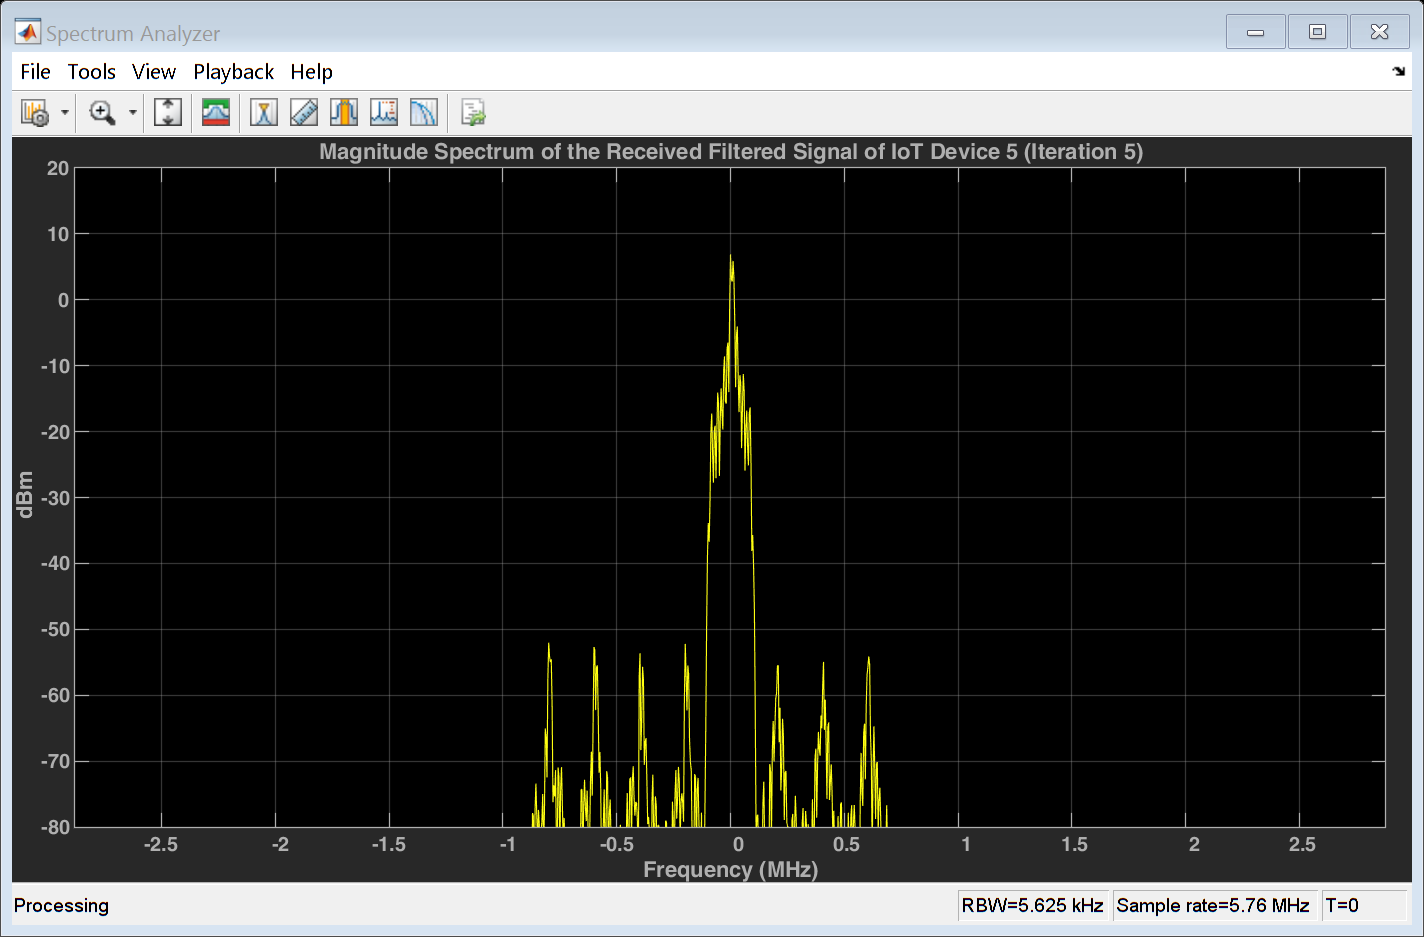


%Plot the magnitude spectrum of the Filtered Received signal 
spectrumAnalyzer20 = dsp.SpectrumAnalyzer(1);
spectrumAnalyzer20.SampleRate = fs;
spectrumAnalyzer20(Rec_filtered_5);
spectrumAnalyzer20.Title = "Magnitude Spectrum of the Received Filtered Signal of IoT Device 5 (Iteration 5)";

%Iteration 6
Rec_filtered_6 = filter(filter6, 1, Down_Converted_6(:,5))

Rec_filtered_6 =   -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i


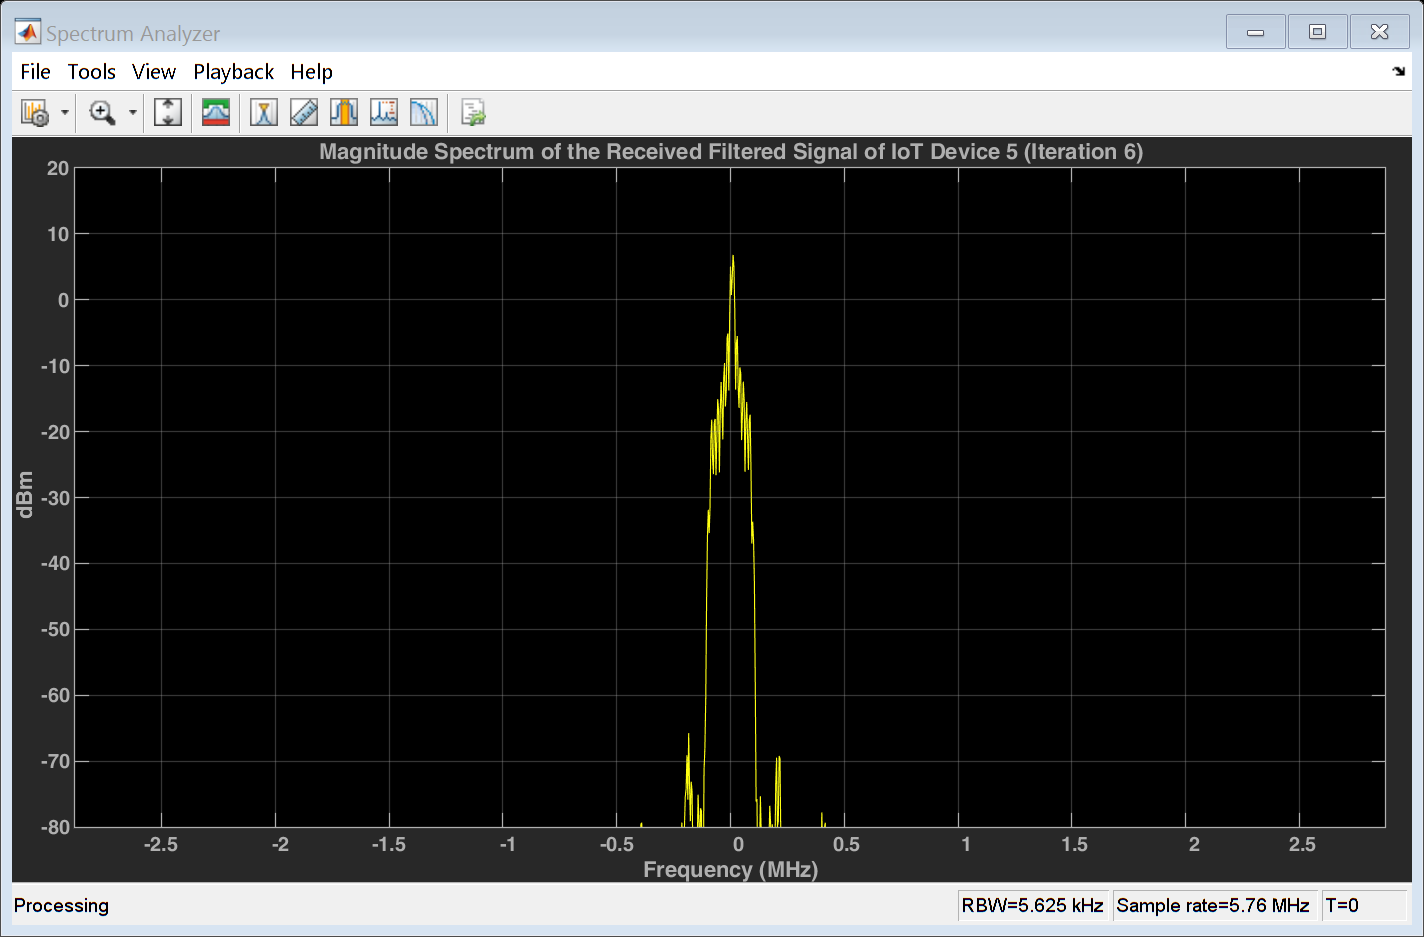


%Plot the magnitude spectrum of the Filtered Received signal 
spectrumAnalyzer21 = dsp.SpectrumAnalyzer(1);
spectrumAnalyzer21.SampleRate = fs;
spectrumAnalyzer21(Rec_filtered_6);
spectrumAnalyzer21.Title = "Magnitude Spectrum of the Received Filtered Signal of IoT Device 5 (Iteration 6)";

## Downsampling:

- **Each Constructed Signal from the 8 Signals needs to be down sampled. **

- **The current sampling rate is 5760 kHz.**

- **But, now we are having frequency components from -90 kHz to 90 kHZ.**

- **So, the new sample rate will be chosen such that:**


$$\frac{\textrm{fs}}{2}=100\;\textrm{kHz}$$


- **This step will be repeated 6 times for the 6 iterations**

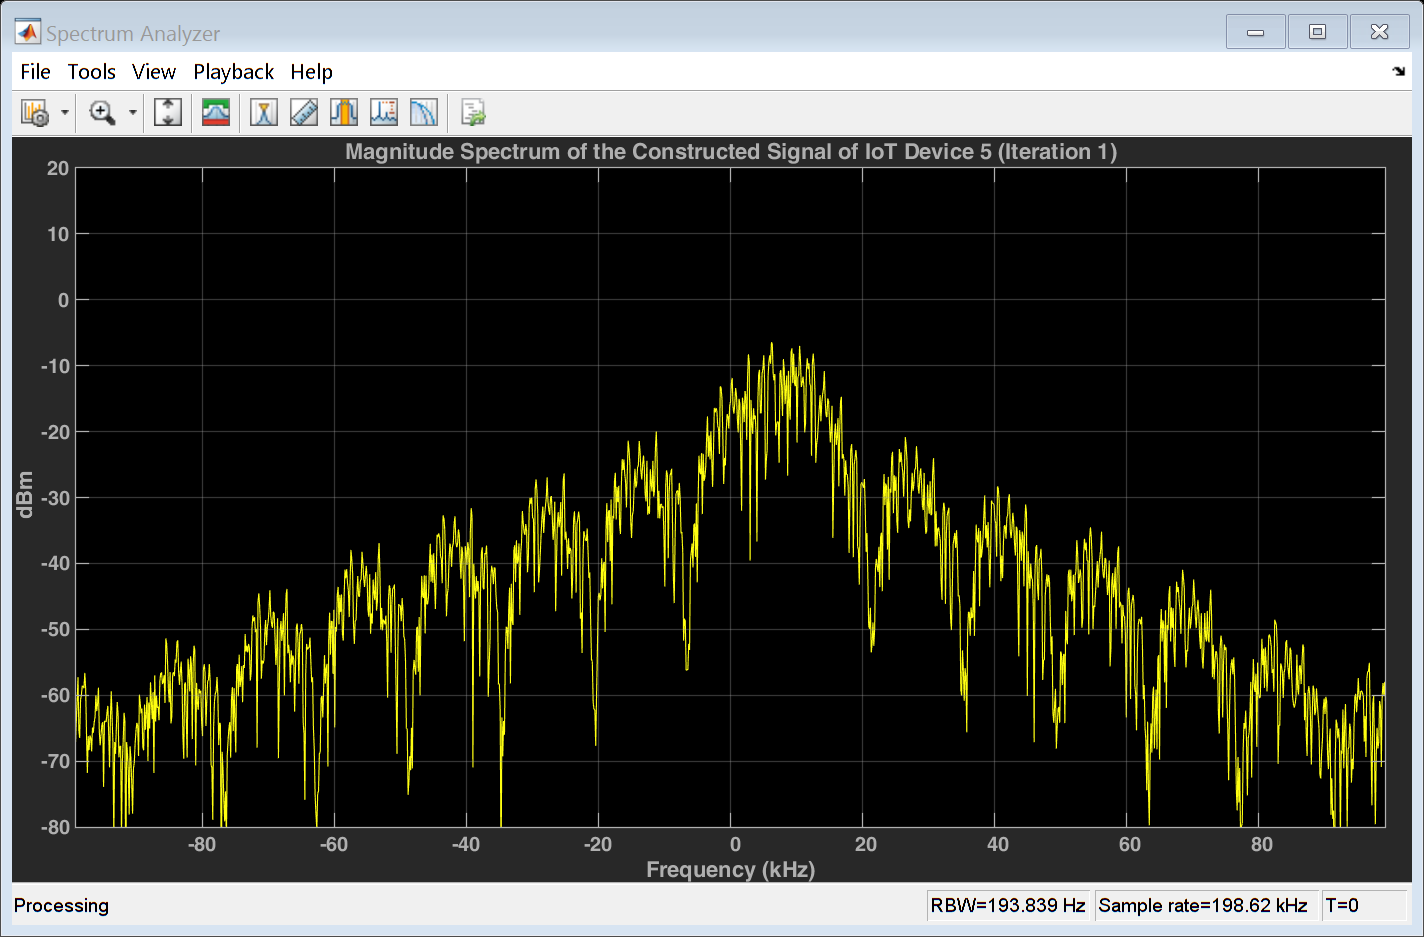

factor_down = ceil((fs/2) / 100e3); %The ratio between the new and original sample rates
fs_down = fs / factor_down;
%Iteration 1
waveform_downsampled_1 = downsample(Rec_filtered_1, factor_down);
spectrumAnalyzer22 = dsp.SpectrumAnalyzer(1);
spectrumAnalyzer22.SampleRate = fs_down;
spectrumAnalyzer22(waveform_downsampled_1);
spectrumAnalyzer22.Title = "Magnitude Spectrum of the Constructed Signal of IoT Device 5 (Iteration 1)";

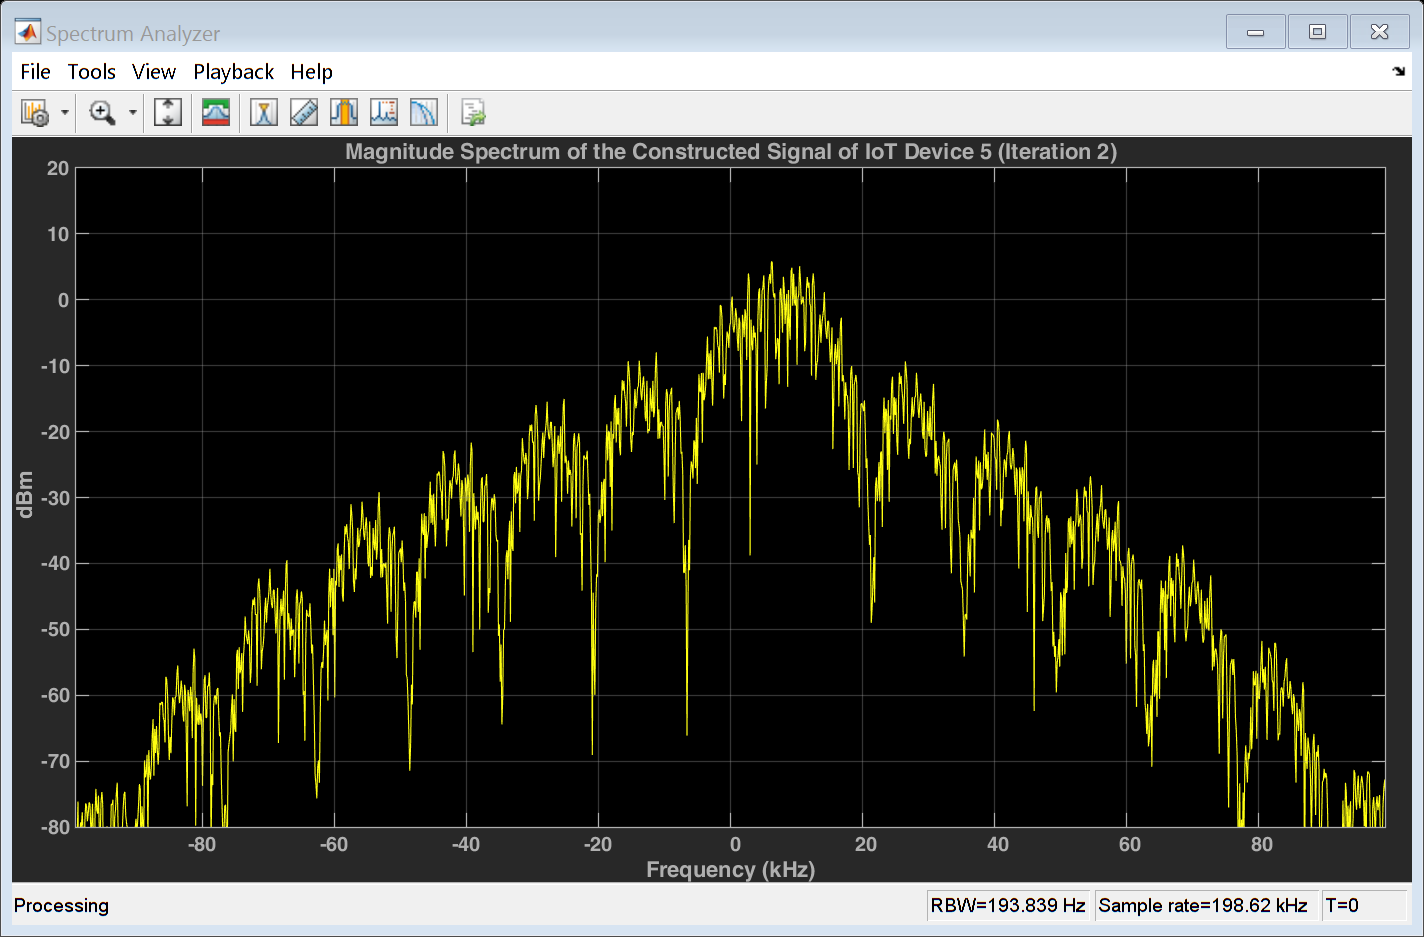

%Iteration 2
waveform_downsampled_2 = downsample(Rec_filtered_2, factor_down);
spectrumAnalyzer23 = dsp.SpectrumAnalyzer(1);
spectrumAnalyzer23.SampleRate = fs_down;
spectrumAnalyzer23(waveform_downsampled_2);
spectrumAnalyzer23.Title = "Magnitude Spectrum of the Constructed Signal of IoT Device 5 (Iteration 2)";

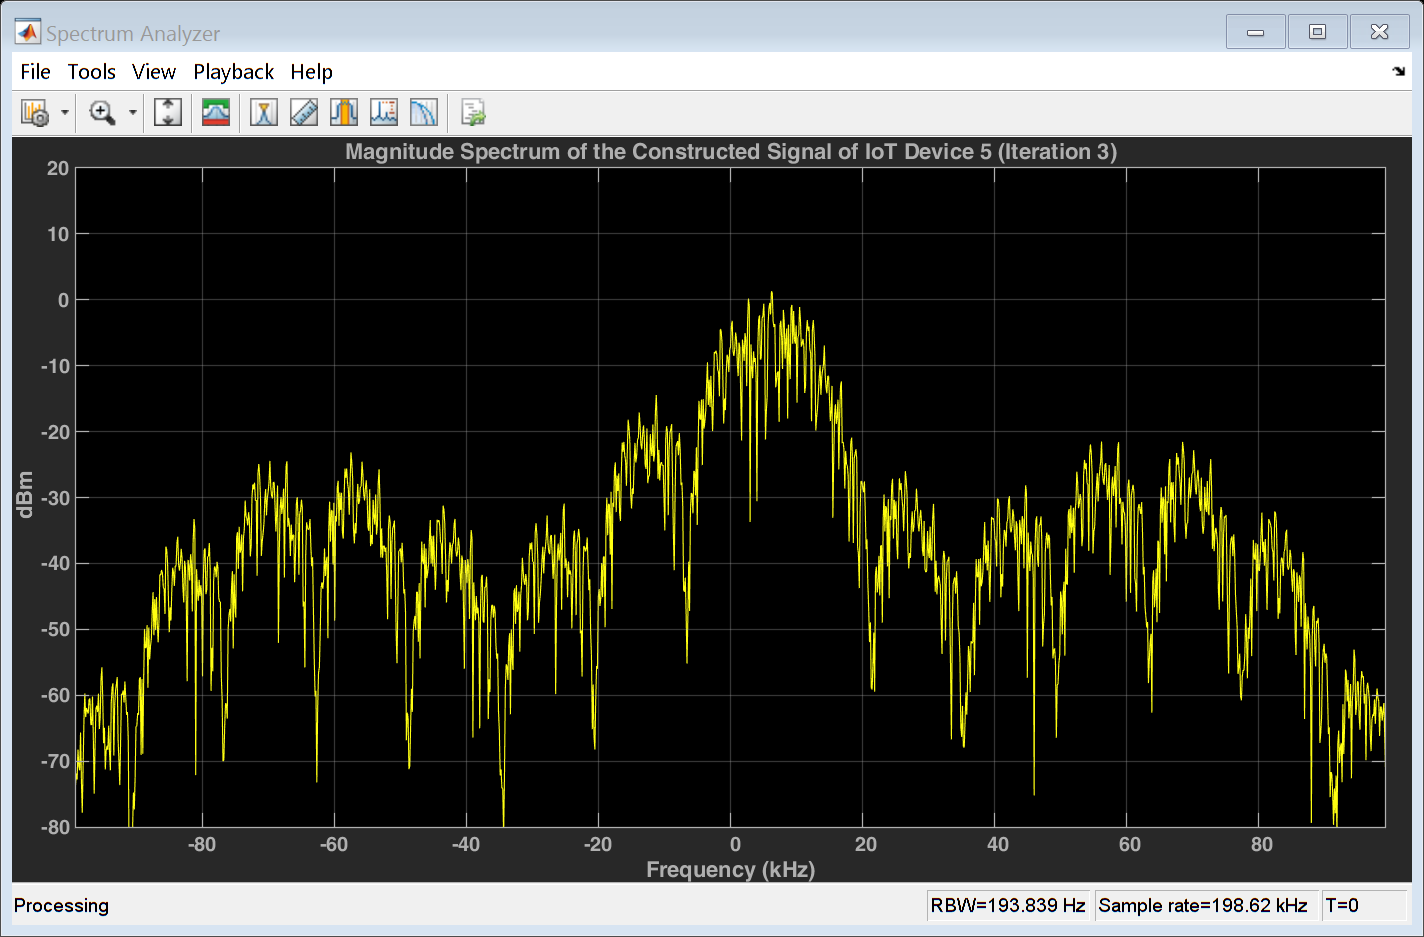

%Iteration 3
waveform_downsampled_3 = downsample(Rec_filtered_3, factor_down);
spectrumAnalyzer24 = dsp.SpectrumAnalyzer(1);
spectrumAnalyzer24.SampleRate = fs_down;
spectrumAnalyzer24(waveform_downsampled_3);
spectrumAnalyzer24.Title = "Magnitude Spectrum of the Constructed Signal of IoT Device 5 (Iteration 3)";

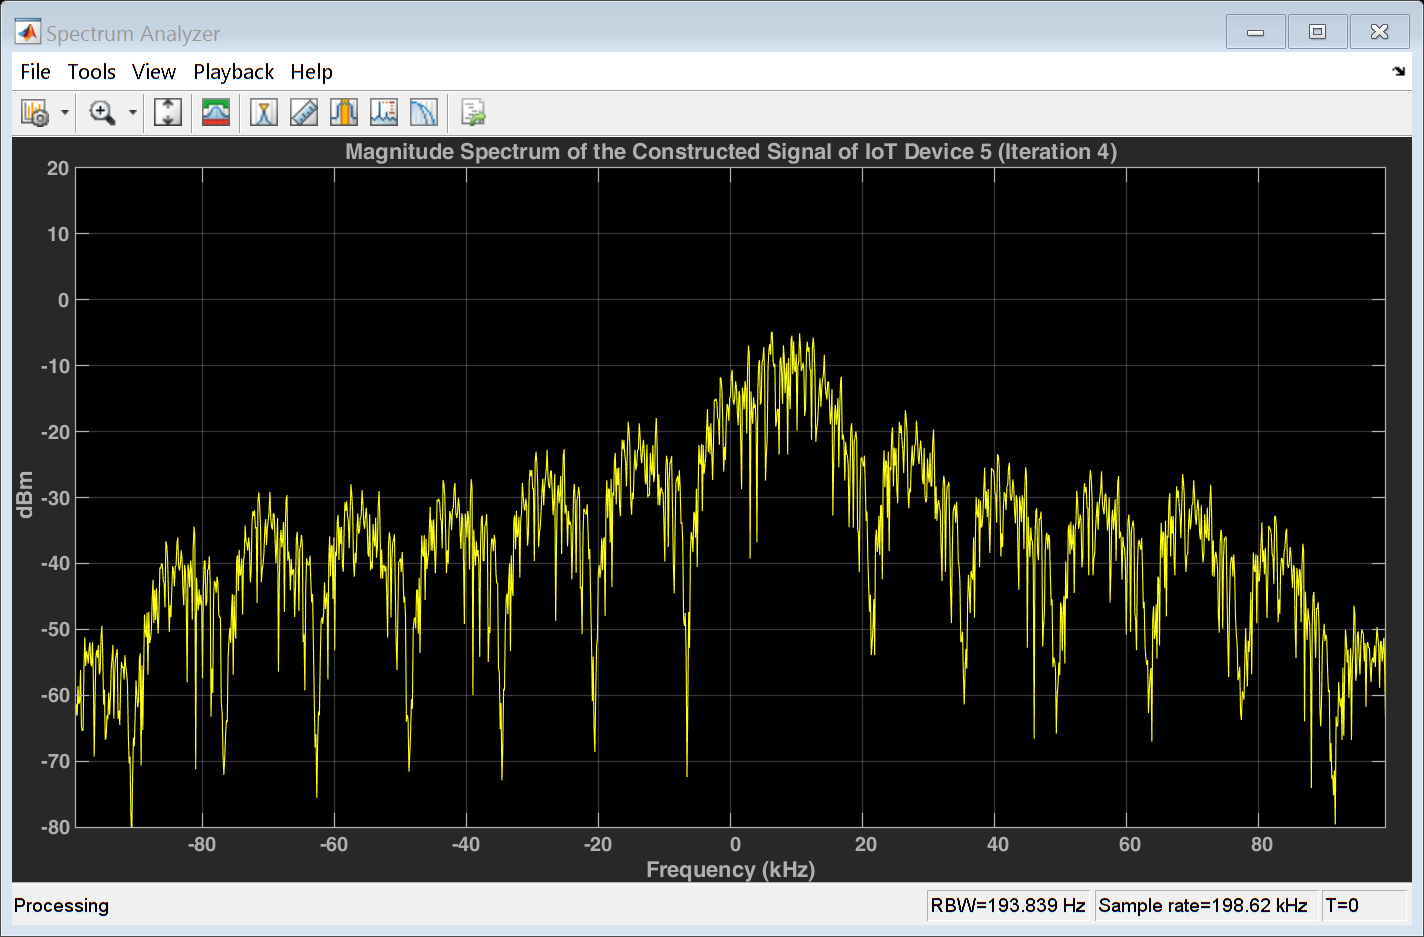

%Iteration 4
waveform_downsampled_4 = downsample(Rec_filtered_4, factor_down);
spectrumAnalyzer25 = dsp.SpectrumAnalyzer(1);
spectrumAnalyzer25.SampleRate = fs_down;
spectrumAnalyzer25(waveform_downsampled_4);
spectrumAnalyzer25.Title = "Magnitude Spectrum of the Constructed Signal of IoT Device 5 (Iteration 4)";

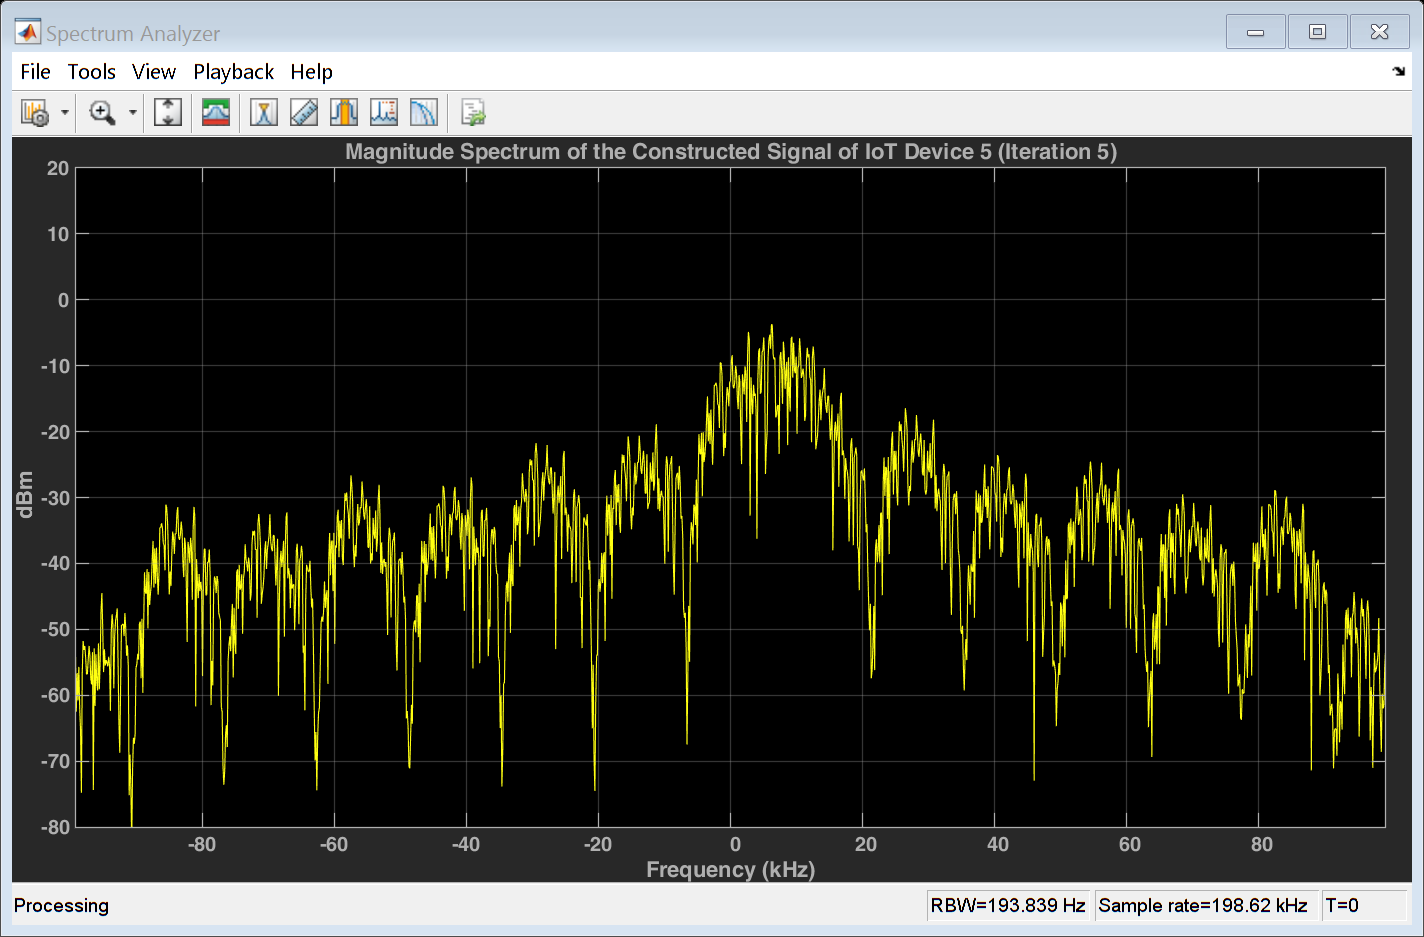

%Iteration 5
waveform_downsampled_5 = downsample(Rec_filtered_5, factor_down);
spectrumAnalyzer26 = dsp.SpectrumAnalyzer(1);
spectrumAnalyzer26.SampleRate = fs_down;
spectrumAnalyzer26(waveform_downsampled_5);
spectrumAnalyzer26.Title = "Magnitude Spectrum of the Constructed Signal of IoT Device 5 (Iteration 5)";

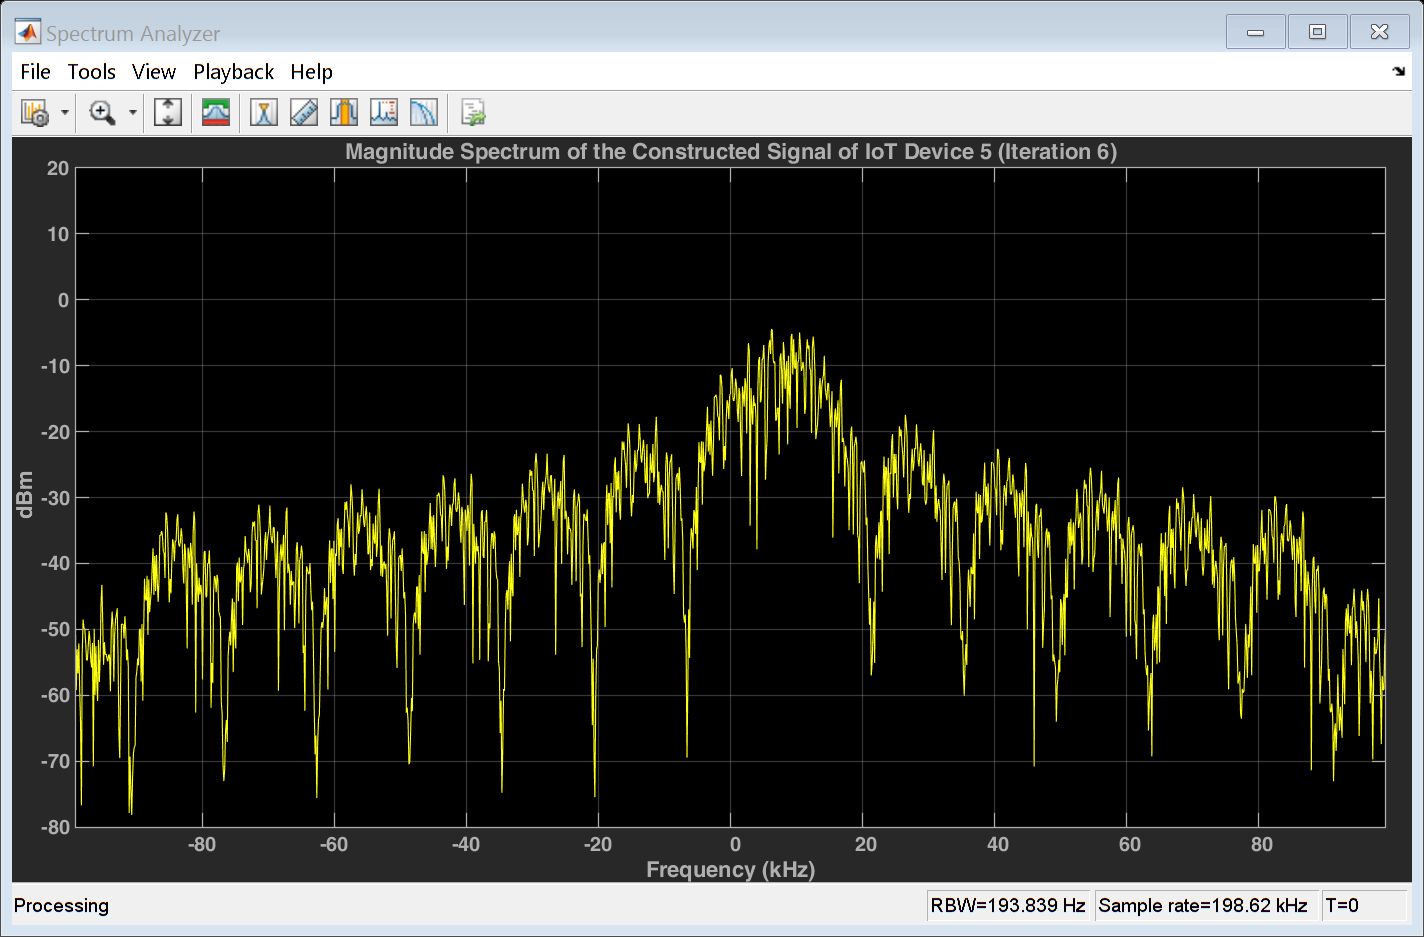

%Iteration 6
waveform_downsampled_6 = downsample(Rec_filtered_6, factor_down);
spectrumAnalyzer27 = dsp.SpectrumAnalyzer(1);
spectrumAnalyzer27.SampleRate = fs_down;
spectrumAnalyzer27(waveform_downsampled_6);
spectrumAnalyzer27.Title = "Magnitude Spectrum of the Constructed Signal of IoT Device 5 (Iteration 6)";

## **Filter Choice and Justification:**

Referring to the frequency spectrums displayed by spectrum analyzers (16), (21) & (27), the best filter that can be used to select the signal is the filter used in iteration 6 because it has effectively selected the desired signal without distortion or interference by adjacent signals as shown in (21). Moreover, it has efficiently removed the other signals allowing us to perform downsampling to pervsere the used bandwidth as shown by analyzer (27).

- **The Filter is a Least-squares filter with**

**                 1) Number of taps (order) = 512**

**                 2) Fs = 5.76 MHz**

**                 3) Fpass = 90 kHz**

**                 4) Fstop = 110 kHz**

**Discuss public health, safety, as well as social, environmental, and economic factors related to one or more NB-IoT application of your choice. Include the relevant references in your discussion**.  

NB-IoT is recognized as an internationally low power wide area network (LPWAN) based wireless communication standard developed by 3GPP (3rd Generation Partnership Project) for devices that require low bandwidth and small amounts of data. This improves battery life, penetration performance, device density, and enables low complexity and cost. NB-IoT can be used in a variety of applications. Key target applications include  smart cities, personal IoT applications, smart grids, smart metering, industrial monitoring, agriculture, water saving, alarms and event detection.

- **NB-IOT use in ****smart cities**** Application:**

There are a lot of Narrow Band IoT solutions communicating with each other to make the city easier and safer. They are being developed across the world to improve the services and facilities in the urban areas. The Smart City Initiative links all  traditional infrastructure to Information and Communication Technology (ICT) networks. ICT support improves the quality of all  basic services and public institutions. This helps in delivering high-quality services in  modern urban areas.

**Public Health:** NB-IoT plays a significant role in public health, where it contributes into the medical systems and equipment used in surgeries or even in saving the data of the patients in an efficient and suitable system. Additionally,  the sensors and devices are with high modern techniques.

**Safety****: **Given the crucial importance of security in cities, IoT innovations are increasing the security of city dwellers. New services such as remote video monitoring and automatic incident detection enable rapid response to threats. IoT-driven crowd management solutions help protect urban dwellers in crowded and uncrowded areas. Smart street lights, which help reduce crime rates and improve driving conditions, are another example of the actions city planners have taken to improve people's safety.

**Social factors: **Citizens and businesses are integrated into an intelligent and networked ecosystem. We are faced with the challenge of achieving quality of life and social development goals.

**Environmental factors:**  As the dustbin is either full or not present, it tends to spill over and pollute surroundings. In addition to at the time of collection, half full or overflow, collection becomes inefficient. However,  in the presence of NB-IoT there could be a solution that could be a sensor. Which automatically provides status of fill level thus raising alert. These sensors include temperature, GPS, Ultrasonic sensors. This could help in raising public health due to preventing the pollution and make use of wastes for recycling.

**Economic factors****: **NB-IoT,  or[LTE Cat NB1],  is in the process of connecting billions of devices more intelligently. It supports low power consumption for cost-effective, low-cost device use  and provides  wide  coverage. This low power wide area (LPWA) technology makes economies of scale a valid theory for the IoT industry. It can connect to virtually anywhere and works with  established cellular networks. This impacts smart cities, smart buildings, and consumers.

- **References:**

-  “Narrowband IOT based support functions ... - researchgate.net.” Available: https://www.researchgate.net/publication/350926631_Narrowband_IoT_Based_Support_Functions_in_Smart_Cities. 

- S. Nižetić, P. Šolić, D. López-de-Ipiña González-de-Artaza, and L. Patrono, “Internet of things (IOT): Opportunities, issues and challenges towards a smart and sustainable future,” *Journal of cleaner production*, 20-Nov-2020.  Available: [https://www.ncbi.nlm.nih.gov/pmc/articles/PMC7368922/](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC7368922/).

- Y. Cheng, X. Zhao, J. Wu, H. Liu, Y. Zhao, M. Al Shurafa, and I. Lee, “Research on the smart medical system based on Nb-IOT Technology,” *Mobile Information Systems*, 25-Jun-2021.  Available: https://www.hindawi.com/journals/misy/2021/7801365/. 

- S. K. Routray, K. P. Sharmila, E. Akanskha, A. D. Ghosh, L. Sharma and M. Pappa, "Narrowb and IoT (NBIoT) for Smart Cities," 2021 Third International Conference on Intelligent Communication Technologies and Virtual Mobile Networks (ICICV), 2021